Read data (output from python program)

% For Data: Get csv file (CograngerHR_aggregate....csv) convert to excel
% and add/drop columns; see CograngerHR_aggregate1to12.xlsx
% Data; first Granger causality test and p values, then earnings levels; N=91

hr_p_all_5s = [0.5867	0.2979	0.3437	0.9067	0.8171	0.0536	0.8081	0.0591	0.5702	0.3244	0.1239	2.4054	0.7086	0.1398	0.7782	0.0794	1
0.2391	1.3992	0.0447	4.1129	0.0001	16.219	0.0001	16.5482	0.0264	5.025	0.0128	6.3329	0.0017	9.9065	0.0006	11.7262	1
0.3078	1.0491	0.0391	4.3516	0.5681	0.3263	0.0381	4.3211	0.0349	4.5056	0.019	5.5819	0.4765	0.5075	0.8203	0.0517	1
0.7071	0.1423	0.5793	0.3101	0	34.9416	0.0002	13.8734	0.7336	0.1166	0.4413	0.5982	0.4924	0.4716	0.0163	5.7973	1
0.1242	2.4613	0.0336	4.826	0.0059	7.64	0.0152	5.9319	0.2347	1.4471	0.8318	0.0456	0.0147	5.9805	0.0026	9.1188	1
0.9491	0.0041	0.9264	0.0086	0.855	0.0334	0.3364	0.9261	0.3377	0.933	0.0177	5.925	0.0003	13.1291	0.0043	8.1973	1
0.3896	0.7499	0.1371	2.2632	0.626	0.2379	0.5239	0.4068	0.0038	8.8568	0.424	0.6452	0.4028	0.7008	0.8738	0.0253	1
0.4342	0.6164	0.5894	0.2931	0.0662	3.3949	0.2081	1.5896	0.4295	0.6272	0.1348	2.258	0.063	3.4686	0.2554	1.2961	2
0.556	0.3617	0.9914	0.0001	0.0603	3.5672	0.0004	12.8638	0	25.5536	0.6893	0.1637	0.4419	0.5922	0.0003	13.0437	2
0.1572	2.0448	0.6922	0.158	0.8001	0.0642	0.2727	1.2067	0.3332	0.9424	0.6823	0.1682	0.9701	0.0014	0.6513	0.2044	2
0.5195	0.4178	0.5381	0.3817	0.9664	0.0018	0.0599	3.5604	0.086	2.9975	0.0197	5.5855	0.8934	0.018	0.6479	0.2087	2
0.7921	0.07	0.7864	0.074	0.5058	0.4436	0.6801	0.1703	0.1577	2.0153	0.0252	5.1073	0.9489	0.0041	0.2657	1.241	2
0.3589	0.8493	0.2614	1.2753	0.6385	0.221	0.7146	0.1339	0.1568	2.0237	0.3932	0.7331	0.1888	1.7308	0.1006	2.7041	2
0.0574	3.7002	0.1281	2.3568	0.6172	0.2502	0.1263	2.3471	0.305	1.0596	0.4934	0.4714	0.7941	0.0682	0.0454	4.0217	2
0.2928	1.1134	0.7081	0.1407	0.03	4.7305	0.4208	0.649	0.3203	0.9925	0.0778	3.1412	0.9847	0.0004	0.9542	0.0033	3
0.6826	0.1685	0.3047	1.0679	0.4483	0.5757	0.0404	4.222	0.8829	0.0219	0.1117	2.5887	0.091	2.8618	0.0493	3.8759	3
0.5048	0.4483	0.1526	2.0795	0.4861	0.4859	0.2039	1.6183	0.5935	0.2867	0.1635	1.9688	0.0339	4.5124	0.2631	1.2539	3
0.9307	0.0076	0.5929	0.287	0.7142	0.1342	0.388	0.7464	0.3206	0.9893	0.4871	0.484	0.0695	3.3033	0.0328	4.5716	3
0.7628	0.0912	0.2151	1.5417	0.8263	0.0482	0.4888	0.4797	0.6634	0.1896	0.877	0.024	0.6622	0.1909	0.1804	1.7973	3
0.8152	0.0549	0.9775	0.0008	0.0525	3.774	0.2151	1.5404	0.1332	2.2766	0.4306	0.6241	0.1001	2.7085	0.9344	0.0068	3
0.8374	0.0425	0.2834	1.1716	0.3444	0.8954	0.0548	3.7019	0.6913	0.159	0.2148	1.5671	0.567	0.3279	0.7471	0.104	3
0.9641	0.002	0.4492	0.5812	0.6557	0.199	0.1913	1.7133	0.4654	0.5366	0.0569	3.7005	0.5697	0.3233	0.9136	0.0118	3
0.6123	0.2603	0.9612	0.0024	0.595	0.283	0.0178	5.6633	0.3627	0.8416	0.2386	1.418	0.4565	0.5551	0.7977	0.0658	4
0.3663	0.835	0.1638	2.0122	0.0278	4.8905	0.5284	0.3983	0.5578	0.3488	0.4569	0.5634	0.0416	4.1677	0.3395	0.9137	4
0.9806	0.0006	0.2012	1.747	0.3319	0.9439	0.0468	3.9763	0.4493	0.5809	0.7671	0.0886	0.689	0.1603	0.0528	3.7624	4
0.1931	1.7349	0.9913	0.0001	0.6248	0.2396	0.1336	2.2595	0.7004	0.1494	0.3079	1.0565	0.3975	0.7167	0.3525	0.8656	4
0.2865	1.1597	0.1538	2.0953	0.0237	5.1566	0.1806	1.7988	0.001	11.613	0.5936	0.2868	0.6962	0.1526	0.014	6.074	4
0.2872	1.14	0.0002	14.0586	0.0454	4.0227	0	23.4809	0.4882	0.4819	0.2022	1.6347	0.806	0.0604	0.0022	9.4088	4
0.2958	1.1069	0.578	0.3119	0.3308	0.9477	0.2299	1.4455	0.9878	0.0002	0.5541	0.3524	0.7651	0.0893	0.6257	0.2381	4
0.2291	1.4603	0.0026	9.4114	0.0125	6.281	0.0003	13.4045	0.9121	0.0122	0.8862	0.0205	0.0163	5.7935	0.5828	0.3019	4
0.5964	0.2865	0.4641	0.5501	0.5382	0.3797	0.867	0.0281	0.4792	0.5108	0.7899	0.072	0.2065	1.599	0.8332	0.0444	5
0.5822	0.3059	0.0082	7.4673	0.1615	1.9691	0.7018	0.1469	0.0025	9.4663	0.5049	0.4468	0.5065	0.4418	0.5631	0.3348	5
0.1818	1.8538	0.2382	1.4386	0	29.7484	0.4633	0.5392	0.0122	6.7308	0.3626	0.8433	0.967	0.0017	0.4585	0.5502	5
0.2798	1.2342	0.9474	0.0045	0.9074	0.0136	0.314	1.0181	0.6858	0.1662	0.007	8.121	0.1859	1.7538	0.3592	0.842	5
0	20.0313	0.0353	4.6172	0	28.3421	0.6002	0.2751	0.0001	17.5317	0.0269	5.0164	0.3254	0.9689	0.901	0.0155	5
0.3205	1.0053	0.9594	0.0026	0.1609	1.9744	0.7632	0.0909	0.304	1.064	0.8729	0.0257	0.0534	3.7472	0.4878	0.482	5
0.2406	1.4296	0.1424	2.2618	0.3348	0.933	0.4857	0.4872	0.3558	0.8728	0.5818	0.3083	0.5339	0.3874	0.6976	0.1511	5
0.4262	0.6395	0.0001	17.3734	0.2158	1.5375	0.5187	0.4174	0.0013	10.6152	0.392	0.7356	0.1245	2.3664	0.2772	1.1831	5
0.7135	0.1355	0.7525	0.0999	0.1706	1.8858	0.0002	14.5361	0.2808	1.1685	0.904	0.0146	0.363	0.8297	0.102	2.6881	6
0.4069	0.6937	0.0363	4.5028	0.5702	0.323	0.0301	4.7421	0.0774	3.1751	0.0013	10.8035	0.8754	0.0246	0.3721	0.7988	6
0.5981	0.2802	0.4891	0.4831	0.252	1.3175	0.7947	0.0679	0.5841	0.3015	0.9559	0.0031	0.6952	0.1538	0.6655	0.1873	6
0.7011	0.1481	0.8246	0.0494	0.4346	0.612	0.5665	0.3292	0.4	0.7107	0.0084	7.0529	0.333	0.9397	0.2189	1.5169	6
0.4242	0.6447	0.8846	0.0212	0.4433	0.5893	0.5069	0.4415	0.4196	0.6564	0.3233	0.984	0.1019	2.6895	0.1336	2.2603	6
0.0426	4.2095	0.7956	0.0674	0.4266	0.6335	0.5806	0.3059	0.6104	0.2602	0.8919	0.0185	0.1112	2.5501	0.3652	0.822	6
0.375	0.7953	0.0511	3.9154	0.0265	4.9723	0.0092	6.8649	0.4598	0.5484	0.667	0.1856	0.3712	0.8018	0.4415	0.5936	6
0.018	6.0402	0.0644	3.599	0.6894	0.1604	0.0478	3.9867	0.6684	0.1843	0.0069	7.521	0.0575	3.635	0.3717	0.8005	7
0.3392	0.9261	0.4079	0.6934	0.37	0.8077	0.0295	4.816	0.959	0.0027	0.2679	1.2331	0.3698	0.8067	0.1049	2.646	7
0.0599	3.627	0.1261	2.3819	0.5228	0.4097	0.1367	2.23	0.017	5.8034	0.4645	0.5374	0.4942	0.4685	0.671	0.1808	7
0.6604	0.1949	0.7919	0.0702	0.6493	0.2074	0.0536	3.7704	0.0968	2.7991	0.6067	0.2664	0.5751	0.3149	0.3645	0.8249	7
0.7794	0.0811	0.641	0.2259	0.3752	0.791	0.0379	4.3819	0.2171	1.5519	0.0214	5.5489	0.8935	0.0179	0.5813	0.3049	7
0.6669	0.187	0.4351	0.6172	0.1194	2.4495	0.0436	4.1331	0.0479	3.9571	0.0045	8.2536	0.95	0.0039	0.3159	1.0092	7
0.9661	0.0018	0.4731	0.5204	0.146	2.1306	0.1021	2.6991	0.251	1.3303	0.9939	0.0001	0.2009	1.6434	0.0282	4.8661	7
0.236	1.4665	0.0102	7.5994	0.882	0.0221	0.012	6.4289	0.7116	0.1379	0.1418	2.2129	0.2094	1.5823	0.4476	0.5781	7
0.3649	0.8369	0.5075	0.4459	0.8299	0.0462	0.099	2.7321	0.5076	0.4425	0.0624	3.5577	0.3576	0.8476	0.1712	1.8764	8
0.7247	0.1247	0.4699	0.5258	0.267	1.2347	0.1685	1.9014	0.8138	0.0557	0.2301	1.4551	0.2388	1.3903	0.9716	0.0013	8
0.944	0.005	0.1823	1.7875	0.1047	2.641	0.2852	1.1444	0.3943	0.7273	0.3705	0.8036	0.0025	9.2186	0.6942	0.1547	8
0.1842	1.7902	0.7929	0.0693	0.801	0.0636	0.7659	0.0887	0.3651	0.827	0.0022	9.801	0.1506	2.071	0.566	0.3297	8
0.0027	9.2631	0.9176	0.0107	0.4804	0.4986	0.1714	1.8758	0.5914	0.2889	0.0433	4.1237	0.6623	0.1908	0.6408	0.2179	8
0.7253	0.1239	0.8605	0.031	0.1986	1.6569	0.8963	0.017	0.9079	0.0134	0.8522	0.0348	0.0082	7.0387	0.0954	2.7878	8
0.003	8.9547	0.0134	6.1836	0.3279	0.9585	0.1672	1.9125	0.9936	0.0001	0.0166	5.7834	0.0685	3.3291	0.7763	0.0808	8
0.7922	0.0699	0.473	0.5206	0.7201	0.1285	0.34	0.9121	0.0419	4.2492	0.9256	0.0088	0.5585	0.3426	0.4479	0.5766	8
0.6991	0.1501	0.0616	3.5592	0.809	0.0585	0.9479	0.0043	0.8973	0.0167	0.0047	8.1233	0.4779	0.5045	0.7119	0.1366	9
0.4918	0.4799	0.0107	7.0539	0.6336	0.2277	0.003	9.0055	0.6041	0.2702	0.2179	1.5337	0.0282	4.8457	0.0009	11.1539	9
0.1264	2.3806	0.5653	0.3331	0.9009	0.0155	0.6678	0.1844	0.115	2.5115	0.2331	1.4328	0.5304	0.3942	0.0495	3.8765	9
0.0404	4.3911	0.9909	0.0001	0.1649	1.9365	0.347	0.8866	0.6963	0.1532	0.6175	0.2509	0.6614	0.192	0.3743	0.7909	9
0.0105	6.7334	0.9422	0.0053	0.0001	15.5835	0	20.8321	0.9668	0.0017	0.0003	13.4004	0.7934	0.0687	0.0662	3.3888	9
0.3965	0.724	0.0023	9.7242	0.0252	5.0483	0.1959	1.6787	0.6816	0.1687	0.5628	0.3357	0.9088	0.0131	0.5007	0.4541	9
0.0311	4.8519	0.1748	1.8814	0.0729	3.2367	0.0365	4.4069	0.7065	0.1424	0.1842	1.7823	0.8859	0.0206	0.2933	1.1067	9
0.0821	3.0958	0.8969	0.0169	0.4583	0.5512	0.4416	0.5934	0.0002	14.8702	0.0684	3.3669	0.2765	1.1867	0.0046	8.1064	9
0.8323	0.0452	0.8325	0.0451	0.4168	0.6612	0.587	0.2957	0.6393	0.2209	0.3471	0.8916	0.5269	0.401	0.4581	0.5515	10
0.1113	2.6919	0.5541	0.358	0.4169	0.6613	0.093	2.8419	0.4628	0.5475	0.0942	2.9112	0.0596	3.5675	0.4314	0.6202	10
0.8239	0.0501	0.6808	0.1715	0.7848	0.0747	0.3894	0.7432	0.1813	1.8292	0.703	0.1468	0.3028	1.0643	0.9179	0.0106	10
0.2791	1.1832	0.7832	0.0761	0.7882	0.0723	0.8254	0.0487	0.1756	1.8499	0.9427	0.0052	0.656	0.1986	0.9477	0.0043	10
0.9666	0.0018	0.6876	0.1628	0.0712	3.2768	0.4128	0.6724	0.9055	0.0141	0.0172	5.851	0.3192	0.9947	0.7346	0.1151	10
0.131	2.3298	0.7412	0.1099	0.122	2.4061	0.5678	0.3271	0.0903	2.9213	0.2263	1.481	0.7968	0.0664	0.8421	0.0397	10
0.4783	0.5072	0.8931	0.0182	0.7816	0.077	0.7285	0.1207	0.0127	6.494	0.1301	2.3387	0.0356	4.4448	0.7358	0.114	10
0.8872	0.0203	0.7693	0.0867	0.3398	0.9144	0.4816	0.4964	0.3313	0.9565	0.1551	2.0647	0.4639	0.5374	0.0983	2.744	10
0.0946	2.9032	0.7741	0.0832	0.3583	0.8465	0.027	4.9432	0.8003	0.0643	0.2487	1.3428	0.165	1.9369	0.2709	1.2165	11
0.4443	0.5946	0.0889	3.0105	0.7658	0.0889	0.808	0.0592	0.813	0.0564	0.3595	0.8518	0.3786	0.7777	0.0776	3.1359	11
0.608	0.2648	0.278	1.1894	0.0641	3.4502	0.0307	4.7104	0.5269	0.4023	0.8258	0.0486	0.6113	0.2588	0.0017	10.0349	11
0.344	0.9133	0.8999	0.016	0.5347	0.3864	0.1119	2.5425	0.6751	0.1764	0.9615	0.0023	0.1119	2.542	0.0824	3.0367	11
0.6664	0.1869	0.4284	0.6323	0.9191	0.0103	0.0125	6.3165	0.3366	0.9283	0.673	0.1786	0.7359	0.114	0.7585	0.0947	11
0.0464	4.0381	0.3201	0.9957	0.0351	4.4736	0.0143	6.0576	0.4773	0.5061	0.7973	0.0661	0.1072	2.6107	0.0554	3.6999	11
0.2117	1.586	0.479	0.5059	0.7756	0.0814	0.9767	0.0009	0.6882	0.162	0.0897	2.9366	0.8379	0.0419	0.4292	0.6262	12
0.6109	0.2641	0.8005	0.0649	0.0523	3.8155	0.1929	1.7072	0.4377	0.613	0.1001	2.8159	0.2122	1.5615	0.3789	0.7761	12
0	24.6577	0.5679	0.3301	0.5843	0.3	0.3718	0.8003	0.83	0.0465	0.9314	0.0075	0.9619	0.0023	0.3441	0.8974	12
0.0798	3.3228	0.9899	0.0002	0.2798	1.1741	0.4392	0.6006	0.1122	2.6514	0.0348	4.8115	0.5568	0.3459	0.5166	0.4214	12
0.0309	4.8042	0.0941	2.8609	0.7416	0.1089	0.1185	2.4519	0.4186	0.6577	0.0574	3.6647	0.1648	1.9371	0.1584	1.9967	12
0.8886	0.0197	0.5276	0.4018	0.0952	2.8053	0.8437	0.0389	0.6931	0.1563	0.3121	1.028	0.2005	1.6445	0.5706	0.3221	12
0.256	1.2986	0.2322	1.4369	0.0896	2.8993	0.4437	0.5882	0.6248	0.2397	0.0728	3.2428	0.7669	0.088	0.0505	3.8466	12
0.0031	9.5025	0.3652	0.8325	0.6615	0.1922	0.4392	0.6005	0.164	1.9849	0.8069	0.0603	0.0253	5.0412	0.8821	0.022	12
0.1809	1.813	0.0651	3.4703	0.6221	0.2434	0.914	0.0117	0.2968	1.0945	0.2331	1.431	0.4376	0.6037	0.7873	0.0729	21
0.4575	0.5577	0.0497	3.9769	0.3197	0.9932	0.2233	1.4889	0.6492	0.2084	0.8822	0.0221	0.0584	3.6006	0.0274	4.8985	21
0.9009	0.0156	0.0675	3.4224	0.952	0.0036	0.0298	4.7627	0.0467	4.0205	0.618	0.2496	0.4576	0.5527	0.8496	0.036	21
0.3501	0.8838	0.3252	0.9804	0.5036	0.4486	0.397	0.7198	0.6562	0.1993	0.6107	0.2607	0.5724	0.3192	0.0728	3.2348	21
0.4272	0.6371	0.1918	1.7338	0.6279	0.2353	0.9997	0	0.7545	0.0984	0.5243	0.4086	0.8775	0.0238	0.3106	1.0305	21
0.2776	1.202	0.0034	9.3799	0.0384	4.3214	0.3056	1.0529	0.2271	1.4722	0.2261	1.479	0.2923	1.1116	0.9531	0.0035	21
0.9169	0.0109	0.2347	1.4317	0.0611	3.5308	0.0827	3.0294	0.6551	0.2008	0.4081	0.6906	0.5849	0.2988	0.4659	0.5327	21
0.9857	0.0003	0.404	0.7057	0.486	0.4867	0.9172	0.0108	0.1375	2.2378	0.0877	2.9671	0.7669	0.088	0.0386	4.3034	21
0.6746	0.178	0.9525	0.0036	0.3603	0.8388	0.924	0.0091	0.9337	0.007	0.6603	0.1947	0.137	2.2164	0.5705	0.3222	22
0.1949	1.7054	0.5575	0.3466	0.7998	0.0644	0.8055	0.0607	0.9804	0.0006	0.2189	1.5266	0.8327	0.0447	0.3606	0.8371	22
0.7489	0.1038	0.0011	12.392	0.0007	11.5737	0.0023	9.4582	0.3067	1.0641	0.002	10.5369	0.6188	0.2479	0.7944	0.068	22
0.9377	0.0062	0.2307	1.4663	0.5483	0.3609	0.2881	1.1312	0.4669	0.5339	0.0775	3.189	0.0106	6.5739	0.0094	6.7844	22
0.0039	9.1737	0.6879	0.1633	0.0266	4.9546	0.0039	8.4504	0.0177	6.018	0.4496	0.5808	0.2986	1.0822	0.7776	0.0798	22
0.2927	1.1301	0.2582	1.307	0.1803	1.8011	0.0592	3.5774	0.5368	0.3846	0.1349	2.2771	0.469	0.5249	0.9961	0	22
0.6463	0.2115	0.2279	1.4667	0.9212	0.0098	0.6456	0.2117	0.1675	1.9241	0.8058	0.0607	0.1355	2.2335	0.603	0.2707	22
0.3825	0.7799	0.7545	0.0991	0.3254	0.9697	0.9396	0.0058	0.5003	0.4618	0.1054	2.7326	0.061	3.5222	0.1818	1.7865	22
0.8137	0.0562	0.0781	3.2606	0.0505	3.8494	0.6114	0.2586	0.6464	0.2116	0.1259	2.3765	0.7888	0.0718	0.6636	0.1894	23
0.4699	0.5267	0.1869	1.7694	0.9307	0.0076	0.6986	0.1502	0.9008	0.0156	0.6179	0.25	0.4568	0.5545	0.4564	0.5553	23
0.5483	0.3637	0.3349	0.9423	0.3504	0.8743	0.0665	3.3872	0.454	0.5646	0.3136	1.0248	0.6627	0.1904	0.0299	4.7394	23
0.1595	2.0244	0.112	2.5943	0.0331	4.5744	0.585	0.2987	0.3693	0.8119	0.7506	0.1015	0.0071	7.2874	0.077	3.1383	23
0.0374	4.3987	0.6369	0.2236	0.0604	3.5433	0.0026	9.1847	0.2069	1.6005	0.2757	1.1928	0.0007	11.7429	0.1363	2.2254	23
0.2357	1.4736	0.2524	1.3701	0.042	4.1674	0.0895	2.9015	0.3244	0.9933	0.1599	2.0441	0.7195	0.1291	0.391	0.7368	23
0.3725	0.8006	0.2529	1.3187	0.9201	0.0101	0.7303	0.119	0.1727	1.8762	0.2684	1.2336	0.1176	2.4559	0.0828	3.0177	23
0.4656	0.5353	0.0814	3.0818	0.8097	0.058	0.577	0.3116	0.7373	0.1128	0.0285	4.8717	0.399	0.7124	0.1761	1.8346	23
0.3177	1.0117	0.3603	0.8471	0.4899	0.4778	0.0387	4.3064	0.1053	2.6484	0.3083	1.0434	0.159	1.9882	0.8216	0.0509	24
0.9938	0.0001	0.6965	0.1585	0.2281	1.4573	0.0093	6.8304	0.092	3.0801	0.8451	0.039	0.572	0.3197	0.2216	1.4969	24
0.8393	0.0419	0.0058	8.936	0.116	2.4828	0.0216	5.3215	0.0616	3.6493	0.5899	0.2942	0.1868	1.7462	0.4192	0.6534	24
0.1821	1.8242	0.7849	0.0752	0.3457	0.8911	0.5388	0.3783	0.9451	0.0048	0.1442	2.1608	0.2186	1.5167	0.0017	9.928	24
0.5576	0.3467	0.013	6.4601	0.3293	0.9538	0.0481	3.9266	0.212	1.5694	0.6385	0.2214	0.6162	0.2515	0.0458	4.0053	24
0.7914	0.0702	0.916	0.0112	0.7974	0.066	0.521	0.4124	0.7388	0.1115	0.8832	0.0216	0.1914	1.7104	0.2204	1.5042	24
0.7407	0.1108	0.1364	2.294	0.6721	0.1794	0.1612	1.9694	0.1556	2.0357	0.9663	0.0018	0.4896	0.478	0.5501	0.3576	24
0.1517	2.1166	0.2994	1.0985	0.1296	2.3054	0.001	10.9739	0.4514	0.5706	0.0118	6.5325	0.6123	0.257	0.9694	0.0015	24];

hr_p_all_20s = [0.6126	0.2584	0.9222	0.0096	0.1553	2.025	0.1596	1.9836	0.4408	0.5987	0.0414	4.2643	0.5764	0.3123	0.8601	0.0311	1
0.0934	2.8584	0.0155	6.0274	0.0004	12.7059	0.0003	13.4389	0.7842	0.0752	0.2826	1.1627	0.0859	2.957	0.0023	9.3212	1
0.1089	2.6103	0.0336	4.6256	0.7154	0.1331	0.91	0.0128	0.0677	3.3737	0.0144	6.0863	0.2723	1.207	0.9638	0.0021	1
0.6281	0.2367	0.475	0.5158	0.0035	8.6084	0.0019	9.7416	0.4732	0.5189	0.365	0.8291	0.9449	0.0048	0.9705	0.0014	1
0.9002	0.0159	0.0024	10.4476	0.0025	9.2512	0.0011	10.858	0.9476	0.0044	0.9766	0.0009	0.1273	2.3307	0.0043	8.2158	1
0.8826	0.022	0.7765	0.0814	0.8794	0.0231	0.5755	0.314	0.3073	1.0591	0.0531	3.8847	0.0009	11.1203	0.3055	1.0513	1
0.2022	1.6604	0.0442	4.2118	0.1776	1.8235	0.0131	6.2046	0.0012	11.3043	0.0243	5.2646	0.6633	0.1897	0.9654	0.0019	1
0.6527	0.2036	0.5497	0.3601	0.1878	1.7407	0.4082	0.6855	0.0512	3.8573	0.4497	0.5741	0.3871	0.7491	0.3027	1.0639	2
0.2059	1.7384	0.2617	1.3537	0.6941	0.1551	0.0002	14.2423	0.5695	0.3327	0.3738	0.8214	0.1448	2.1321	0.1641	1.9412	2
0.2354	1.4333	0.1488	2.1331	0.1821	1.7869	0.7172	0.1313	0.0102	6.7618	0.5332	0.3901	0.2824	1.1575	0.9777	0.0008	2
0.2081	1.6052	0.4836	0.4943	0.4749	0.5115	0.1961	1.6768	0.8483	0.0368	0.5854	0.2992	0.8705	0.0266	0.7849	0.0746	2
0.5746	0.3178	0.1081	2.6453	0	23.7013	0.6134	0.2556	0.2435	1.3707	0.0949	2.8232	0.9256	0.0087	0.8416	0.04	2
0.9158	0.0112	0.3748	0.7948	0.2327	1.4287	0.1638	1.947	0.5796	0.3082	0.7117	0.1371	0.8364	0.0427	0.0035	8.6075	2
0.0054	8.1336	0.0174	5.8655	0.801	0.0636	0.0539	3.7394	0.061	3.5663	0.8057	0.0607	0.3447	0.8945	0.1792	1.8086	2
0.8384	0.0417	0.6058	0.2673	0.5101	0.4343	0.189	1.7294	0.6376	0.2226	0.0215	5.3698	0.8021	0.0628	0.2891	1.1253	3
0.9313	0.0075	0.7494	0.1028	0.9954	0	0.6769	0.1738	0.4743	0.5172	0.6111	0.2607	0.3179	0.9988	0.2346	1.4145	3
0.0826	3.0779	0.405	0.6996	0.3368	0.9241	0.0577	3.619	0.0818	3.0877	0.7078	0.1413	0.3725	0.7962	0.4907	0.4754	3
0.8994	0.016	0.9793	0.0007	0.7885	0.0721	0.778	0.0796	0.1197	2.4344	0.6324	0.2292	0.0614	3.5086	0.0005	12.3433	3
0.6926	0.1565	0.4852	0.488	0.9671	0.0017	0.4299	0.6237	0.7208	0.1278	0.0824	3.0265	0.1881	1.7349	0.7886	0.0719	3
0.5769	0.3133	0.3194	1.0015	0.8382	0.0417	0.0796	3.0848	0.3784	0.78	0.386	0.7557	0.3616	0.833	0.4511	0.5683	3
0.2569	1.3102	0.0838	3.0911	0.7644	0.0899	0.8079	0.0592	0.1706	1.9168	0.257	1.3063	0.0167	5.7436	0.0619	3.4933	3
0.0412	4.3761	0.1656	1.9758	0.5422	0.3722	0.9309	0.0075	0.991	0.0001	0.2072	1.6092	0.547	0.363	0.4894	0.4782	3
0.2935	1.1292	0.3685	0.8249	0.8659	0.0286	0.0003	13.5953	0.1345	2.3059	0.7113	0.1383	0.4212	0.6478	0.5726	0.3187	4
0.6844	0.1678	0.0726	3.4101	0.3318	0.9449	0.0608	3.5429	0.2533	1.3417	0.1137	2.609	0.4358	0.6081	0.3084	1.0392	4
0.9181	0.0108	0.7763	0.0829	0.7615	0.0922	0.1401	2.1853	0.891	0.019	0.5411	0.3783	0.5835	0.3009	0.7174	0.1311	4
0.4136	0.6799	0.3301	0.9674	0.7227	0.1261	0.1025	2.6782	0.8952	0.0175	0.1332	2.317	0.6848	0.1649	0.4557	0.557	4
0.1349	2.3067	0.1886	1.7744	0.0433	4.107	0.1286	2.319	0.0199	5.6241	0.9043	0.0145	0.3252	0.9691	0.3232	0.9772	4
0.8398	0.041	0.087	2.9634	0.2181	1.5204	0.0054	7.7979	0.7359	0.114	0.7122	0.1364	0.5895	0.2914	0.0356	4.4315	4
0.3911	0.7434	0.5136	0.4304	0.2353	1.4124	0.6087	0.2625	0.8971	0.0168	0.66	0.1947	0.0357	4.4299	0.9405	0.0056	4
0.6679	0.1849	0.0195	5.5985	0.0062	7.5473	0.0001	15.2751	0.3001	1.0783	0.5923	0.2875	0.0025	9.2107	0.2686	1.2257	4
0.4973	0.4722	0.1109	2.6979	0.4135	0.6706	0.6202	0.246	0.28	1.2013	0.8855	0.021	0.4279	0.6293	0.6357	0.2246	5
0.7044	0.1453	0.09	2.9657	0.8642	0.0293	0.6927	0.1565	0.0893	2.9259	0.359	0.8469	0.688	0.1615	0.1009	2.6996	5
0.175	1.9146	0.2057	1.6612	0.625	0.2394	0.0303	4.7344	0.0251	5.3092	0.0188	5.8643	0.3821	0.765	0.6005	0.2745	5
0.1293	2.5027	0.9729	0.0012	0.3847	0.7583	0.4032	0.7012	0.4531	0.5747	0.0549	3.9246	0.6505	0.2055	0.2454	1.3518	5
0	25.2509	0.0963	2.8456	0	52.2848	0.826	0.0484	0.0679	3.3936	0.0002	14.9419	0.0041	8.2963	0.0739	3.2069	5
0.5817	0.3073	0.5222	0.4149	0.8404	0.0406	0.4023	0.7033	0.1625	1.9703	0.5415	0.3745	0.1226	2.3908	0.0035	8.6013	5
0.2305	1.494	0.2495	1.3758	0.846	0.0378	0.6934	0.1557	0.2642	1.2826	0.1189	2.539	0.1527	2.0501	0.9326	0.0072	5
0.4679	0.5319	0.4744	0.5164	0.4883	0.4812	0.4298	0.6249	0.3405	0.9124	0.0895	2.9094	0.0215	5.3145	0.7081	0.1403	5
0.4363	0.6106	0.1469	2.1352	0.2635	1.2546	0.0231	5.2118	0.782	0.0768	0.4806	0.4992	0.2773	1.1842	0.0869	2.947	6
0.6668	0.1865	0.0126	6.4614	0.0056	7.79	0.0012	10.7088	0.9638	0.0021	0.0293	4.8668	0.7651	0.0894	0.1308	2.2937	6
0.0952	2.8534	0.5648	0.3343	0.3488	0.8806	0.9192	0.0103	0.2925	1.1187	0.4193	0.6572	0.5126	0.4296	0.0579	3.6197	6
0.0867	2.9866	0.7962	0.067	0.1825	1.7845	0.337	0.9244	0.8273	0.0477	0.0751	3.1947	0.3185	0.9981	0.603	0.271	6
0.6293	0.2346	0.9609	0.0024	0.6482	0.2086	0.6108	0.2595	0.4077	0.6906	0.4898	0.4802	0.2393	1.3892	0.05	3.869	6
0.0482	3.993	0.1942	1.7066	0.7403	0.1101	0.5375	0.3809	0.704	0.1446	0.5553	0.3488	0.1682	1.9069	0.4295	0.6257	6
0.6501	0.2073	0.4909	0.4787	0.0021	9.6661	0.0001	16.4802	0.7028	0.146	0.9285	0.0081	0.0188	5.568	0.0022	9.5545	6
0.5191	0.4227	0.6072	0.2683	0.833	0.0447	0.3152	1.0161	0.3416	0.911	0.0365	4.4612	0.0174	5.7194	0.2167	1.5325	7
0.8494	0.0363	0.0004	13.869	0.0252	5.0939	0.0027	9.249	0.3742	0.7925	0.7861	0.0738	0.5855	0.298	0.1177	2.4623	7
0.3834	0.7671	0.3087	1.0479	0.5311	0.3936	0.2803	1.171	0.115	2.5076	0.3573	0.8518	0.952	0.0036	0.9362	0.0064	7
0.1788	1.8503	0.5696	0.327	0.5504	0.3578	0.3216	0.9872	0.356	0.8584	0.1754	1.8574	0.5988	0.2774	0.5477	0.3623	7
0.5795	0.3218	0.2805	1.2601	0.9113	0.0125	0.1888	1.7422	0.3802	0.7804	0.2206	1.5294	0.5019	0.4519	0.1663	1.9253	7
0.1264	2.4024	0.0579	3.7395	0.1558	2.0332	0.025	5.1151	0.7057	0.143	0.0087	7.0132	0.9829	0.0005	0.355	0.8583	7
0.7819	0.0772	0.0524	3.8985	0.4853	0.4889	0.0329	4.6192	0.3707	0.8073	0.7446	0.1066	0.2948	1.1013	0.8834	0.0216	7
0.0254	5.6261	0.6175	0.2555	0.3647	0.8257	0.7964	0.0667	0.5933	0.2882	0.9369	0.0063	0.4174	0.6593	0.5169	0.4211	7
0.1309	2.362	0.0013	11.7368	0.4837	0.4912	0.0361	4.4179	0.7015	0.1478	0.8102	0.058	0.9618	0.0023	0.5277	0.3992	8
0.6604	0.194	0.1697	1.9104	0.8331	0.0444	0.0698	3.3017	0.9991	0	0.2677	1.2399	0.9013	0.0154	0.0578	3.6123	8
0.4885	0.481	0.1708	1.886	0.7941	0.0682	0.1617	1.9636	0.1441	2.1413	0.789	0.0717	0.4358	0.6081	0.8252	0.0488	8
0.955	0.0032	0.7203	0.129	0.084	2.998	0.7802	0.0779	0.8417	0.0401	0.1201	2.4545	0.5415	0.3732	0.4179	0.657	8
0.1521	2.0668	0.8068	0.0599	0.6633	0.1897	0.4416	0.5931	0.1031	2.676	0.6781	0.1727	0.7712	0.0846	0.6667	0.1856	8
0.5851	0.2991	0.2522	1.3197	0.8212	0.0511	0.0363	4.4055	0.0222	5.2904	0.0408	4.2254	0.8421	0.0397	0.6094	0.2613	8
0.1163	2.48	0.0311	4.6913	0.2011	1.6376	0.1056	2.6268	0.0323	4.611	0.0019	9.793	0.0032	8.7236	0.6906	0.1586	8
0.0342	4.6665	0.783	0.0764	0.7084	0.1401	0.436	0.6078	0.6796	0.1716	0.4975	0.4636	0.9448	0.0048	0.5099	0.4347	8
0.1777	1.8387	0.6491	0.2081	0.8219	0.0507	0.6693	0.1827	0.1982	1.6646	0.0614	3.5303	0.589	0.2922	0.9182	0.0105	9
0.1184	2.5328	0.0394	4.496	0.2805	1.1695	0.0003	13.1619	0.2215	1.5097	0.0221	5.37	0.5652	0.3313	0.4779	0.5044	9
0.2261	1.4872	0.9614	0.0024	0.7992	0.0648	0.5375	0.3809	0.3254	0.9731	0.6537	0.2021	0.7641	0.0901	0.0554	3.6867	9
0.16	2.0255	0.5855	0.3008	0.9466	0.0045	0.4539	0.5622	0.6283	0.2358	0.4872	0.4862	0.3536	0.8623	0.0283	4.8359	9
0.9313	0.0075	0.0595	3.6141	0.0005	12.3413	0.0001	16.3992	0.2677	1.2319	0.032	4.6332	0.8572	0.0324	0.364	0.8256	9
0.8116	0.0571	0.086	2.9966	0.0095	6.791	0.0975	2.7597	0.641	0.2179	0.4126	0.6735	0.4938	0.469	0.1713	1.8767	9
0.8742	0.0253	0.0187	5.8181	0.1721	1.8727	0.0493	3.894	0.0653	3.4567	0.7333	0.1166	0.5659	0.3301	0.8503	0.0357	9
0.807	0.0601	0.1665	1.9486	0.3159	1.0087	0.0892	2.9038	0.0279	4.9287	0.3267	0.9679	0.7906	0.0706	0.6702	0.1816	9
0.4156	0.6708	0.5923	0.2896	0.6083	0.2633	0.1128	2.5293	0.3924	0.7375	0.0239	5.2533	0.9806	0.0006	0.9877	0.0002	10
0.6169	0.2559	0.2367	1.4622	0.8521	0.0348	0.0624	3.5015	0.546	0.3698	0.4166	0.6714	0.0555	3.687	0.117	2.4672	10
0.519	0.423	0.5703	0.3273	0.3931	0.7316	0.8008	0.0638	0.4992	0.4624	0.4201	0.6594	0.4432	0.589	0.4913	0.4745	10
0.4128	0.6759	0.975	0.001	0.7716	0.0844	0.7533	0.0989	0.6086	0.2632	0.8757	0.0246	0.7162	0.1324	0.582	0.3035	10
0.0965	2.8279	0.3586	0.8526	0.8894	0.0194	0.8803	0.0227	0.7798	0.0785	0.8528	0.0346	0.182	1.7871	0.5377	0.3805	10
0.6145	0.2558	0.6927	0.1573	0.1601	1.9842	0.5998	0.276	0.6503	0.2067	0.1019	2.7229	0.6843	0.1655	0.0579	3.6169	10
0.296	1.106	0.3449	0.9025	0.6059	0.2667	0.521	0.413	0.1634	1.9799	0.6383	0.2227	0.9156	0.0112	0.8396	0.041	10
0.4411	0.601	0.2669	1.2552	0.2467	1.3473	0.2412	1.3795	0.9853	0.0003	0.7041	0.1454	0.9642	0.002	0.3041	1.0587	10
0.1199	2.503	0.1148	2.5763	0.0809	3.0687	0.0009	11.2123	0.3466	0.8924	0.07	3.3383	0.2063	1.604	0.0987	2.7438	11
0.1626	2.0091	0.2394	1.418	0.7345	0.1152	0.0513	3.8314	0.2747	1.2137	0.7703	0.086	0.9277	0.0082	0.6981	0.1507	11
0.8153	0.0548	0.5431	0.3722	0.665	0.1879	0.33	0.9519	0.8585	0.0319	0.5726	0.3198	0.3869	0.7509	0.6146	0.254	11
0.6505	0.2079	0.1238	2.4539	0.8435	0.039	0.1027	2.6805	0.3666	0.8204	0.0964	2.7995	0.2483	1.3381	0.3526	0.8669	11
0.8931	0.0182	0.5048	0.4481	0.4577	0.553	0.0753	3.1835	0.9906	0.0001	0.1131	2.5349	0.6237	0.2412	0.6501	0.2062	11
0.4328	0.6189	0.24	1.3927	0.4421	0.5923	0.0051	7.9642	0.3691	0.8088	0.9839	0.0004	0.2253	1.4762	0.1622	1.9632	11
0.5931	0.2879	0.2413	1.3949	0.4597	0.5484	0.621	0.2451	0.2167	1.5463	0.0926	2.8847	0.6867	0.1629	0.6704	0.1814	12
0.0072	8.3182	0.4522	0.5801	0.1458	2.1335	0.0273	4.9469	0.2986	1.1064	0.128	2.406	0.0004	12.8581	0.9787	0.0007	12
0.9508	0.0038	0.2339	1.4494	0.2875	1.1359	0.4157	0.6645	0.8083	0.0594	0.2542	1.3274	0.3857	0.7541	0.1049	2.6422	12
0.7388	0.1138	0.6664	0.1905	0.0413	4.2181	0.0364	4.44	0.126	2.46	0.0027	10.5167	0.5418	0.3728	0.7871	0.0731	12
0.9324	0.0072	0.9775	0.0008	0.7655	0.0891	0.5447	0.3679	0.9727	0.0012	0.0477	3.9826	0.4168	0.6607	0.1484	2.0972	12
0.8389	0.0416	0.2958	1.1046	0.9937	0.0001	0.3063	1.0507	0.0558	3.7112	0.177	1.8388	0.9801	0.0006	0.5389	0.3783	12
0.2233	1.4936	0.2396	1.3924	0.082	3.0435	0.851	0.0353	0.9122	0.0122	0.0202	5.4565	0.1018	2.6888	0.7412	0.1092	12
0.8052	0.0614	0.6795	0.1724	0.2324	1.4339	0.0813	3.0668	0.3232	0.9927	0.4946	0.4723	0.7584	0.0947	0.3786	0.7769	12
0.2152	1.5543	0.166	1.9458	0.8874	0.0201	0.3783	0.7783	0.8642	0.0293	0.857	0.0326	0.288	1.1317	0.9095	0.0129	21
0.1104	2.6103	0.0575	3.7228	0.9104	0.0127	0.7259	0.1231	0.4242	0.6447	0.3732	0.8013	0.9193	0.0103	0.5765	0.3124	21
0.2406	1.3956	0.0001	17.0371	0.9785	0.0007	0.2456	1.3531	0.2638	1.2578	0.1699	1.9014	0.4657	0.5331	0.0884	2.9164	21
0.546	0.3677	0.5052	0.4482	0.4274	0.6317	0.9048	0.0143	0.726	0.1235	0.0619	3.5562	0.8426	0.0395	0.3706	0.8032	21
0.2921	1.1266	0.8393	0.0414	0.368	0.8128	0.7327	0.1168	0.152	2.091	0.6384	0.2225	0.7879	0.0725	0.9979	0	21
0.976	0.0009	0.5715	0.3242	0.5351	0.3855	0.3168	1.0052	0.5006	0.4563	0.9715	0.0013	0.7428	0.1078	0.2935	1.1061	21
0.1993	1.6746	0.7851	0.0748	0.5035	0.4485	0.5687	0.3255	0.3345	0.9416	0.2168	1.5477	0.6219	0.2436	0.2894	1.1252	21
0.908	0.0135	0.6083	0.2655	0.925	0.0089	0.3326	0.942	0.4606	0.5485	0.7038	0.1453	0.4911	0.4749	0.5062	0.4426	21
0.5482	0.3648	0.4615	0.5496	0.9669	0.0017	0.8336	0.0442	0.1938	1.7196	0.5767	0.3144	0.6745	0.1765	0.0419	4.1547	22
0.0598	3.6354	0.0469	4.0623	0.1801	1.8027	0.274	1.1999	0.1938	1.707	0.8412	0.0403	0.9154	0.0113	0.8952	0.0174	22
0.1521	2.1321	0.2381	1.4345	0.5569	0.3457	0.0578	3.6212	0.7165	0.1333	0.0447	4.2262	0.5746	0.3154	0.4557	0.557	22
0.3336	0.9506	0.253	1.3328	0.5362	0.3832	0.3573	0.8493	0.1685	1.9279	0.6857	0.1648	0.1445	2.1348	0.002	9.6595	22
0.2087	1.6256	0.3601	0.8546	0.4437	0.5878	0.0109	6.5468	0.9828	0.0005	0.5945	0.2872	0.1744	1.8489	0.7202	0.1284	22
0.7204	0.1296	0.0329	4.8166	0.3891	0.7432	0.2116	1.5653	0.3294	0.9623	0.5429	0.3731	0.8125	0.0563	0.5552	0.3484	22
0.5078	0.4409	0.7665	0.0885	0.2951	1.0983	0.3809	0.7691	0.885	0.021	0.0178	5.7466	0.0231	5.1864	0.6743	0.1768	22
0.1742	1.918	0.5647	0.3375	0.0374	4.3664	0.5504	0.3573	0.3407	0.9287	0.4823	0.5026	0.0049	7.9771	0.6814	0.1687	22
0.5608	0.3437	0.3437	0.9173	0.7928	0.0691	0.2523	1.3147	0.2658	1.2505	0.2757	1.1995	0.916	0.0111	0.9397	0.0057	23
0.3442	0.9046	0.4173	0.6642	0.3674	0.8144	0.1794	1.8086	0.7305	0.1191	0.4693	0.5263	0.0608	3.5272	0.3114	1.0265	23
0.6625	0.1921	0.26	1.2885	0.4592	0.5488	0.5489	0.3599	0.7748	0.0823	0.5236	0.4095	0.3195	0.9924	0.0814	3.0465	23
0.5645	0.3354	0.9615	0.0023	0.6025	0.2716	0.1116	2.5425	0.6452	0.213	0.4771	0.5085	0.605	0.2678	0.2409	1.3781	23
0.0727	3.2604	0.1574	2.0162	0.033	4.5746	0.1491	2.0885	0.0005	12.3041	0.5485	0.3609	0.0001	16.2261	0	22.9222	23
0.3058	1.0911	0.7713	0.0863	0.117	2.4704	0.0123	6.3452	0.5382	0.3849	0.0539	3.923	0.2807	1.1655	0.7472	0.104	23
0.0955	2.8188	0.3869	0.7537	0.8711	0.0263	0.9119	0.0123	0.5246	0.4067	0.8411	0.0403	0.2161	1.5334	0.0305	4.7043	23
0.7229	0.1262	0.8095	0.0584	0.0288	4.8154	0.2945	1.1018	0.0834	3.0292	0.1176	2.472	0.7552	0.0973	0.0835	3.0051	23
0.3161	1.0186	0.434	0.6188	0.8485	0.0365	0.0798	3.0873	0.2729	1.2092	0.5527	0.3538	0.0152	5.9201	0.4076	0.6868	24
0.6772	0.182	0.5038	0.475	0.7874	0.0729	0.6745	0.1767	0.0593	3.9555	0.837	0.0434	0.7776	0.0798	0.3861	0.7521	24
0.5986	0.284	0.3198	1.0286	0.7369	0.113	0.6075	0.2644	0.0306	4.9535	0.8723	0.0261	0.8357	0.0431	0.6079	0.2635	24
0.5397	0.3807	0.6511	0.2068	0.9631	0.0021	0.321	0.987	0.9573	0.0029	0.0849	3.0192	0.2967	1.0905	0.8523	0.0347	24
0.7429	0.1084	0.038	4.4531	0.1129	2.523	0.0055	7.7793	0.6387	0.2212	0.5047	0.4468	0.6818	0.1683	0.1452	2.1264	24
0.3535	0.8662	0.4795	0.5025	0.3171	1.0028	0.3764	0.7839	0.1803	1.8079	0.4308	0.6233	0.0245	5.0848	0.9702	0.0014	24
0.3693	0.822	0.3832	0.7753	0.9241	0.0091	0.0434	4.105	0.0443	4.1131	0.2446	1.3644	0.1218	2.4002	0.0615	3.507	24
0.0242	5.4007	0.0706	3.4123	0.1445	2.137	0	29.8186	0.8644	0.0293	0.2203	1.518	0.9489	0.0041	0.6807	0.1695	24];

hr_p_all_10s = [0.205	1.6315	0.5475	0.3648	0.8492	0.0362	0.8717	0.0261	0.9222	0.0096	0.0001	15.8194	0.6851	0.1646	0.4953	0.4655	1
0.0189	5.6563	0.0054	8.0014	0.0382	4.3166	0.0123	6.3062	0.7623	0.0918	0.0559	3.7106	0.0497	3.8636	0.0004	12.6507	1
0.5329	0.3912	0.5027	0.4519	0.7203	0.1284	0.3349	0.9317	0.3463	0.8907	0.0142	6.119	0.8425	0.0395	0.9752	0.001	1
0.961	0.0024	0.1705	1.9155	0	20.1064	0.0001	16.256	0.8519	0.035	0.3782	0.7842	0.3761	0.7844	0.3045	1.0557	1
0.7026	0.1478	0.0471	4.1834	0.0224	5.2442	0.0149	5.9701	0.265	1.2708	0.3387	0.9331	0.0225	5.2315	0.0566	3.6443	1
0.4693	0.5315	0.1279	2.3939	0.9547	0.0032	0.1516	2.0636	0.7018	0.148	0.0007	12.7416	0.0479	3.9274	0.035	4.4593	1
0.1824	1.815	0.6006	0.2767	0.2735	1.2022	0.1424	2.1596	0.0002	15.3604	0.1986	1.6786	0.4331	0.6151	0.5063	0.4421	1
0.445	0.5877	0.9768	0.0008	0.4733	0.5154	0.6023	0.2719	0.623	0.2426	0.1898	1.7327	0.314	1.0156	0.0132	6.1734	2
0.3924	0.7728	0.129	2.5618	0.7271	0.1221	0	24.1006	0.1099	2.7563	0.4041	0.7213	0.4689	0.5254	0.8892	0.0194	2
0.4054	0.7006	0.9287	0.0081	0.1136	2.5147	0.929	0.008	0.084	3.0248	0.632	0.2302	0.9474	0.0044	0.1747	1.8464	2
0.1574	2.0298	0.6475	0.2103	0.4774	0.5058	0.4686	0.5262	0.9031	0.0149	0.1409	2.1978	0.8126	0.0562	0.9238	0.0092	2
0.6574	0.1983	0.232	1.4515	0.2923	1.1121	0.5283	0.3984	0.8598	0.0313	0.1517	2.0753	0.8325	0.0448	0.245	1.3542	2
0.7035	0.1457	0.0831	3.0621	0.5938	0.2849	0.1767	1.8322	0.532	0.3923	0.1389	2.2126	0.0272	4.9021	0.1153	2.488	2
0.0074	7.4834	0.039	4.3816	0.6089	0.2622	0.0151	5.9576	0.1914	1.7228	0.5217	0.4126	0.251	1.3203	0.1297	2.3026	2
0.4862	0.4869	0.511	0.4338	0.9173	0.0108	0.4948	0.4667	0.8458	0.0379	0.0006	12.1662	0.3373	0.9218	0.0402	4.2214	3
0.493	0.4746	0.6888	0.1617	0.0957	2.7857	0.6755	0.1754	0.6261	0.2392	0.5803	0.3083	0.0445	4.0502	0.4432	0.5884	3
0.1447	2.1632	0.9062	0.0139	0.7995	0.0646	0.5589	0.342	0.5305	0.3961	0.081	3.1034	0.0341	4.5014	0.5789	0.3083	3
0.8739	0.0253	0.5942	0.2849	0.4002	0.7088	0.8562	0.0329	0.9915	0.0001	0.2521	1.3161	0.6823	0.1676	0.8344	0.0437	3
0.9458	0.0046	0.3248	0.9719	0.407	0.6883	0.6922	0.1568	0.1552	2.025	0.1072	2.6028	0.8701	0.0267	0.5138	0.4266	3
0.6393	0.2209	0.9641	0.002	0.4774	0.5055	0.1309	2.2881	0.3083	1.0441	0.5015	0.4537	0.1052	2.6301	0.4658	0.5324	3
0.2375	1.4236	0.48	0.5051	0.5114	0.4318	0.637	0.2229	0.7584	0.0954	0.5848	0.3013	0.3202	0.9894	0.0126	6.2441	3
0.7585	0.0955	0.8463	0.0379	0.3568	0.8511	0.9795	0.0007	0.7558	0.0972	0.3753	0.7922	0.203	1.6228	0.7759	0.0811	3
0.1061	2.7128	0.6955	0.1551	0.8129	0.0561	0.0268	4.938	0.3338	0.9503	0.1194	2.5006	0.3299	0.9505	0.7105	0.1379	4
0.8736	0.0256	0.0135	6.6803	0.0413	4.1983	0.4202	0.6517	0.1628	2.0149	0.4127	0.684	0.3964	0.72	0.6173	0.25	4
0.9135	0.0121	0.8606	0.0317	0.9955	0	0.5997	0.2759	0.4843	0.4959	0.1902	1.7601	0.5241	0.4063	0.5322	0.3905	4
0.4327	0.6248	0.0665	3.5066	0.3109	1.0294	0.7345	0.1152	0.5133	0.4323	0.6471	0.2116	0.7449	0.106	0.4708	0.5207	4
0.3679	0.825	0.185	1.8043	0.0165	5.7958	0.5988	0.2773	0.0012	11.1801	0.9875	0.0002	0.5808	0.3052	0.004	8.3533	4
0.9809	0.0006	0.0073	7.3752	0.0807	3.0628	0.0004	12.7258	0.7492	0.1024	0.3893	0.7438	0.0527	3.7647	0.0489	3.891	4
0.5369	0.3846	0.2645	1.2621	0.1039	2.655	0.3595	0.8412	0.5323	0.3926	0.635	0.2267	0.0502	3.8489	0.8454	0.038	4
0.6517	0.2047	0.0908	2.9039	0.0713	3.2683	0	19.1762	0.7307	0.1188	0.6262	0.2378	0.6137	0.255	0.1608	1.9709	4
0.901	0.0157	0.4965	0.474	0.2722	1.2099	0.3803	0.7719	0.9263	0.0087	0.8143	0.056	0.6922	0.1569	0.7689	0.0864	5
0.1422	2.2102	0.0033	9.3399	0.0811	3.0607	0.0791	3.1021	0.0236	5.2333	0.3515	0.8736	0.4407	0.5951	0.5854	0.298	5
0.1114	2.6638	0.1112	2.6668	0.3444	0.8964	0.4963	0.4638	0.0162	6.157	0.1056	2.7088	0.3287	0.9556	0.0078	7.129	5
0.4108	0.7058	0.6091	0.2699	0.3642	0.8264	0.8664	0.0284	0.4906	0.4846	0.291	1.1466	0.8784	0.0234	0.1225	2.3921	5
0.6135	0.2576	0.002	10.3611	0.0119	6.3885	0.4757	0.5099	0.0006	12.4654	0.0042	8.5178	0.0316	4.641	0.5166	0.4212	5
0.0906	2.9691	0.7263	0.1238	0.0451	4.0431	0.2146	1.546	0.5611	0.3393	0.44	0.5995	0.6017	0.2728	0.0728	3.2295	5
0.794	0.0693	0.1197	2.5556	0.5626	0.336	0.9276	0.0083	0.596	0.2856	0.371	0.8187	0.722	0.1267	0.2534	1.3069	5
0.8639	0.0296	0.1258	2.3917	0.2753	1.1939	0.3095	1.0359	0.191	1.7209	0.6454	0.2123	0.8507	0.0355	0.0812	3.0504	5
0.095	2.8363	0.035	4.561	0.8457	0.0379	0.4334	0.6152	0.4002	0.7104	0.955	0.0032	0.2635	1.2544	0.0427	4.1369	6
0.491	0.4779	0.0169	5.9037	0.0144	6.0544	0.3717	0.8002	0.6695	0.1831	0.072	3.2974	0.8312	0.0455	0.3475	0.885	6
0.2691	1.2388	0.4101	0.6859	0.6044	0.269	0.5321	0.3913	0.3137	1.0243	0.822	0.0508	0.5948	0.2835	0.2147	1.5454	6
0.409	0.687	0.5225	0.4116	0.1147	2.5016	0.3348	0.9331	0.5933	0.2859	0.0641	3.4584	0.8964	0.017	0.3009	1.0734	6
0.4672	0.5333	0.7272	0.1225	0.7874	0.0729	0.2262	1.4703	0.1251	2.3877	0.7125	0.1365	0.2318	1.435	0.8681	0.0276	6
0.2495	1.3405	0.5618	0.3386	0.5747	0.3155	0.8688	0.0273	0.2793	1.1751	0.773	0.0834	0.1684	1.905	0.3098	1.0346	6
0.6963	0.1534	0.6113	0.2602	0.0022	9.5714	0.0003	13.7058	0.441	0.5959	0.757	0.096	0.1123	2.5341	0.0012	10.5997	6
0.2055	1.651	0.318	1.0202	0.1763	1.8472	0.2116	1.575	0.4516	0.5699	0.0287	4.8861	0.5098	0.4356	0.7335	0.1161	7
0.4418	0.5985	0.0058	8.0988	0.3034	1.0654	0.1007	2.7221	0.409	0.6839	0.0402	4.2537	0.5686	0.3257	0.0124	6.3321	7
0.9471	0.0044	0.1639	1.9684	0.3701	0.8066	0.0354	4.476	0.4717	0.52	0.6197	0.2471	0.2669	1.2375	0.859	0.0316	7
0.9677	0.0017	0.773	0.084	0.6492	0.2075	0.1428	2.1646	0.2839	1.1582	0.8652	0.0289	0.4577	0.553	0.8151	0.0548	7
0.4141	0.7032	0.1062	2.9308	0.3782	0.7809	0.3239	0.9793	0.6902	0.1602	0.0765	3.2362	0.4498	0.5728	0.4334	0.6155	7
0.1921	1.7395	0.686	0.165	0.3242	0.9778	0.1254	2.3719	0.6681	0.1844	0.0009	11.4083	0.7181	0.1305	0.2242	1.4837	7
0.9627	0.0022	0.4102	0.6865	0.8399	0.0409	0.0198	5.5221	0.3382	0.9244	0.9791	0.0007	0.4053	0.6944	0.4483	0.5766	7
0.1992	1.7294	0.214	1.6171	0.9182	0.0106	0.0893	2.9175	0.9413	0.0055	0.818	0.0534	0.4803	0.4993	0.6885	0.1611	7
0.1895	1.7713	0.729	0.1214	0.1833	1.7754	0.0573	3.6315	0.5144	0.4283	0.0375	4.4532	0.061	3.5212	0.1971	1.6669	8
0.7223	0.127	0.3993	0.716	0.1097	2.5671	0.6887	0.1607	0.8857	0.0208	0.0569	3.6971	0.3094	1.0348	0.0646	3.426	8
0.8058	0.0606	0.3453	0.8938	0.9507	0.0038	0.0188	5.5479	0.3428	0.902	0.2747	1.1961	0.2887	1.1273	0.3778	0.7788	8
0.7205	0.1288	0.6557	0.2001	0.6392	0.2201	0.4684	0.5267	0.8847	0.0211	0.0477	4.0092	0.3497	0.8757	0.1649	1.9329	8
0.5191	0.4172	0.8512	0.0353	0.178	1.8195	0.0663	3.3875	0.4617	0.5433	0.2032	1.6275	0.4477	0.5772	0.0972	2.7584	8
0.7747	0.0822	0.9654	0.0019	0.8141	0.0553	0.1294	2.3063	0.3029	1.0658	0.2901	1.124	0.9834	0.0004	0.0018	9.8114	8
0.0796	3.0927	0.0026	9.1841	0.6829	0.167	0.0261	4.9768	0.5563	0.3467	0.2736	1.2015	0.0192	5.5062	0.5676	0.3271	8
0.9404	0.0056	0.3949	0.7327	0.7023	0.1462	0.1845	1.7661	0.9631	0.0022	0.5988	0.2786	0.1552	2.025	0.7189	0.1296	8
0.7972	0.0663	0.8781	0.0236	0.8148	0.0549	0.7647	0.0897	0.0035	8.7108	0.0507	3.856	0.8462	0.0377	0.1931	1.6987	9
0.4076	0.698	0.1701	1.9401	0.1217	2.4113	0.0006	12.0687	0.396	0.7253	0.086	2.995	0.4789	0.5022	0.2223	1.4932	9
0.6599	0.195	0.7795	0.0788	0.9293	0.0079	0.3262	0.9666	0.051	3.866	0.7949	0.0678	0.6799	0.1705	0.0114	6.4506	9
0.7656	0.0897	0.5344	0.3905	0.5751	0.3149	0.2273	1.4629	0.7541	0.0987	0.5548	0.351	0.4959	0.4645	0.0221	5.2741	9
0.0631	3.5145	0.278	1.1865	0.0004	12.7763	0	21.8007	0.519	0.4166	0.0562	3.6694	0.5081	0.4386	0.8011	0.0635	9
0.3447	0.9	0.015	6.0819	0.006	7.6464	0.0676	3.3582	0.3749	0.79	0.6102	0.2604	0.4191	0.6541	0.9209	0.0099	9
0.4341	0.6194	0.2204	1.5307	0.2204	1.5071	0.0094	6.8292	0.4683	0.5291	0.0787	3.1404	0.7737	0.0827	0.0546	3.7112	9
0.0073	7.5583	0.4676	0.5325	0.5019	0.4519	0.0055	7.7829	0.1621	1.9725	0.0575	3.6603	0.6354	0.2251	0.0855	2.9687	9
0.6108	0.2614	0.0508	3.9481	0.8477	0.037	0.0756	3.1786	0.1721	1.8895	0.3536	0.8678	0.6935	0.1556	0.2053	1.6091	10
0.3307	0.9775	0.3033	1.097	0.3252	0.9715	0.3976	0.718	0.681	0.171	0.7653	0.0901	0.9071	0.0136	0.1367	2.2234	10
0.7308	0.1199	0.4948	0.4739	0.044	4.0933	0.6822	0.168	0.4565	0.5617	0.3728	0.8063	0.7253	0.1236	0.707	0.1415	10
0.3651	0.8272	0.8451	0.0384	0.6307	0.2315	0.7864	0.0735	0.2955	1.1012	0.4069	0.6911	0.3486	0.8806	0.9245	0.009	10
0.1208	2.4564	0.3892	0.7493	0.0791	3.1023	0.1811	1.7958	0.8992	0.0161	0.4384	0.6047	0.2992	1.0804	0.7008	0.1479	10
0.5038	0.4512	0.4535	0.5674	0.783	0.076	0.6609	0.1929	0.1727	1.8843	0.0629	3.5304	0.8747	0.0249	0.1105	2.5569	10
0.3379	0.9285	0.2068	1.6179	0.892	0.0185	0.3282	0.9594	0.0072	7.6037	0.1797	1.8323	0.8199	0.0519	0.6093	0.2615	10
0.3192	1.0079	0.9428	0.0052	0.8705	0.0266	0.36	0.8407	0.3812	0.7762	0.3763	0.7924	0.3812	0.7683	0.7523	0.0998	10
0.2548	1.3271	0.455	0.567	0.3812	0.7693	0.0358	4.4503	0.8635	0.0297	0.3456	0.896	0.1986	1.6602	0.5186	0.4177	11
0.5286	0.4027	0.5961	0.2846	0.0975	2.7638	0.3516	0.8704	0.3589	0.8538	0.8403	0.0409	0.5636	0.3342	0.0376	4.3601	11
0.9321	0.0073	0.2752	1.2036	0.8898	0.0192	0.077	3.1468	0.4698	0.5251	0.4793	0.503	0.8027	0.0625	0.2114	1.5684	11
0.3883	0.758	0.9604	0.0025	0.983	0.0005	0.0614	3.5257	0.6267	0.2375	0.3186	1.0017	0.3135	1.0194	0.1305	2.2991	11
0.8743	0.0252	0.3834	0.7662	0.3756	0.7872	0.0196	5.5009	0.7417	0.1089	0.2894	1.1289	0.2865	1.14	0.3618	0.834	11
0.6588	0.1959	0.0157	5.9811	0.0012	10.6386	0.0467	3.9854	0.9085	0.0132	0.3727	0.7969	0.1276	2.3348	0.1104	2.5635	11
0.2178	1.5434	0.1096	2.6198	0.9101	0.0128	0.1867	1.7539	0.4191	0.6582	0.4854	0.4902	0.1328	2.2684	0.4022	0.7034	12
0.1738	1.9354	0.7827	0.0774	0.0133	6.2431	0.0548	3.7359	0.9159	0.0113	0.6395	0.2223	0.0394	4.27	0.4175	0.6586	12
0.0831	3.1127	0.7342	0.1164	0.7471	0.1042	0.7828	0.0761	0.9994	0	0.1329	2.3227	0.6654	0.1873	0.8025	0.0627	12
0.526	0.4131	0.2801	1.2167	0.5664	0.3298	0.0194	5.5493	0.3072	1.0731	0.0048	9.0442	0.6275	0.2358	0.3825	0.7643	12
0.343	0.9084	0.3231	0.987	0.5007	0.4546	0.205	1.6136	0.7215	0.1275	0.0219	5.357	0.5589	0.3421	0.3634	0.8279	12
0.2288	1.466	0.893	0.0182	0.2329	1.4294	0.3407	0.9111	0.3686	0.8128	0.4122	0.676	0.9339	0.0069	0.4921	0.4727	12
0.3733	0.7965	0.0904	2.8979	0.0779	3.1282	0.8451	0.0383	0.0709	3.2874	0.0184	5.6241	0.079	3.1015	0.2893	1.1259	12
0	25.636	0.8246	0.0495	0.3614	0.8362	0.6926	0.1567	0.2974	1.1047	0.1368	2.2742	0.0528	3.7714	0.8004	0.064	12
0.9066	0.0138	0.3791	0.7799	0.7563	0.0964	0.9048	0.0143	0.9103	0.0127	0.5606	0.3398	0.2185	1.5183	0.5451	0.3667	21
0.4065	0.6969	0.5064	0.4459	0.492	0.4734	0.5936	0.2854	0.1924	1.7263	0.6928	0.1571	0.8189	0.0525	0.0723	3.2442	21
0.3027	1.0743	0.016	6.0229	0.0423	4.1532	0.2801	1.1704	0.0183	5.6896	0.0716	3.2912	0.7067	0.1418	0.597	0.2799	21
0.9065	0.0139	0.3101	1.0441	0.272	1.2115	0.5392	0.3779	0.5926	0.288	0.323	0.9856	0.9229	0.0094	0.8471	0.0372	21
0.4704	0.5264	0.2023	1.6546	0.9963	0	0.9729	0.0012	0.6011	0.2755	0.5277	0.4021	0.6308	0.2313	0.6289	0.2339	21
0.5206	0.4182	0.93	0.0078	0.0741	3.2111	0.9213	0.0098	0.8973	0.0167	0.2147	1.5543	0.8818	0.0221	0.3925	0.7326	21
0.4872	0.4871	0.1654	1.9584	0.5537	0.3514	0.151	2.0725	0.759	0.0947	0.333	0.9474	0.699	0.1497	0.5763	0.3128	21
0.8421	0.04	0.7262	0.1238	0.9051	0.0143	0.001	11.1288	0.7861	0.074	0.8286	0.0471	0.3405	0.9103	0.037	4.3783	21
0.211	1.5999	0.5883	0.2962	0.4015	0.7053	0.7266	0.1224	0.6369	0.2247	0.4232	0.6485	0.1406	2.1767	0.1231	2.3832	22
0.9032	0.0149	0.9203	0.0101	0.5473	0.3627	0.5597	0.3408	0.5936	0.2862	0.4798	0.5023	0.8907	0.0189	0.229	1.4498	22
0.4708	0.53	0.0083	7.7041	0.4901	0.4773	0.0046	8.1395	0.2198	1.5415	0.0482	4.0846	0.1131	2.5171	0.2666	1.2362	22
0.473	0.5217	0.1101	2.6325	0.8458	0.0379	0.876	0.0244	0.1539	2.0686	0.3472	0.8933	0.3167	1.0041	0.0796	3.0826	22
0.7485	0.104	0.0204	5.7694	0.3644	0.8247	0.0001	14.7943	0.2768	1.21	0.5733	0.3216	0.1103	2.5566	0.4466	0.58	22
0.7637	0.0914	0.1052	2.7228	0.8768	0.0241	0.2971	1.0898	0.8653	0.0289	0.0843	3.05	0.904	0.0146	0.9593	0.0026	22
0.5043	0.4482	0.9594	0.0026	0.198	1.6612	0.0952	2.7947	0.8145	0.0553	0.242	1.3805	0.5403	0.3753	0.5528	0.3528	22
0.3496	0.8969	0.7315	0.1194	0.0938	2.8234	0.7635	0.0906	0.8039	0.0624	0.072	3.4063	0.017	5.7277	0.2258	1.4699	22
0.4804	0.507	0.0093	7.4309	0.9162	0.0111	0.3738	0.7929	0.556	0.3488	0.4065	0.6942	0.5246	0.4053	0.5162	0.422	23
0.9926	0.0001	0.6236	0.2426	0.0621	3.5012	0.2775	1.1826	0.9369	0.0063	0.7497	0.1022	0.0403	4.2238	0.2358	1.4084	23
0.3262	0.9769	0.758	0.0957	0.2743	1.1987	0.0086	6.9678	0.6683	0.1846	0.2248	1.4906	0.1956	1.6782	0.0002	13.7413	23
0.4429	0.5958	0.324	0.9873	0.9012	0.0154	0.1766	1.8324	0.9922	0.0001	0.3316	0.9501	0.085	2.9767	0.0278	4.8612	23
0.543	0.3715	0.2247	1.4848	0.6354	0.2251	0.0541	3.7273	0.1458	2.1282	0.1675	1.915	0	19.6915	0.0005	12.2052	23
0.7852	0.0758	0.0134	7.0398	0.8235	0.0499	0.082	3.0436	0.6798	0.1727	0.0025	10.2794	0.8557	0.0331	0.152	2.0571	23
0.8049	0.0613	0.2346	1.4255	0.3487	0.88	0.9689	0.0015	0.0615	3.5469	0.7693	0.0863	0.074	3.2031	0.0244	5.0926	23
0.0986	2.7664	0.0949	2.8277	0.5601	0.34	0.6204	0.2456	0.2823	1.1626	0.006	7.7347	0.0066	7.4314	0.9106	0.0126	23
0.2444	1.3765	0.3137	1.0287	0.8146	0.0551	0.1789	1.8137	0.0139	6.1669	0.9737	0.0011	0.2062	1.6008	0.7819	0.0767	24
0.8356	0.0447	0.5873	0.3086	0.5738	0.3169	0.2091	1.5827	0.5185	0.4295	0.371	0.8311	0.6949	0.154	0.0298	4.7421	24
0.3069	1.0833	0.0045	9.5184	0.5744	0.316	0.014	6.1004	0.0093	7.3026	0.8017	0.0637	0.3635	0.827	0.7402	0.1101	24
0.4883	0.4864	0.5519	0.358	0.4565	0.5554	0.1569	2.0107	0.6266	0.2379	0.4647	0.5379	0.0624	3.4846	0.2443	1.3581	24
0.8703	0.0268	0.1435	2.1829	0.9753	0.001	0.0589	3.5874	0.0921	2.8684	0.3067	1.051	0.1506	2.0706	0.1555	2.0216	24
0.1784	1.8278	0.8533	0.0343	0.2946	1.1007	0.7883	0.0722	0.8592	0.0315	0.8222	0.0506	0.1302	2.2961	0.0757	3.165	24
0.6057	0.2701	0	22.9443	0.3722	0.798	0.3612	0.8355	0.0042	8.4493	0.8079	0.0593	0.1527	2.0496	0.8329	0.0446	24
0.5611	0.3422	0.0024	10.2072	0.1995	1.6507	0.0001	16.2789	0.2143	1.5582	0.1483	2.1165	0.5067	0.4414	0.5738	0.3167	24];

hr_p_all_0s = [0.1563	2.0448	0.0814	3.1097	0.784	0.0752	0.7261	0.1228	0.4331	0.6191	0.0181	5.7619	0.2165	1.53	0.4727	0.5161	1
0.057	3.6884	0.0763	3.1938	0.0186	5.572	0.0254	5.0259	0.4212	0.6503	0.0282	4.9073	0.0419	4.1553	0	16.7902	1
0.7332	0.1167	0.4281	0.6321	0.041	4.1965	0.2442	1.3591	0.6324	0.2294	0.0225	5.2832	0.9205	0.01	0.6081	0.2632	1
0.5298	0.3983	0.0154	6.1493	0	30.2319	0	27.5119	0.9522	0.0036	0.2524	1.3266	0.0457	4.0077	0.0093	6.794	1
0.727	0.1234	0.1719	1.9291	0.1677	1.9084	0.0018	9.8612	0.8651	0.0292	0.236	1.4376	0.1022	2.6781	0.0193	5.4933	1
0.1199	2.497	0.0746	3.3064	0.193	1.7002	0.0594	3.5727	0.0992	2.797	0.0042	8.7753	0.0417	4.1595	0	20.3857	1
0.1914	1.7406	0.0229	5.4158	0.0066	7.442	0.0005	12.2516	0.0566	3.7329	0.0012	11.2712	0.9645	0.002	0.6353	0.2251	1
0.9723	0.0012	0.4728	0.519	0.264	1.251	0.6823	0.1678	0.7668	0.0882	0.6043	0.2695	0.0695	3.3064	0.0056	7.73	2
0.217	1.6371	0.4219	0.6754	0.8678	0.0278	0.0011	10.9663	0.0081	8.234	0.2863	1.1853	0.0516	3.8042	0.0784	3.1084	2
0.165	1.9679	0.232	1.4528	0.9176	0.0107	0.9791	0.0007	0.5517	0.3559	0.1012	2.7179	0.5412	0.3738	0.3482	0.8813	2
0.7215	0.1278	0.3527	0.8716	0.0638	3.4544	0.0262	4.9821	0.6685	0.1842	0.7088	0.1402	0.3615	0.8341	0.4876	0.4824	2
0.9938	0.0001	0.1753	1.8712	0.4379	0.603	0.4775	0.5054	0.1949	1.6947	0.8108	0.0575	0.7496	0.1019	0.1262	2.3451	2
0.0346	4.584	0.6851	0.1654	0.4791	0.502	0.8724	0.0258	0.0576	3.6574	0.1371	2.2325	0.0548	3.7034	0.1332	2.2608	2
0.0526	3.8527	0.2021	1.6494	0.8975	0.0166	0.0242	5.1202	0.0638	3.4888	0.8299	0.0463	0.8698	0.0269	0.3944	0.7264	2
0.2929	1.1128	0.1264	2.3584	0.1368	2.2191	0.4089	0.6828	0.0288	4.8433	0.1118	2.5493	0.2002	1.6432	0.0528	3.7608	3
0.8424	0.0398	0.9718	0.0013	0.6165	0.251	0.7789	0.0789	0.2047	1.635	0.1157	2.5293	0.5146	0.425	0.8407	0.0404	3
0.4449	0.5885	0.6255	0.2398	0.8013	0.0634	0.0492	3.8869	0.4904	0.479	0.3656	0.8255	0.174	1.8508	0.0237	5.1351	3
0.0218	5.3608	0.7881	0.0725	0.5047	0.4457	0.8363	0.0427	0.8166	0.0539	0.7686	0.0867	0.6374	0.2223	0.8049	0.0611	3
0.9147	0.0115	0.314	1.0164	0.8574	0.0323	0.9166	0.011	0.2866	1.1376	0.0174	5.6892	0.7484	0.1029	0.3262	0.965	3
0.626	0.2389	0.0494	3.9505	0.7496	0.102	0.6969	0.1519	0.0574	3.6592	0.3693	0.8102	0.3021	1.0662	0.4686	0.5256	3
0.1009	2.7734	0.9721	0.0012	0.1955	1.6798	0.0029	8.9374	0.921	0.0099	0.1414	2.2109	0.1832	1.7743	0.3468	0.8862	3
0.7965	0.0671	0.3235	0.9921	0.0093	6.8362	0.9089	0.0131	0.1016	2.7233	0.3814	0.7722	0.1363	2.223	0.3634	0.8271	3
0.3524	0.881	0.1447	2.1954	0.933	0.0071	0.0076	7.2016	0.1054	2.7035	0.8747	0.0251	0.0391	4.272	0.2633	1.2536	4
0.9403	0.0057	0.2262	1.5087	0.0732	3.2321	0.1477	2.1064	0.1557	2.0829	0.1001	2.8156	0.0085	6.9644	0.0378	4.3318	4
0.6723	0.1838	0.0208	6.2058	0.5587	0.3424	0.9065	0.0138	0.8557	0.0334	0.6229	0.2445	0.0003	13.0046	0.1947	1.685	4
0.1859	1.792	0.3662	0.8294	0.0884	2.9183	0.1141	2.5069	0.1194	2.4899	0.3803	0.7801	0.0011	10.6868	0.3535	0.8619	4
0.5874	0.298	0.0064	8.0392	0.0077	7.1678	0.1181	2.4528	0.0004	13.281	0.8845	0.0212	0.767	0.0879	0.0142	6.0443	4
0.0862	2.9773	0.0032	8.9173	0.8308	0.0457	0	27.7445	0.6339	0.2274	0.7185	0.1302	0.4532	0.5632	0.0004	12.4765	4
0.7895	0.0717	0.8936	0.018	0.0372	4.365	0.1158	2.4831	0.0262	5.0853	0.9844	0.0004	0.9202	0.0101	0.9562	0.003	4
0.247	1.3527	0.0386	4.3678	0.1241	2.3725	0.005	7.939	0.9896	0.0002	0.8625	0.0301	0.2171	1.5263	0.9683	0.0016	4
0.728	0.1231	0.0174	6.286	0.2684	1.2292	0.7604	0.0932	0.8754	0.0249	0.021	5.7782	0.8896	0.0193	0.8751	0.0247	5
0.7714	0.0851	0.0005	13.6354	0.8053	0.0608	0.0999	2.7227	0.004	8.5428	0.6418	0.2173	0.6345	0.2262	0.9392	0.0058	5
0.5009	0.4619	0.884	0.0216	0.5414	0.3737	0.824	0.0495	0.6516	0.2062	0.2849	1.1657	0.2796	1.171	0.2799	1.1698	5
0.3649	0.8558	0.8916	0.019	0.9507	0.0038	0.3902	0.741	0.3717	0.8163	0.0693	3.4829	0.4333	0.6149	0.1501	2.077	5
0.7707	0.0857	0	21.1991	0.202	1.6335	0.6768	0.174	0.0047	8.3027	0.0001	15.8748	0.2603	1.2698	0.9853	0.0003	5
0.2947	1.1191	0.1343	2.3086	0.2382	1.3962	0.1353	2.241	0.017	5.8253	0.2534	1.3148	0.0261	4.9777	0.686	0.1636	5
0.8291	0.0473	0.258	1.3235	0.5927	0.2867	0.8482	0.0367	0.4315	0.6308	0.466	0.5412	0.1382	2.2035	0.6557	0.199	5
0.0051	8.2908	0.1051	2.6843	0.5585	0.3429	0.5433	0.3702	0.3995	0.7127	0.1824	1.7895	0.8726	0.0257	0.3757	0.7858	5
0.0518	3.8687	0.0825	3.0717	0	53.3094	0.0066	7.4697	0.1276	2.3381	0.4879	0.4828	0.6877	0.1618	0.3512	0.8713	6
0.6902	0.1598	0.0547	3.7778	0.0222	5.279	0.0217	5.323	0.3071	1.0526	0.136	2.254	0.3258	0.9681	0.2604	1.2707	6
0.7718	0.0847	0.3772	0.7889	0.2655	1.2444	0.6513	0.2047	0.0451	4.1066	0.4394	0.6023	0.6818	0.1684	0.8703	0.0267	6
0.0859	3.0019	0.3051	1.0616	0.4622	0.5418	0.477	0.5069	0.26	1.2745	0.2004	1.6477	0.7882	0.0723	0.2133	1.5545	6
0.2888	1.1389	0.2326	1.4444	0.3273	0.9626	0.4793	0.5015	0.3934	0.734	0.6903	0.1595	0.2962	1.0947	0.5303	0.3947	6
0.2334	1.4359	0.9955	0	0.2094	1.5815	0.9965	0	0.8753	0.0247	0.7941	0.0683	0.373	0.7956	0.7166	0.132	6
0.855	0.0336	0.3132	1.0294	0.0001	15.7773	0.0101	6.6979	0.6952	0.1539	0.5945	0.2842	0.1781	1.8211	0.1112	2.5498	6
0.0862	3.081	0.2998	1.1011	0.957	0.0029	0.1128	2.5472	0.2204	1.5158	0.1103	2.5832	0.6227	0.2426	0.468	0.528	7
0.5109	0.4367	0.6515	0.2058	0.8207	0.0515	0.0099	6.7877	0.289	1.1288	0.2782	1.1809	0.6663	0.1864	0.6479	0.209	7
0.0447	4.1416	0.0689	3.3861	0.2643	1.2522	0.0366	4.4205	0.0448	4.0808	0.7184	0.1304	0.2121	1.564	0.8141	0.0554	7
0.6012	0.276	0.7484	0.1038	0.022	5.3258	0.0842	3.0123	0.3935	0.7332	0.7286	0.121	0.5829	0.3023	0.9438	0.005	7
0.3933	0.7698	0.9472	0.0045	0.5624	0.3371	0.6339	0.2277	0.2779	1.1964	0.654	0.2027	0.6237	0.2412	0.174	1.8567	7
0.0425	4.2913	0.2933	1.1232	0.0987	2.7564	0.0335	4.597	0.0702	3.3115	0.0017	10.12	0.4688	0.5262	0.9637	0.0021	7
0.4261	0.6407	0.1033	2.7237	0.6894	0.1602	0.0355	4.4859	0.3234	0.9833	0.2964	1.0999	0.093	2.8406	0.2619	1.2636	7
0.2912	1.1571	0.0646	3.7014	0.8801	0.0228	0.14	2.1957	0.6093	0.2637	0.1461	2.1643	0.5879	0.2943	0.5272	0.4006	7
0.8508	0.0358	0.6501	0.2084	0.6701	0.1817	0.3789	0.7758	0.7202	0.1291	0.0226	5.3732	0.622	0.2432	0.9726	0.0012	8
0.8933	0.0181	0.4925	0.4741	0.9496	0.004	0.1889	1.7308	0.8584	0.032	0.9328	0.0071	0.8209	0.0513	0.6425	0.2157	8
0.8375	0.0421	0.7099	0.1386	0.321	0.9865	0.2046	1.6128	0.8508	0.0354	0.5372	0.3813	0.9722	0.0012	0.294	1.1029	8
0.5986	0.279	0.935	0.0067	0.7618	0.092	0.4511	0.5689	0.3306	0.9551	0.0259	5.1019	0.7582	0.0948	0.8127	0.0562	8
0.8454	0.0381	0.6428	0.2158	0.5987	0.2774	0.5403	0.3754	0.8295	0.0465	0.2849	1.1482	0.2903	1.12	0.511	0.4325	8
0.8507	0.0355	0.1692	1.9055	0.6413	0.2172	0.0853	2.9709	0.3747	0.7907	0.0268	4.9619	0.4451	0.5838	0.897	0.0168	8
0.0017	10.0317	0.0003	13.4786	0.0534	3.7467	0.0064	7.4822	0.7635	0.0907	0.0062	7.5801	0.8493	0.0361	0.4916	0.4735	8
0.6877	0.1629	0.2693	1.2398	0.828	0.0473	0.2519	1.316	0.0775	3.1818	0.0331	4.6673	0.744	0.1068	0.3627	0.8295	8
0.5035	0.4503	0.0438	4.1503	0.6086	0.2626	0.9397	0.0057	0.022	5.3105	0.0623	3.5054	0.3772	0.7811	0.42	0.6514	9
0.482	0.502	0.075	3.3134	0.4323	0.6186	0.0004	12.802	0.3351	0.9362	0.0956	2.82	0.0225	5.2374	0.0432	4.1084	9
0.6259	0.2394	0.6059	0.2681	0.31	1.0336	0.9243	0.009	0.3605	0.8408	0.5003	0.4564	0.8746	0.0249	0.2475	1.3408	9
0.1095	2.6393	0.4712	0.5259	0.2819	1.1616	0.1271	2.3384	0.8105	0.0578	0.4372	0.6083	0.6338	0.2273	0.0064	7.5085	9
0.6983	0.151	0.0386	4.3672	0	28.5603	0.0002	14.3485	0.9641	0.002	0.068	3.3494	0.6369	0.2232	0.0972	2.7615	9
0.8774	0.0239	0.0091	7.0304	0.0018	9.8304	0.007	7.3615	0.7804	0.0779	0.3886	0.7458	0.8296	0.0463	0.7729	0.0834	9
0.6513	0.2061	0.0518	3.9227	0.2155	1.5398	0.0351	4.4781	0.349	0.8833	0.0769	3.1803	0.3057	1.0515	0.8128	0.0561	9
0.9731	0.0011	0.4773	0.5096	0.1841	1.7711	0.0028	9.0538	0.0567	3.6866	0.5815	0.3051	0.3651	0.8218	0.1239	2.3752	9
0.8415	0.0403	0.9541	0.0033	0.3426	0.9034	0.3413	0.9086	0.0953	2.8317	0.1866	1.7668	0.958	0.0028	0.2727	1.2064	10
0.343	0.9283	0.3665	0.8409	0.0101	6.7077	0.3524	0.8679	0.529	0.4019	0.1485	2.1536	0.0343	4.5097	0.1735	1.8589	10
0.303	1.086	0.5934	0.2893	0.1807	1.8007	0.1731	1.8654	0.7595	0.0946	0.4264	0.6412	0.8783	0.0235	0.7006	0.148	10
0.8127	0.0564	0.1638	1.9647	0.2377	1.399	0.2915	1.1162	0.0803	3.0953	0.6619	0.1918	0.5445	0.3678	0.7063	0.1422	10
0.8751	0.0248	0.3959	0.7282	0.6699	0.1821	0.7273	0.1218	0.6165	0.2523	0.0339	4.6099	0.9863	0.0003	0.8675	0.0278	10
0.4114	0.682	0.8988	0.0163	0.2135	1.5545	0.9885	0.0002	0.0943	2.849	0.7162	0.1328	0.259	1.2774	0.9542	0.0033	10
0.7979	0.066	0.6597	0.1952	0.2405	1.3832	0.5732	0.3181	0.0073	7.5737	0.4756	0.5138	0.7933	0.0687	0.1048	2.6417	10
0.4816	0.5011	0.7458	0.106	0.7347	0.1151	0.502	0.4519	0.3445	0.9054	0.3768	0.7908	0.2014	1.6369	0.3531	0.8641	10
0.1442	2.2009	0.0888	3.0116	0.0786	3.1172	0.0079	7.1668	0.3476	0.8888	0.2274	1.4712	0.0388	4.3075	0.2012	1.6412	11
0.5284	0.403	0.321	1.0049	0.2957	1.0976	0.2734	1.2044	0.8875	0.0202	0.8678	0.0279	0.6484	0.2083	0.5199	0.4151	11
0.0946	2.8463	0.0023	9.745	0.6437	0.2143	0.0339	4.5368	0.635	0.2262	0.0649	3.4562	0.184	1.7736	0.0672	3.3755	11
0.9627	0.0022	0.5905	0.2935	0.4049	0.6957	0.044	4.0933	0.2651	1.2513	0.0045	8.3348	0.0003	13.3015	0.0006	12.1385	11
0.7549	0.098	0.0304	4.8201	0.9939	0.0001	0.0119	6.3995	0.7373	0.1129	0.0117	6.4813	0.0471	3.9745	0.8671	0.0281	11
0.9215	0.0097	0.0111	6.6273	0.0593	3.5813	0	18.8427	0.203	1.6271	0.4159	0.6635	0.2644	1.2505	0.0344	4.5187	11
0.4339	0.6187	0.6395	0.2211	0.7764	0.0808	0.9884	0.0002	0.1038	2.6955	0.8077	0.0596	0.7445	0.1064	0.587	0.2956	12
0.0389	4.6398	0.8916	0.0189	0.1335	2.2707	0.1313	2.2973	0.9963	0	0.7753	0.0824	0.8385	0.0416	0.054	3.7355	12
0.0163	6.138	0.213	1.5869	0.8923	0.0184	0.6669	0.1857	0.5966	0.2832	0.937	0.0063	0.3055	1.0529	0.3722	0.798	12
0.6548	0.2046	0.6852	0.1681	0.1872	1.7512	0.6295	0.2334	0.5367	0.3892	0.0001	18.179	0.9795	0.0007	0.5755	0.3141	12
0.4228	0.6483	0.7296	0.1202	0.6908	0.1585	0.64	0.2192	0.9719	0.0012	0.079	3.1255	0.0639	3.4522	0.4167	0.661	12
0.3286	0.9635	0.972	0.0012	0.2663	1.2412	0.8121	0.0566	0.749	0.1027	0.9749	0.001	0.7861	0.0737	0.3985	0.7145	12
0.0471	3.9972	0.2416	1.38	0.1831	1.7797	0.9622	0.0023	0.2967	1.0931	0.0084	7.0376	0.1696	1.8931	0.2507	1.3231	12
0.5414	0.3773	0.5816	0.3069	0.3829	0.7644	0.4343	0.6134	0.4566	0.5615	0.691	0.1595	0.6482	0.2085	0.4515	0.5679	12
0.2662	1.2487	0.5169	0.4228	0.0476	3.9515	0.8793	0.0231	0.6224	0.2434	0.902	0.0152	0.9126	0.0121	0.4311	0.6211	21
0.118	2.4994	0.5547	0.3521	0.3811	0.7693	0.9207	0.0099	0.9692	0.0015	0.3771	0.7879	0.0374	4.3561	0.2149	1.5422	21
0.2609	1.2795	0.0141	6.2595	0.0007	11.616	0.1009	2.7058	0.6672	0.1856	0.4123	0.6758	0.843	0.0393	0.6308	0.2313	21
0.5077	0.4428	0.2018	1.6572	0.9023	0.0151	0.1132	2.5248	0.12	2.4542	0.0737	3.2575	0.84	0.0408	0.1489	2.0906	21
0.3898	0.748	0.4663	0.536	0.9953	0	0.9905	0.0001	0.7482	0.1037	0.4511	0.573	0.9752	0.001	0.0089	6.9006	21
0.6637	0.1911	0.6729	0.1801	0.3986	0.7144	0.5044	0.4467	0.5525	0.3547	0.4055	0.6964	0.3066	1.0478	0.4992	0.4574	21
0.6267	0.2382	0.1679	1.9336	0.2527	1.3129	0.2877	1.1339	0.7297	0.1201	0.0006	12.4661	0.3385	0.918	0.566	0.3299	21
0.3902	0.7484	0.4877	0.4873	0.2408	1.3817	0.5172	0.4206	0.4958	0.467	0.0876	2.9706	0.1001	2.7158	0.0674	3.3606	21
0.9747	0.001	0.6232	0.2439	0.3941	0.7279	0.4191	0.6542	0.6353	0.2267	0.3474	0.894	0.4455	0.5826	0.6325	0.2289	22
0.7713	0.085	0.2792	1.1853	0.1401	2.1844	0.1013	2.6959	0.4063	0.6943	0.9308	0.0076	0.1847	1.7632	0.6456	0.2117	22
0.1028	2.7821	0.0502	4.0643	0.0017	10.0427	0.3903	0.7396	0.4376	0.6114	0.0162	6.1512	0.1709	1.8793	0.0621	3.4919	22
0.7286	0.1215	0.8039	0.0622	0.9786	0.0007	0.3401	0.912	0.259	1.2903	0.1874	1.765	0.0008	11.2585	0.0622	3.4893	22
0.8603	0.0313	0.9821	0.0005	0.1011	2.7008	0.0014	10.3048	0.2478	1.3672	0.7696	0.0868	0.0658	3.3955	0.409	0.6824	22
0.4951	0.4721	0.1441	2.1995	0.0932	2.8303	0.978	0.0008	0.561	0.3406	0.2924	1.1221	0.2404	1.3807	0.604	0.2692	22
0.997	0	0.8394	0.0412	0.2914	1.1153	0.2725	1.207	0.9673	0.0017	0.0487	3.9505	0.7076	0.1408	0.3216	0.984	22
0.4093	0.6954	0.7377	0.1138	0.2823	1.1595	0.3724	0.7977	0.0222	5.6193	0.3053	1.0758	0.144	2.1395	0.2562	1.2914	22
0.5179	0.4249	0.2565	1.3219	0.8451	0.0382	0.8089	0.0586	0.7277	0.1219	0.5592	0.343	0.9036	0.0147	0.5128	0.4288	23
0.1355	2.2693	0.7643	0.0904	0.4423	0.5915	0.7828	0.0761	0.8096	0.0583	0.7579	0.0954	0.4808	0.4976	0.3419	0.9045	23
0.1089	2.632	0.8648	0.0292	0.2599	1.2732	0.1455	2.1276	0.9246	0.009	0.0822	3.0774	0.3994	0.7111	0.0074	7.2322	23
0.5655	0.3335	0.6099	0.2627	0.2434	1.3646	0.9188	0.0104	0.2037	1.633	0.9922	0.0001	0.798	0.0656	0.2627	1.2568	23
0.2842	1.154	0.477	0.5079	0.1364	2.2257	0.4807	0.4981	0.1994	1.6548	0.7981	0.0655	0.0001	15.4047	0.004	8.3444	23
0.0815	3.2652	0.0723	3.4894	0.702	0.1467	0.1792	1.812	0.8034	0.0627	0.2902	1.1451	0.7635	0.0906	0.5968	0.2801	23
0.2405	1.3902	0.287	1.1427	0.8663	0.0284	0.4924	0.472	0.9018	0.0153	0.2087	1.5932	0.1948	1.6845	0.2077	1.5908	23
0.7177	0.1312	0.1796	1.8196	0.7886	0.072	0.3373	0.9227	0.0303	4.7631	0.0193	5.566	0.7433	0.1073	0.3078	1.0417	23
0.3113	1.0388	0.2347	1.4346	0.5894	0.2918	0.028	4.8678	0.3033	1.0652	0.1541	2.0469	0.079	3.0945	0.6171	0.2502	24
0.1132	2.8552	0.3746	0.8412	0.6292	0.2335	0.8994	0.016	0.7691	0.0882	0.8013	0.0648	0.9573	0.0029	0.9816	0.0005	24
0.6825	0.1708	0.1056	2.7966	0.9461	0.0046	0.0851	2.9809	0.5548	0.3533	0.3242	0.9905	0.3291	0.9537	0.7619	0.0919	24
0.143	2.2046	0.278	1.1992	0.1856	1.7573	0.145	2.1314	0.097	2.799	0.0326	4.6757	0.1022	2.6784	0.1871	1.7435	24
0.225	1.4949	0.0332	4.6976	0.005	7.9628	0.017	5.7341	0.0071	7.4271	0.9773	0.0008	0.0303	4.7107	0.0135	6.1326	24
0.7699	0.0859	0.8841	0.0213	0.0083	7.0293	0.7191	0.1295	0.1236	2.3911	0.411	0.6787	0.4507	0.5695	0.3459	0.8898	24
0.6032	0.2738	0.0241	5.4255	0.8238	0.0496	0.1236	2.3796	0.4985	0.4603	0.6223	0.2436	0.1974	1.6647	0.0528	3.7631	24
0.0356	4.6564	0.2236	1.5174	0.003	8.8971	0.0021	9.5463	0.4264	0.6367	0.0548	3.7594	0.4588	0.5495	0.7758	0.0812	24];

hr_p_all_15s = [0.57	0.3253	0.7325	0.1176	0.8697	0.0269	0.906	0.014	0.2276	1.4731	0.0145	6.1756	0.6254	0.2385	0.5028	0.4496	1
0.195	1.6976	0.1965	1.6864	0.0099	6.6945	0.0131	6.1914	0.0335	4.6031	0.5485	0.3616	0.002	9.6009	0.0266	4.9384	1
0.8845	0.0212	0.0864	2.9902	0.6189	0.2477	0.2615	1.2634	0.1814	1.7977	0.0063	7.6236	0.5902	0.2903	0.7479	0.1034	1
0.7998	0.0648	0.0659	3.4856	0.0025	9.2266	0.0032	8.7729	0.4428	0.5944	0.278	1.1913	0.5478	0.3617	0.6429	0.2151	1
0.5897	0.2953	0.125	2.451	0.1523	2.055	0.0016	10.0782	0.5574	0.3489	0.7489	0.1036	0.0123	6.3012	0.0072	7.2583	1
0.6396	0.2218	0.6473	0.2117	0.8059	0.0604	0.6698	0.1821	0.0875	3.0107	0.0002	16.1536	0.0208	5.3668	0.0064	7.4823	1
0.0013	11.3725	0.0856	3.0466	0.2372	1.4013	0.546	0.3651	0	23.0401	0.4137	0.6748	0.8253	0.0487	0.7541	0.0982	1
0.7805	0.0781	0.7142	0.1348	0.4609	0.5448	0.3834	0.7616	0.6136	0.2559	0.6025	0.2723	0.8343	0.0438	0.0119	6.3606	2
0.6124	0.267	0.0119	8.046	0.5241	0.4071	0	26.7271	0.2036	1.7081	0.7888	0.0734	0.9293	0.0079	0.1137	2.5101	2
0.2588	1.2959	0.7669	0.0886	0.5619	0.337	0.1138	2.512	0.0122	6.4355	0.9632	0.0021	0.5605	0.3392	0.6934	0.1556	2
0.1824	1.8029	0.8264	0.0483	0.6188	0.248	0.3765	0.7838	0.4	0.7134	0.0399	4.3182	0.8993	0.016	0.8053	0.0608	2
0.876	0.0245	0.8468	0.0376	0.9292	0.0079	0.1271	2.337	0.5455	0.367	0.8093	0.0584	0.8228	0.0502	0.7417	0.1087	2
0.5669	0.3301	0.2148	1.5584	0.123	2.3896	0.4891	0.4795	0.1211	2.4293	0.0718	3.2858	0.5132	0.4282	0.0492	3.884	2
0.0472	4.0456	0.4651	0.5379	0.5861	0.297	0.0342	4.5182	0.3873	0.7518	0.521	0.4139	0.628	0.2351	0.1727	1.8643	2
0.3371	0.9266	0.4574	0.5547	0.5054	0.444	0.5986	0.2774	0.4841	0.4913	0.0692	3.3368	0.9665	0.0018	0.6047	0.2681	3
0.4615	0.548	0.6086	0.2645	0.5365	0.3825	0.785	0.0745	0.9287	0.0081	0.1425	2.1955	0.3945	0.7256	0.1313	2.2812	3
0.5368	0.3842	0.4808	0.5011	0.7208	0.1278	0.5529	0.3526	0.5432	0.372	0.4557	0.5606	0.2795	1.171	0.0147	5.9712	3
0.7906	0.0708	0.782	0.0768	0.9262	0.0086	0.697	0.1518	0.1184	2.451	0.4899	0.4777	0.0071	7.2691	0.4998	0.4557	3
0.4588	0.5499	0.3699	0.8057	0.6709	0.1806	0.9531	0.0035	0.321	0.9865	0.1475	2.1036	0.3689	0.808	0.6293	0.2332	3
0.6547	0.2012	0.5733	0.3192	0.2146	1.5433	0.5147	0.425	0.9013	0.0154	0.3412	0.911	0.3416	0.9053	0.1982	1.6579	3
0.3105	1.0461	0.9404	0.0056	0.3066	1.0471	0.6284	0.2345	0.2398	1.4053	0.5505	0.36	0.721	0.1276	0.5993	0.2762	3
0.6429	0.2174	0.6864	0.1648	0.8018	0.0631	0.6432	0.2148	0.9626	0.0022	0.231	1.4504	0.6195	0.2468	0.8094	0.0582	3
0.98	0.0006	0.2886	1.1524	0.7083	0.1402	0.0249	5.0641	0.2004	1.6786	0.8639	0.0296	0.1035	2.6584	0.9753	0.001	4
0.6572	0.1999	0.0822	3.1792	0.0767	3.1542	0.6388	0.2207	0.9134	0.012	0.9786	0.0007	0.5553	0.3482	0.1744	1.8488	4
0.2758	1.2553	0.3743	0.8258	0.1504	2.0764	0.9414	0.0054	0.9276	0.0083	0.7791	0.0795	0.2179	1.5206	0.6082	0.263	4
0.8378	0.0423	0.0011	11.8509	0.754	0.0984	0.0094	6.8057	0.7833	0.0763	0.0055	8.2847	0.6763	0.1745	0.3599	0.8393	4
0.0181	5.9614	0.1328	2.3318	0.0578	3.6205	0.0941	2.816	0.3717	0.8061	0.8061	0.0606	0.9073	0.0136	0.2461	1.3474	4
0.9447	0.0048	0.7916	0.0701	0.0211	5.3538	0.0164	5.7926	0.1518	2.067	0.2073	1.5984	0.9424	0.0052	0.0185	5.5703	4
0.8485	0.0367	0.3732	0.8017	0.4425	0.5909	0.3738	0.7926	0.5532	0.3539	0.2769	1.1948	0.4732	0.5151	0.6312	0.2306	4
0.1545	2.0523	0.0028	9.278	0.0217	5.3032	0.0002	14.3509	0.5599	0.3408	0.9251	0.0089	0.1971	1.6669	0.2836	1.1517	4
0.267	1.2792	0.7615	0.0938	0.4202	0.6516	0.842	0.0398	0.98	0.0006	0.9155	0.0114	0.9477	0.0043	0.3453	0.8921	5
0.9798	0.0006	0.005	8.4587	0.8332	0.0444	0.5857	0.2976	0.0513	3.8639	0.6247	0.2403	0.0634	3.4597	0.3572	0.849	5
0.0784	3.2829	0.2896	1.1554	0.1378	2.2132	0.699	0.1497	0.0139	6.4711	0.0523	3.9364	0.7334	0.1162	0.1513	2.0647	5
0.235	1.4992	0.9781	0.0008	0.7428	0.1079	0.7817	0.077	0.3925	0.748	0.269	1.2582	0.5053	0.4443	0.2089	1.5826	5
0	23.5563	0.0118	6.7082	0	55.0546	0.5577	0.3443	0.0011	11.245	0.0005	12.8822	0.1274	2.3304	0.4327	0.6165	5
0.3649	0.835	0.6895	0.1614	0.6652	0.1876	0.6491	0.2074	0.4446	0.5876	0.4575	0.5549	0.8541	0.0338	0.0057	7.6898	5
0.6326	0.233	0.6351	0.2296	0.5312	0.3929	0.9612	0.0024	0.828	0.0478	0.8218	0.0514	0.6515	0.2043	0.5215	0.4114	5
0.9111	0.0126	0.002	10.2061	0.8934	0.018	0.9367	0.0063	0.3544	0.8612	0.6408	0.2183	0.5909	0.2893	0.1415	2.167	5
0.7853	0.0746	0.1919	1.7246	0.5651	0.3316	0.2297	1.4482	0.1504	2.0819	0.5574	0.3452	0.3775	0.7808	0.0479	3.9427	6
0.7864	0.0738	0.033	4.6733	0.4106	0.6787	0.0358	4.445	0.9936	0.0001	0.0324	4.687	0.3815	0.7678	0.1265	2.3461	6
0.6364	0.2252	0.6848	0.166	0.8297	0.0464	0.2678	1.2326	0.054	3.7921	0.648	0.2096	0.3442	0.8971	0.4081	0.686	6
0.2109	1.5836	0.3061	1.057	0.864	0.0294	0.1438	2.1469	0.726	0.1231	0.2378	1.4003	0.6714	0.1803	0.9102	0.0127	6
0.3749	0.7953	0.3153	1.0198	0.7081	0.1405	0.3344	0.9348	0.2587	1.2886	0.4295	0.6289	0.3161	1.008	0.1467	2.1156	6
0.2488	1.3445	0.6657	0.1876	0.9773	0.0008	0.6177	0.2495	0.1777	1.8264	0.6698	0.1823	0.4866	0.4851	0.0543	3.7278	6
0.3983	0.7206	0.0161	6.0384	0.0574	3.6395	0.3807	0.7705	0.8802	0.0228	0.5335	0.389	0.0005	12.407	0.1404	2.1832	6
0.0056	8.519	0.98	0.0006	0.0138	6.2245	0.3395	0.9188	0.281	1.1717	0.0026	9.4354	0.2717	1.2128	0.7402	0.1102	7
0.0206	5.6242	0.0053	8.3016	0.0013	10.6756	0.8834	0.0216	0.3307	0.9498	0.9125	0.0121	0.8308	0.0457	0.282	1.1617	7
0.2945	1.1115	0.9171	0.0109	0.1591	1.9954	0.3257	0.9701	0.3162	1.0102	0.5496	0.3593	0.5306	0.3942	0.8819	0.0221	7
0.7324	0.1181	0.9428	0.0052	0.2999	1.0801	0.5458	0.3662	0.4038	0.7016	0.534	0.3889	0.3275	0.9621	0.5465	0.3645	7
0.8695	0.028	0.294	1.1888	0.537	0.3829	0.3475	0.8881	0.287	1.1524	0.1343	2.2981	0.5276	0.3999	0.5441	0.3688	7
0.8716	0.0263	0.3251	0.9843	0.9173	0.0108	0.0872	2.9611	0.4798	0.5012	0.0004	13.1349	0.6758	0.1752	0.541	0.3745	7
0.8586	0.032	0.1335	2.3056	0.8424	0.0396	0.01	6.7636	0.6671	0.1859	0.782	0.0769	0.5677	0.3273	0.1521	2.062	7
0.9585	0.0028	0.6317	0.2352	0.1824	1.7908	0.4051	0.6962	0.9861	0.0003	0.4412	0.6009	0.6875	0.1621	0.5672	0.3281	7
0.8542	0.0341	0	22.6385	0.4888	0.4799	0.0053	7.8606	0.1546	2.0589	0.9156	0.0113	0.4201	0.6509	0.747	0.1042	8
0.9471	0.0044	0.3034	1.0692	0.4632	0.539	0.3524	0.8663	0.9329	0.0071	0.5501	0.3591	0.6957	0.1531	0.6688	0.1831	8
0.2679	1.2322	0.0681	3.3545	0.6628	0.1903	0.0092	6.8248	0.7535	0.0987	0.2617	1.263	0.9025	0.015	0.4176	0.6579	8
0.8391	0.0415	0.9316	0.0074	0.9765	0.0009	0.4559	0.5568	0.9835	0.0004	0.2176	1.538	0.0971	2.7601	0.7797	0.0783	8
0.5488	0.3607	0.9747	0.001	0.9684	0.0016	0.3974	0.7174	0.4532	0.5642	0.2206	1.5075	0.1579	1.9988	0.0448	4.0426	8
0.522	0.4115	0.2393	1.3936	0.2511	1.3198	0.0523	3.7843	0.1306	2.3004	0.2096	1.5819	0.8083	0.0589	0.2257	1.4701	8
0.0709	3.2854	0.0124	6.3321	0.3524	0.8659	0.0406	4.209	0.7726	0.0836	0.0015	10.2161	0.0022	9.4395	0.7414	0.109	8
0.0081	7.4307	0.8511	0.0355	0.8305	0.0459	0.6607	0.193	0.2966	1.1008	0.5821	0.3048	0.376	0.7849	0.8094	0.0582	8
0.0048	8.248	0.0156	6.0207	0.1899	1.7249	0.7387	0.1114	0.2607	1.2707	0.0306	4.729	0.9081	0.0133	0.3224	0.9811	9
0.2094	1.6209	0.2273	1.4975	0.9707	0.0014	0.0027	9.1673	0.0625	3.5319	0.0027	9.3471	0.037	4.374	0.0066	7.4547	9
0.371	0.8087	0.6784	0.1732	0.831	0.0456	0.5427	0.3713	0.9032	0.0148	0.9827	0.0005	0.9267	0.0085	0.1195	2.4325	9
0.3722	0.8088	0.0862	3.0462	0.0817	3.0472	0.0014	10.3677	0.8225	0.0506	0.0828	3.0682	0.4337	0.6139	0.3503	0.8739	9
0.3916	0.7388	0.1681	1.9218	0.0035	8.6215	0.0003	13.1587	0.1067	2.6152	0.0051	7.9364	0.5639	0.3335	0.9656	0.0019	9
0.4855	0.4896	0.0945	2.8401	0.0529	3.7693	0.4622	0.5417	0.7285	0.1207	0.3326	0.9423	0.7972	0.0661	0.8574	0.0323	9
0.7875	0.0733	0.0523	3.9105	0.1188	2.445	0.028	4.8704	0.0326	4.6675	0.2951	1.1051	0.3964	0.7204	0.4384	0.6014	9
0.3198	1.0017	0.4648	0.5394	0.2673	1.2344	0.2491	1.3326	0.9987	0	0.2189	1.524	0.3877	0.7475	0.3155	1.0095	9
0.6002	0.2772	0.0849	3.058	0.3857	0.7548	0.4394	0.5995	0.5952	0.2841	0.838	0.042	0.789	0.0717	0.5961	0.2813	10
0.5667	0.3362	0.5431	0.3791	0.6293	0.2335	0.3611	0.8371	0.1239	2.4531	0.4766	0.5147	0.4843	0.4901	0.1489	2.0908	10
0.3499	0.8938	0.5949	0.2871	0.1561	2.0228	0.657	0.1977	0.2878	1.151	0.633	0.2305	0.1163	2.4764	0.4956	0.4651	10
0.3572	0.8552	0.6701	0.1825	0.8206	0.0515	0.8495	0.036	0.0795	3.1126	0.477	0.508	0.7345	0.1152	0.5227	0.4091	10
0.4331	0.6205	0.2724	1.221	0.2618	1.2635	0.722	0.1268	0.2197	1.5235	0.8284	0.0472	0.2187	1.5171	0.6694	0.1825	10
0.2923	1.1243	0.8302	0.0463	0.8638	0.0295	0.7166	0.132	0.0398	4.3329	0.3038	1.0679	0.9363	0.0064	0.2297	1.4471	10
0.7642	0.0905	0.2078	1.6114	0.7699	0.0857	0.3763	0.7852	0.0351	4.5997	0.166	1.9555	0.8923	0.0183	0.4891	0.4793	10
0.4333	0.6219	0.7416	0.1097	0.7855	0.0742	0.3912	0.7374	0.8699	0.027	0.7044	0.1451	0.7687	0.0866	0.0133	6.1819	10
0.3595	0.8554	0.1781	1.8651	0.5719	0.3203	0.0048	8.0713	0.583	0.303	0.0483	3.974	0.168	1.91	0.3617	0.8346	11
0.9666	0.0018	0.5653	0.3351	0.2404	1.3842	0.9422	0.0053	0.9615	0.0023	0.6758	0.1765	0.2322	1.4331	0.2014	1.6391	11
0.5748	0.3168	0.5445	0.3697	0.7221	0.1267	0.2922	1.113	0.4983	0.4607	0.7305	0.1191	0.2085	1.5887	0.0577	3.6295	11
0.7166	0.1333	0.7704	0.0862	0.5137	0.4275	0.1291	2.3163	0.8354	0.0433	0.5171	0.4218	0.3736	0.794	0.202	1.6348	11
0.7531	0.0995	0.4068	0.6938	0.2369	1.4041	0.009	6.898	0.3034	1.0652	0.123	2.4011	0.3248	0.9726	0.1017	2.6953	11
0.4438	0.5899	0.2302	1.4524	0.0103	6.6551	0.0719	3.2588	0.5538	0.3513	0.2477	1.341	0.3818	0.7673	0.1411	2.1772	11
0.7566	0.0967	0.9184	0.0106	0.5837	0.3012	0.7029	0.1459	0.2003	1.6625	0.2709	1.2258	0.7019	0.1467	0.5201	0.4144	12
0.3599	0.8644	0.3778	0.8014	0.2814	1.1672	0.1109	2.5663	0.3019	1.0915	0.555	0.3538	0.208	1.5905	0.5171	0.4204	12
0.9065	0.0139	0.176	1.88	0.7394	0.1109	0.1068	2.6194	0.2261	1.4983	0.7728	0.0842	0.4569	0.5546	0.2657	1.2422	12
0.2669	1.2922	0.5747	0.3237	0.6792	0.1715	0.1153	2.5018	0.1254	2.4684	0.0241	5.5724	0.602	0.2724	0.8003	0.064	12
0.7529	0.0997	0.7031	0.1462	0.6913	0.158	0.7866	0.0735	0.4901	0.4786	0.2699	1.2261	0.1727	1.8657	0.3087	1.0388	12
0.9634	0.0021	0.3799	0.7778	0.7413	0.1092	0.2855	1.1454	0.0381	4.3704	0.116	2.4969	0.2873	1.1351	0.9006	0.0156	12
0.2908	1.1224	0.5559	0.3482	0.0937	2.8264	0.7174	0.1312	0.2753	1.1948	0.1235	2.3869	0.4678	0.5283	0.1063	2.621	12
0.3837	0.7704	0.6598	0.1958	0.0006	11.9914	0.9134	0.0119	0.993	0.0001	0.0277	5.1029	0.5166	0.4213	0.2617	1.2634	12
0.4577	0.5556	0.1907	1.7345	0.4171	0.6601	0.0302	4.7362	0.0534	3.7795	0.3296	0.9552	0.5075	0.4399	0.3339	0.9356	21
0.6527	0.2041	0.6374	0.224	0.2802	1.1704	0.4246	0.6394	0.613	0.2578	0.617	0.2519	0.0641	3.4461	0.2158	1.5362	21
0.1694	1.9191	0.0041	8.6984	0.5358	0.3842	0.2235	1.4875	0.5256	0.4048	0.8183	0.053	0.9643	0.002	0.6733	0.178	21
0.3489	0.8884	0.6801	0.1713	0.1633	1.9541	0.1445	2.142	0.3564	0.8576	0.5748	0.3166	0.4693	0.5245	0.1314	2.2836	21
0.2115	1.5892	0.453	0.5692	0.6704	0.1815	0.8397	0.041	0.3462	0.8977	0.3173	1.0124	0.7828	0.0761	0.7706	0.0851	21
0.1972	1.7051	0.4242	0.6483	0.9436	0.005	0.8212	0.0512	0.806	0.0606	0.7719	0.0844	0.2666	1.237	0.5564	0.3465	21
0.6089	0.2637	0.8088	0.0589	0.3299	0.9523	0.1145	2.5051	0.0842	3.0506	0.0311	4.802	0.0711	3.2729	0.5888	0.2927	21
0.6549	0.2018	0.874	0.0254	0.2639	1.2532	0.2002	1.6488	0.2589	1.2887	0.6654	0.1881	0.2991	1.0807	0.6286	0.2342	21
0.1406	2.2326	0.7012	0.1487	0.7449	0.106	0.9826	0.0005	0.7271	0.1228	0.7524	0.1003	0.3251	0.9696	0.2646	1.2466	22
0.5593	0.3435	0.3238	0.9846	0.3142	1.0151	0.6425	0.2158	0.1623	1.976	0.0952	2.8269	0.2629	1.2554	0.0575	3.622	22
0.8445	0.039	0.0184	6.0391	0.8954	0.0173	0.0393	4.28	0.1488	2.145	0.238	1.4238	0.1766	1.8295	0.1023	2.6764	22
0.6714	0.1818	0.198	1.6954	0.4643	0.5364	0.0671	3.3704	0.0665	3.4527	0.303	1.0733	0.1073	2.6001	0.0002	14.1158	22
0.9594	0.0026	0.798	0.0663	0.8469	0.0373	0.002	9.6414	0.8041	0.0622	0.8578	0.0325	0.1684	1.9012	0.085	2.9747	22
0.4501	0.5794	0.304	1.0786	0.5261	0.4025	0.168	1.9075	0.7027	0.1466	0.844	0.039	0.1957	1.6776	0.8947	0.0175	22
0.7149	0.134	0.5539	0.3521	0.2719	1.2099	0.6272	0.2362	0.9815	0.0005	0.8814	0.0223	0.093	2.8294	0.7361	0.1137	22
0.2555	1.3329	0.9305	0.0077	0.1596	1.9865	0.4421	0.5922	0.423	0.6547	0.314	1.0384	0.0833	3.0086	0.3307	0.9474	22
0.1477	2.1749	0.8666	0.0286	0.593	0.2862	0.3121	1.0244	0.0272	5.0066	0.8647	0.0292	0.6288	0.234	0.8178	0.0531	23
0.8783	0.0236	0.222	1.5128	0.3975	0.7174	0.8479	0.0368	0.0704	3.3242	0.5842	0.3008	0.3754	0.7869	0.1619	1.961	23
0.2508	1.3395	0.5718	0.3226	0.4385	0.6014	0.3991	0.7126	0.673	0.1791	0.7442	0.1071	0.8873	0.0201	0.0042	8.2761	23
0.9218	0.0097	0.3535	0.873	0.0518	3.8057	0.4329	0.6164	0.5252	0.406	0.4369	0.6083	0.9789	0.0007	0.1819	1.7863	23
0.1205	2.4343	0.1098	2.5832	0.0167	5.7674	0.0004	12.5195	0.0506	3.8548	0.1571	2.0133	0	18.7928	0	18.5645	23
0.5048	0.4573	0.2335	1.4878	0.031	4.696	0.0068	7.4104	0.0097	7.3192	0.5052	0.4513	0.1389	2.1961	0.2035	1.6202	23
0.2679	1.2381	0.1557	2.0389	0.6845	0.1654	0.6264	0.2374	0.0656	3.4368	0.7729	0.0836	0.0344	4.4967	0.0889	2.9039	23
0.1768	1.8437	0.5089	0.4386	0.6704	0.1814	0.1921	1.7067	0.1853	1.7674	0.7253	0.1238	0.0279	4.8554	0.203	1.6239	23
0.8902	0.0192	0.0132	6.4549	0.1938	1.6947	0.0073	7.2909	0.0002	14.8006	0.4021	0.7051	0.4854	0.4872	0.8677	0.0278	24
0.7834	0.079	0.3323	1.0208	0.1536	2.0437	0.0282	4.8552	0.4625	0.5593	0.0783	3.4111	0.6594	0.1944	0.1251	2.3576	24
0.762	0.0937	0.0661	3.6814	0.0606	3.5425	0.016	5.8555	0.0009	12.5562	0.7852	0.0751	0.9877	0.0002	0.8627	0.0299	24
0.6201	0.2485	0.6797	0.1722	0.8353	0.0433	0.9431	0.0051	0.3029	1.071	0.2607	1.2773	0.1706	1.8819	0.139	2.1942	24
0.2285	1.4731	0.0847	3.0501	0.2305	1.442	0.0095	6.7795	0.1368	2.2347	0.9146	0.0115	0.3301	0.9499	0.0983	2.7401	24
0.7899	0.0713	0.5448	0.3684	0.1981	1.6608	0.8798	0.0229	0.0518	3.8278	0.9756	0.0009	0.074	3.2027	0	19.4184	24
0.5996	0.2795	0.5352	0.3904	0.2339	1.421	0.2944	1.1019	0.2714	1.2182	0.984	0.0004	0.3031	1.062	0.0786	3.1034	24
0.376	0.798	0.8181	0.0535	0.701	0.1476	0.0003	13.3499	0.5408	0.3761	0.1141	2.5328	0.8258	0.0485	0.442	0.5917	24];

hr_p_all_0sMA10MIN = [0.2508	1.3371	0.3651	0.8293	0.4465	0.5838	0.0395	4.3448	0.6795	0.1709	0.5534	0.3516	1
0.0383	4.3824	0.0801	3.1134	0.3134	1.0229	0.0201	5.5146	0.0001	15.0367	0.0092	6.8221	1
0.4412	0.597	0.2256	1.4835	0.0606	3.5575	0.0071	7.3855	0.7632	0.0908	0.972	0.0012	1
0.7968	0.0668	0.5105	0.4373	0.9602	0.0025	0.4114	0.6811	0.363	0.8285	0.0006	11.9343	1
0.621	0.2481	0.0223	5.6267	0.3626	0.8443	0.3525	0.8806	0.0087	6.9186	0.0185	5.57	1
0.6641	0.1908	0.7191	0.1308	0.2171	1.5536	0.0047	8.5788	0.0027	9.0697	0.0004	12.5768	1
0.7316	0.1186	0.0435	4.2341	0.0003	13.9304	0.0255	5.1715	0.8656	0.0287	0.4234	0.6415	1
0.3376	0.9282	0.8682	0.0277	0.8528	0.0345	0.3413	0.9107	0.0503	3.8465	0.2278	1.4573	2
0.3219	1.0448	0.8596	0.0323	0	30.0345	0.6432	0.2201	0.304	1.0585	0.4385	0.6011	2
0.2536	1.3251	0.9719	0.0013	0.0574	3.6644	0.0849	3.0069	0.9216	0.0097	0.4949	0.4663	2
0.2958	1.1046	0.3158	1.0162	0.178	1.8357	0.1722	1.8861	0.7167	0.1318	0.7865	0.0734	2
0.34	0.922	0.2232	1.5083	0.2249	1.4845	0.0792	3.1226	0.2307	1.4393	0.5598	0.3405	2
0.1298	2.3324	0.2227	1.5051	0.0372	4.4159	0.1674	1.9239	0.1005	2.7068	0.1759	1.8362	2
0.0131	6.3945	0.0994	2.769	0.2339	1.429	0.4505	0.5725	0.5663	0.3293	0.207	1.5957	2
0.4296	0.6269	0.353	0.8672	0.4361	0.6088	0.0639	3.4698	0.5359	0.3835	0.5928	0.2861	3
0.5986	0.2795	0.5641	0.3355	0.2141	1.5688	0.2945	1.1138	0.0841	2.9901	0.7744	0.0822	3
0.3311	0.9545	0.176	1.8593	0.8245	0.0494	0.1653	1.9515	0.1713	1.8745	0.4753	0.5101	3
0.4262	0.6363	0.8493	0.0362	0.9084	0.0133	0.7007	0.148	0.0247	5.0602	0.4643	0.5359	3
0.5658	0.3303	0.3407	0.9099	0.1484	2.094	0.3328	0.9394	0.624	0.2404	0.2399	1.3831	3
0.8653	0.0289	0.5223	0.4121	0.016	5.9162	0.592	0.2883	0.232	1.4307	0.4183	0.6557	3
0.2455	1.3757	0.0469	4.1159	0.0415	4.3119	0.025	5.2435	0.1136	2.5085	0.308	1.0402	3
0.8271	0.0481	0.2065	1.6348	0.5635	0.3357	0.339	0.9221	0.6835	0.1663	0.6026	0.2713	3
0.3867	0.7632	0.4188	0.6652	0.0196	5.7581	0.9388	0.0059	0.2438	1.3605	0.8598	0.0312	4
0.5986	0.2815	0.3769	0.7984	0.1351	2.3177	0.1244	2.4535	0.0612	3.5171	0.4777	0.5046	4
0.4025	0.7316	0.0733	3.5737	0.7	0.1501	0.6101	0.2631	0.3295	0.9521	0.1633	1.9475	4
0.094	2.9018	0.5961	0.2842	0.7168	0.1327	0.2634	1.2732	0.4797	0.5002	0.9233	0.0093	4
0.1447	2.1923	0.0374	4.563	0	21.9002	0.9379	0.0061	0.5789	0.3083	0.0727	3.2308	4
0.1054	2.649	0.0003	13.6792	0.3148	1.0143	0.9722	0.0012	0.3587	0.8437	0.0008	11.2769	4
0.1989	1.6773	0.2291	1.4682	0.2025	1.645	0.9222	0.0096	0.2921	1.1116	0.9953	0	4
0.1465	2.1343	0.0147	6.1243	0.9076	0.0135	0.9245	0.009	0.0645	3.4287	0.3889	0.7434	4
0.6313	0.2351	0.5029	0.4598	0.6691	0.1855	0.9681	0.0016	0.8152	0.0547	0.8734	0.0254	5
0.4997	0.4611	0.003	9.5131	0	17.5666	0.923	0.0094	0.6123	0.2572	0.3115	1.0259	5
0.2304	1.4883	0.2684	1.2634	0.0015	11.1305	0.1648	1.9832	0.6128	0.2564	0.5874	0.2947	5
0.8647	0.0298	0.9343	0.007	0.8851	0.0212	0.0208	5.8186	0.4341	0.6127	0.5501	0.3576	5
0.1595	2.0248	0.0006	13.116	0	23.1081	0.0175	5.7997	0.6712	0.1804	0.3853	0.7548	5
0.2327	1.4567	0.7892	0.0722	0.0879	2.9518	0.897	0.0168	0.0518	3.7964	0.6162	0.2515	5
0.3041	1.0908	0.1821	1.8603	0.506	0.4504	0.0653	3.5908	0.278	1.179	0.8713	0.0263	5
0.3702	0.8118	0.0011	11.512	0	19.5378	0.1897	1.7311	0.3935	0.7293	0.2832	1.1536	5
0.3087	1.0461	0.148	2.1233	0.8878	0.02	0.9588	0.0027	0.4109	0.6779	0.2083	1.5888	6
0.9753	0.001	0.0154	6.08	0.1001	2.7484	0.0215	5.4354	0.8094	0.0582	0.4861	0.4862	6
0.8991	0.0162	0.2109	1.5913	0.2615	1.2739	0.9039	0.0146	0.5964	0.281	0.7208	0.1279	6
0.346	0.8955	0.5773	0.3125	0.2316	1.4377	0.1014	2.7028	0.5723	0.3195	0.2888	1.1289	6
0.3786	0.7832	0.686	0.1645	0.1946	1.7027	0.5696	0.3252	0.1419	2.1671	0.2566	1.2915	6
0.1126	2.5586	0.7379	0.1125	0.6057	0.2672	0.894	0.0178	0.1711	1.8812	0.4276	0.6307	6
0.3087	1.049	0.5632	0.3369	0.455	0.5602	0.7034	0.1453	0.0069	7.3846	0.6965	0.1524	6
0.0048	8.8305	0.173	1.9188	0.0438	4.1395	0.1067	2.6378	0.1039	2.6611	0.5787	0.309	7
0.0229	5.4104	0.0146	6.2746	0.544	0.3691	0.96	0.0025	0.5416	0.3735	0.0572	3.6462	7
0.1895	1.7468	0.2214	1.5154	0.1566	2.0228	0.9816	0.0005	0.3866	0.7517	0.7722	0.0839	7
0.9074	0.0136	0.6195	0.2491	0.1291	2.3337	0.7473	0.1042	0.5434	0.3701	0.4834	0.4925	7
0.3969	0.7577	0.2692	1.3101	0.2251	1.4984	0.2882	1.1459	0.8507	0.0355	0.2506	1.3251	7
0.3837	0.7697	0.1898	1.7576	0.0448	4.0736	0.0738	3.2283	0.6171	0.2505	0.6544	0.2008	7
0.7155	0.1339	0.4038	0.7055	0.2494	1.3393	0.6011	0.2747	0.8203	0.0517	0.0368	4.3983	7
0.2194	1.5785	0.0247	5.635	0.9618	0.0023	0.0722	3.3409	0.3313	0.947	0.4133	0.6712	7
0.5522	0.3585	0.2512	1.349	0.9965	0	0.0309	4.8001	0.998	0	0.5977	0.2787	8
0.3612	0.8407	0.3226	0.9869	0.7829	0.0763	0.7764	0.081	0.2622	1.2593	0.5416	0.373	8
0.9501	0.0039	0.5453	0.3667	0.0869	2.9455	0.8109	0.0573	0.0093	6.8056	0.6292	0.2333	8
0.3018	1.0781	0.5577	0.3462	0.482	0.4977	0.0336	4.6279	0.8266	0.0481	0.7151	0.1334	8
0.6448	0.2131	0.8114	0.0571	0.7455	0.1056	0.632	0.2299	0.1742	1.8503	0.6682	0.1839	8
0.8758	0.0245	0.2375	1.4045	0.9273	0.0083	0.0291	4.8141	0.3255	0.9683	0.1706	1.8813	8
0.0008	11.4899	0.0203	5.4393	0.9411	0.0055	0.0818	3.0432	0.0507	3.8321	0.6224	0.2427	8
0.6232	0.2435	0.1162	2.5295	0.0168	5.9116	0.4014	0.7103	0.7305	0.1188	0.5973	0.2793	8
0.5449	0.3687	0.1282	2.347	0.2791	1.1768	0.0037	8.6119	0.2273	1.4614	0.617	0.2505	9
0.4888	0.4865	0.0137	6.5427	0.4935	0.4716	0.2242	1.4917	0.1658	1.9262	0.0917	2.8558	9
0.3263	0.9742	0.974	0.0011	0.0997	2.7422	0.3819	0.7688	0.8128	0.0561	0.0276	4.8808	9
0.1691	1.9376	0.601	0.2763	0.252	1.3267	0.609	0.2632	0.6019	0.2725	0.0284	4.8353	9
0.0068	7.5598	0.4467	0.5826	0.5746	0.3155	0.005	7.9761	0.7746	0.0821	0.9039	0.0146	9
0.5167	0.4229	0.0077	7.3347	0.7417	0.1088	0.4867	0.4851	0.792	0.0696	0.3865	0.7513	9
0.5256	0.4072	0.0534	3.8679	0.3217	0.9895	0.1029	2.6979	0.3698	0.8058	0.4477	0.5774	9
0.4195	0.6582	0.1521	2.0886	0.3366	0.929	0.0426	4.1795	0.5229	0.4087	0.001	10.9114	9
0.7195	0.13	0.4843	0.4944	0.2054	1.6233	0.4848	0.4915	0.1306	2.2943	0.2693	1.2234	10
0.1549	2.1294	0.112	2.6815	0.7653	0.0901	0.5654	0.3349	0.0298	4.7531	0.2304	1.4423	10
0.5856	0.3018	0.4652	0.5428	0.2572	1.3088	0.7252	0.1247	0.4691	0.5249	0.5035	0.4483	10
0.1615	1.9868	0.8255	0.0489	0.3991	0.7147	0.677	0.1741	0.8508	0.0354	0.6608	0.1929	10
0.7418	0.1093	0.3923	0.7394	0.7165	0.1325	0.0252	5.1495	0.3281	0.9586	0.5217	0.4113	10
0.3085	1.0506	0.7203	0.1292	0.0863	2.9974	0.3471	0.8917	0.5597	0.3408	0.9143	0.0116	10
0.5457	0.368	0.8235	0.05	0.0087	7.245	0.419	0.6599	0.0999	2.7193	0.0888	2.9097	10
0.0737	3.3073	0.869	0.0274	0.1382	2.2478	0.3676	0.8222	0.2231	1.4885	0.4536	0.5625	10
0.0488	4.0777	0.9863	0.0003	0.401	0.7101	0.3958	0.7259	0.0742	3.21	0.2399	1.3866	11
0.81	0.0584	0.0154	6.2884	0.619	0.2497	0.4596	0.5536	0.8608	0.0308	0.2282	1.4583	11
0.3151	1.0193	0.2444	1.3711	0.898	0.0165	0.2925	1.1159	0.1443	2.1431	0.0054	7.8481	11
0.7381	0.1131	0.8488	0.0367	0.6246	0.2405	0.206	1.6134	0.0042	8.3452	0.0208	5.4024	11
0.8722	0.026	0.1622	1.9823	0.9512	0.0038	0.2925	1.1143	0.1835	1.7776	0.6826	0.1675	11
0.3972	0.7213	0.0707	3.3167	0.3299	0.9521	0.9794	0.0007	0.1101	2.5686	0.0244	5.1171	11
0.1056	2.6805	0.2688	1.2407	0.3134	1.0267	0.3891	0.7483	0.4996	0.4565	0.3097	1.0345	12
0.4025	0.7198	0.9647	0.002	0.6301	0.2351	0.5395	0.3821	0.2679	1.231	0.4639	0.5374	12
0	22.0696	0.9678	0.0016	0.9181	0.0107	0.7558	0.0976	0.5397	0.3767	0.6004	0.2749	12
0.1029	2.8584	0.8814	0.0227	0.1867	1.8122	0.003	10.1029	0.9748	0.001	0.8998	0.0159	12
0.3166	1.0138	0.157	2.0359	0.717	0.1319	0.0353	4.5062	0.1726	1.8667	0.1919	1.7091	12
0.6686	0.1844	0.8312	0.0457	0.3662	0.8211	0.5353	0.3859	0.3772	0.7815	0.3483	0.8816	12
0.0714	3.2878	0.1804	1.8083	0.8389	0.0414	0.0325	4.6166	0.193	1.7004	0.0911	2.8683	12
0.0002	15.2148	0.7009	0.149	0.4195	0.6607	0.757	0.0966	0.0294	4.7778	0.8657	0.0286	12
0.3317	0.9505	0.114	2.5378	0.9723	0.0012	0.6069	0.2655	0.9825	0.0005	0.7539	0.0984	21
0.8214	0.0513	0.0986	2.7981	0.415	0.671	0.3166	1.0147	0.0536	3.7432	0.0002	14.3078	21
0.3283	0.966	0.0126	6.4794	0.2128	1.5655	0.7907	0.0707	0.8712	0.0263	0.4805	0.4985	21
0.9816	0.0005	0.0283	4.998	0.4598	0.5502	0.1839	1.7882	0.8148	0.0549	0.147	2.1105	21
0.2414	1.394	0.2648	1.2622	0.8949	0.0176	0.4356	0.6136	0.772	0.0841	0.9545	0.0033	21
0.8482	0.037	0.3986	0.7239	0.302	1.0739	0.4935	0.4715	0.3061	1.0499	0.9701	0.0014	21
0.482	0.4987	0.0533	3.8383	0.9854	0.0003	0.3779	0.785	0.4858	0.4865	0.5115	0.4318	21
0.6524	0.2049	0.6305	0.2337	0.1518	2.0825	0.1775	1.8416	0.4033	0.6999	0.027	4.9223	21
0.5414	0.3773	0.9882	0.0002	0.9084	0.0133	0.5652	0.3339	0.3862	0.7519	0.6511	0.2047	22
0.3501	0.8826	0.1986	1.6775	0.8729	0.0257	0.0866	2.9833	0.3462	0.8887	0.3844	0.7577	22
0.9675	0.0017	0.0002	16.8332	0.3439	0.9117	0.0016	11.0143	0.6277	0.2354	0.3572	0.849	22
0.682	0.1695	0.0569	3.7753	0.2076	1.6114	0.2696	1.2342	0.0006	12.0077	0.0579	3.6099	22
0.0525	3.9616	0.3142	1.0355	0.1106	2.6418	0.4658	0.5405	0.076	3.1573	0.1822	1.7829	22
0.741	0.1105	0.058	3.7638	0.9747	0.001	0.1544	2.064	0.8681	0.0276	0.6176	0.2495	22
0.7238	0.1254	0.4706	0.5234	0.216	1.5444	0.6716	0.1805	0.5116	0.4312	0.412	0.6739	22
0.3721	0.8157	0.888	0.0201	0.2528	1.3443	0.1816	1.8453	0.0293	4.7676	0.1391	2.1936	22
0.3828	0.778	0.1415	2.2452	0.7023	0.1468	0.3646	0.8284	0.9071	0.0136	0.7191	0.1294	23
0.9743	0.001	0.248	1.3522	0.9114	0.0124	0.8904	0.019	0.1331	2.2615	0.9644	0.002	23
0.9371	0.0063	0.6554	0.2008	0.6721	0.1801	0.1696	1.9119	0.3404	0.9101	0.0022	9.4737	23
0.8451	0.0385	0.6213	0.2463	0.2666	1.2457	0.5441	0.37	0.0191	5.5213	0.1175	2.4568	23
0.1625	1.9678	0.347	0.8893	0.1655	1.9339	0.2945	1.103	0.0001	16.6581	0.2417	1.3733	23
0.115	2.659	0.5087	0.449	0.1186	2.5339	0.1424	2.2316	0.999	0	0.3959	0.7217	23
0.0852	3.0084	0.1792	1.8232	0.2979	1.0907	0.7691	0.0865	0.0436	4.0888	0.3968	0.7191	23
0.6833	0.1671	0.1178	2.4781	0.6365	0.2241	0.0233	5.2306	0.0791	3.0926	0.6076	0.2639	23
0.5297	0.3987	0.9721	0.0012	0.0027	9.2554	0.3425	0.9053	0.9243	0.009	0.6021	0.2722	24
0.9651	0.002	0.6356	0.2347	0.782	0.0783	0.3082	1.0839	0.6336	0.2275	0.8129	0.056	24
0.7509	0.1028	0.0029	10.6316	0.1106	2.634	0.4459	0.5899	0.4938	0.4687	0.9663	0.0018	24
0.1218	2.4652	0.8364	0.043	0.2645	1.2571	0.1076	2.6288	0.087	2.9372	0.0429	4.1131	24
0.5565	0.3487	0.0057	8.0692	0.0073	7.3763	0.8253	0.0489	0.0597	3.5573	0.1179	2.4513	24
0.5601	0.341	0.7654	0.0894	0.452	0.568	0.5786	0.3095	0.3516	0.8689	0.1068	2.6086	24
0.4454	0.592	0.0035	9.4392	0.0294	4.832	0.7606	0.0932	0.2791	1.1736	0.6576	0.1966	24
0.7426	0.109	0.0281	5.1014	0.5189	0.4186	0.006	7.8124	0.7666	0.0882	0.6178	0.2493	24];

hr_p_all_0sMA5MIN = [0.1658	1.9547	0.5691	0.3268	0.0916	2.8979	0.0422	4.2294	0.4933	0.4697	0.5753	0.3142	1
0.0076	7.3685	0.0514	3.867	0.352	0.8715	0.0217	5.3797	0	16.7176	0.0012	10.5069	1
0.9819	0.0005	0.3938	0.7325	0.191	1.7209	0.0069	7.4502	0.4742	0.5126	0.8545	0.0336	1
0.4465	0.5857	0.666	0.1879	0.9285	0.0081	0.4743	0.5163	0.2861	1.1395	0.0004	12.7216	1
0.9468	0.0045	0.0526	3.9799	0.6873	0.1639	0.3634	0.8414	0.0989	2.7307	0.0062	7.5446	1
0.3694	0.8199	0.4566	0.5627	0.1021	2.75	0.0015	11.0003	0.0054	7.7924	0	21.4006	1
0.59	0.2931	0.0134	6.4456	0.0061	7.9081	0.0064	7.7976	0.6368	0.2231	0.2132	1.5524	1
0.4506	0.5734	0.7002	0.1491	0.8115	0.057	0.7089	0.1398	0.1499	2.0784	0.0989	2.7317	2
0.615	0.2631	0.5133	0.447	0.0025	11.3609	0.4118	0.6976	0.0623	3.4885	0.797	0.0662	2
0.4528	0.5699	0.8986	0.0163	0.3993	0.7144	0.0338	4.5833	0.7891	0.0716	0.1948	1.6847	2
0.5832	0.303	0.3161	1.0152	0.3985	0.718	0.842	0.0399	0.8837	0.0214	0.9017	0.0153	2
0.4157	0.6697	0.3702	0.8127	0.629	0.2343	0.1084	2.6076	0.2886	1.128	0.1661	1.9227	2
0.0733	3.2748	0.5599	0.3422	0.0318	4.6936	0.1779	1.8312	0.1881	1.7367	0.0659	3.395	2
0.0427	4.2203	0.1381	2.2375	0.1429	2.1705	0.6409	0.2185	0.611	0.259	0.3641	0.825	2
0.3991	0.7144	0.1331	2.2767	0.5813	0.3051	0.1031	2.6795	0.3588	0.8428	0.2126	1.5555	3
0.443	0.5948	0.6852	0.1655	0.3488	0.8886	0.2168	1.5503	0.2621	1.2591	0.9434	0.005	3
0.2932	1.1172	0.6736	0.1786	0.7945	0.0682	0.2785	1.1867	0.1716	1.8715	0.2625	1.2571	3
0.0589	3.6192	0.6759	0.1754	0.6421	0.2164	0.5918	0.2881	0.0432	4.0975	0.6452	0.2121	3
0.9757	0.0009	0.3983	0.7151	0.1977	1.6632	0.1111	2.546	0.5785	0.3089	0.5484	0.3604	3
0.3666	0.822	0.093	2.8735	0.071	3.3008	0.5246	0.4065	0.379	0.7746	0.1218	2.3986	3
0.218	1.5497	0.0662	3.5007	0.0378	4.484	0.1633	1.9847	0.0178	5.6343	0.0843	2.9855	3
0.3434	0.9135	0.0651	3.5445	0.4052	0.698	0.2108	1.5844	0.1566	2.0101	0.8341	0.0439	3
0.3826	0.7765	0.3062	1.0695	0.0091	7.2789	0.9531	0.0035	0.1509	2.0676	0.3147	1.0125	4
0.7547	0.099	0.4031	0.7141	0.265	1.2746	0.0533	3.9429	0.0423	4.1392	0.0772	3.1312	4
0.2673	1.3021	0.0193	6.4751	0.455	0.5664	0.4031	0.7102	0.5502	0.3573	0.0768	3.1396	4
0.0521	3.9381	0.8313	0.0458	0.3798	0.7821	0.1888	1.7643	0.0182	5.6059	0.9985	0	4
0.2611	1.2909	0.0134	6.5602	0	26.7277	0.9915	0.0001	0.5685	0.3255	0.0799	3.075	4
0.0233	5.2361	0.0004	12.9037	0.3973	0.7189	0.954	0.0033	0.7531	0.099	0.001	10.8369	4
0.2745	1.21	0.7266	0.1231	0.1543	2.0591	0.9664	0.0018	0.5569	0.3454	0.7524	0.0996	4
0.0784	3.1479	0.0164	5.9178	0.9725	0.0012	0.7842	0.0752	0.0281	4.8431	0.2813	1.1626	4
0.7726	0.0851	0.3218	1.0148	0.6424	0.2191	0.6441	0.2169	0.6675	0.1847	0.9289	0.008	5
0.9414	0.0055	0.0091	7.247	0.0004	12.9874	0.9502	0.0039	0.9917	0.0001	0.3838	0.7597	5
0.3599	0.8599	0.3476	0.9058	0.0077	7.6612	0.1095	2.6479	0.4819	0.4952	0.5577	0.3442	5
0.4739	0.5329	0.9669	0.0018	0.8056	0.0614	0.0477	4.1865	0.2386	1.392	0.6791	0.1713	5
0.3033	1.0762	0	20.1196	0	18.3619	0.0195	5.6041	0.9641	0.002	0.6668	0.1856	5
0.4552	0.5657	0.3477	0.8975	0.0274	4.9627	0.9187	0.0104	0.0214	5.3235	0.9387	0.0059	5
0.4638	0.5497	0.4411	0.6084	0.9404	0.0057	0.0731	3.3869	0.2453	1.3527	0.9939	0.0001	5
0.1444	2.1712	0.0024	9.8181	0	18.2123	0.0968	2.781	0.5239	0.4068	0.3437	0.8982	5
0.3679	0.8175	0.3987	0.7179	0.5756	0.3143	0.5293	0.3969	0.4117	0.6755	0.5242	0.4064	6
0.4302	0.6274	0.0295	4.88	0.3485	0.886	0.0238	5.2494	0.5627	0.3356	0.3495	0.8775	6
0.3476	0.8929	0.1294	2.349	0.9544	0.0033	0.6693	0.1835	0.9808	0.0006	0.9169	0.0109	6
0.2877	1.1412	0.5022	0.4532	0.1918	1.7127	0.1283	2.3284	0.6898	0.1595	0.248	1.3392	6
0.2698	1.2335	0.2894	1.1362	0.2453	1.3639	0.603	0.272	0.1951	1.6855	0.3489	0.8799	6
0.13	2.3276	0.8698	0.027	0.9324	0.0072	0.9141	0.0117	0.1917	1.7113	0.5748	0.3153	6
0.0651	3.4928	0.232	1.4493	0.4652	0.5354	0.6327	0.2291	0.0011	10.8243	0.7691	0.0863	6
0.0038	9.3678	0.3171	1.0239	0.0566	3.6981	0.1666	1.9342	0.3263	0.9667	0.4469	0.5799	7
0.0165	6.0387	0.0528	3.8799	0.7127	0.1359	0.6049	0.2683	0.2879	1.1333	0.2709	1.2167	7
0.1082	2.6296	0.1453	2.1562	0.0431	4.1478	0.9939	0.0001	0.3939	0.7289	0.809	0.0586	7
0.9772	0.0008	0.4407	0.6022	0.1488	2.1101	0.5755	0.3151	0.5993	0.2767	0.8358	0.043	7
0.3356	0.9854	0.6573	0.2044	0.1511	2.1083	0.4506	0.5757	0.5562	0.3471	0.1513	2.0699	7
0.0998	2.7924	0.2057	1.6354	0.0501	3.8811	0.0445	4.085	0.6154	0.2529	0.974	0.0011	7
0.2664	1.2552	0.361	0.8456	0.3398	0.9185	0.4771	0.5085	0.2708	1.2174	0.0571	3.6468	7
0.1898	1.8055	0.0414	4.5708	0.8124	0.0568	0.1154	2.5474	0.3161	1.0086	0.656	0.1988	7
0.5947	0.2869	0.2015	1.6769	0.6676	0.1856	0.0202	5.5827	0.8171	0.0535	0.6445	0.213	8
0.7699	0.086	0.5148	0.4269	0.7724	0.0841	0.4985	0.4609	0.2889	1.1267	0.7794	0.0785	8
0.9229	0.0094	0.707	0.1416	0.2025	1.6292	0.3882	0.7462	0.062	3.4956	0.4592	0.5485	8
0.2451	1.3686	0.6894	0.1608	0.4564	0.5586	0.0171	5.8665	0.9236	0.0092	0.8147	0.055	8
0.2554	1.3009	0.7097	0.1389	0.6041	0.2695	0.8051	0.061	0.1094	2.5702	0.831	0.0456	8
0.8784	0.0235	0.2039	1.6261	0.8877	0.02	0.0875	2.9412	0.9545	0.0033	0.7402	0.11	8
0.001	11.05	0.0168	5.7773	0.8951	0.0174	0.0497	3.8722	0.1847	1.7628	0.6795	0.1708	8
0.6615	0.1933	0.2539	1.3234	0.0636	3.5194	0.1716	1.8958	0.8529	0.0344	0.8398	0.0409	8
0.7531	0.0994	0.0107	6.7274	0.4505	0.5713	0.009	6.9409	0.3233	0.9777	0.6144	0.2542	9
0.364	0.8398	0.0255	5.3192	0.3879	0.7507	0.0841	3.0315	0.1066	2.6141	0.2922	1.1117	9
0.3217	0.9934	0.7823	0.0769	0.1049	2.6598	0.4207	0.6517	0.9077	0.0135	0.0282	4.8445	9
0.4164	0.6697	0.9003	0.0158	0.3984	0.7192	0.5047	0.4481	0.9516	0.0037	0.0555	3.6862	9
0.0506	3.8947	0.1865	1.7637	0.46	0.5471	0.0089	6.914	0.8519	0.0349	0.1783	1.8171	9
0.8182	0.053	0.0022	9.7749	0.61	0.2608	0.3104	1.0328	0.7692	0.0862	0.5993	0.2763	9
0.9248	0.009	0.0324	4.7765	0.9052	0.0142	0.1792	1.8237	0.1768	1.8299	0.3877	0.7476	9
0.5884	0.2951	0.2682	1.2422	0.105	2.6578	0.6264	0.2379	0.588	0.2938	0.0196	5.4792	9
0.6271	0.2381	0.6447	0.2145	0.1111	2.5807	0.1165	2.5035	0.9289	0.008	0.4579	0.552	10
0.2033	1.6917	0.0182	6.2454	0.8622	0.0305	0.6713	0.1822	0.0295	4.7724	0.914	0.0117	10
0.8241	0.05	0.4293	0.6364	0.5015	0.4572	0.9072	0.0137	0.4401	0.5972	0.6198	0.2465	10
0.4401	0.6004	0.5556	0.3495	0.4605	0.5471	0.9079	0.0134	0.8446	0.0385	0.6311	0.2309	10
0.9605	0.0025	0.304	1.0698	0.3407	0.9154	0.007	7.54	0.3027	1.0648	0.6892	0.1602	10
0.5026	0.4535	0.9759	0.0009	0.1986	1.6732	0.2792	1.1827	0.6557	0.1991	0.8861	0.0205	10
0.6081	0.2649	0.872	0.0261	0.0313	4.8046	0.3508	0.8807	0.2359	1.4091	0.0979	2.7511	10
0.1284	2.3724	0.8224	0.0508	0.1104	2.6128	0.5365	0.3857	0.4201	0.6513	0.338	0.9202	10
0.0756	3.2923	0.693	0.1577	0.2405	1.3903	0.2644	1.2565	0.0293	4.7936	0.3171	1.0042	11
0.5313	0.3975	0.2702	1.2429	0.4268	0.6395	0.1033	2.7312	0.81	0.0579	0.451	0.5696	11
0.189	1.749	0.0396	4.3479	0.5393	0.3785	0.2112	1.5761	0.1177	2.4614	0.0083	7.0672	11
0.7716	0.0852	0.9549	0.0032	0.6578	0.197	0.1044	2.6702	0.002	9.6788	0.0455	4.0323	11
0.8052	0.0611	0.1429	2.1804	0.8129	0.0562	0.1955	1.688	0.1164	2.4796	0.8404	0.0406	11
0.472	0.52	0.0288	4.8833	0.2343	1.4196	0.8886	0.0196	0.1201	2.4304	0.0171	5.7549	11
0.782	0.0771	0.2911	1.1297	0.2059	1.6209	0.9376	0.0062	0.5187	0.4171	0.2589	1.2781	12
0.1623	2.0464	0.8572	0.0329	0.7236	0.1266	0.7159	0.1341	0.7548	0.0977	0.1454	2.1278	12
0.0114	6.8396	0.9861	0.0003	0.8984	0.0164	0.9915	0.0001	0.6344	0.2265	0.6844	0.1655	12
0.1127	2.6954	0.7964	0.0679	0.2254	1.5215	0.0129	6.8406	0.813	0.056	0.4002	0.7094	12
0.5573	0.3468	0.0942	2.8597	0.6542	0.2014	0.0532	3.7936	0.1174	2.4625	0.4624	0.5411	12
0.671	0.1815	0.9011	0.0155	0.9264	0.0086	0.6164	0.2519	0.4268	0.6328	0.3718	0.7994	12
0.0646	3.4567	0.1219	2.4158	0.6351	0.2257	0.0216	5.3323	0.1203	2.4236	0.0844	2.9921	12
0	19.1742	0.5201	0.4185	0.5911	0.2917	0.862	0.0305	0.1831	1.7786	0.6941	0.1549	12
0.1692	1.9144	0.167	1.935	0.2747	1.1998	0.6184	0.2489	0.8078	0.0592	0.8525	0.0346	21
0.85	0.036	0.0472	4.0711	0.9591	0.0026	0.5281	0.4012	0.0131	6.2012	0.0259	4.9958	21
0.1843	1.7893	0.0197	5.6307	0.2322	1.4383	0.5539	0.3519	0.982	0.0005	0.6872	0.1624	21
0.6645	0.1896	0.0026	9.681	0.254	1.3142	0.0434	4.1732	0.6349	0.2258	0.1409	2.1762	21
0.3646	0.8318	0.3686	0.818	0.8508	0.0356	0.4444	0.5901	0.7496	0.102	0.9686	0.0015	21
0.47	0.529	0.2742	1.2196	0.5403	0.3769	0.2828	1.1629	0.1803	1.8008	0.4483	0.5758	21
0.4505	0.5746	0.0572	3.7141	0.4957	0.4678	0.0592	3.6475	0.1178	2.4563	0.6102	0.2603	21
0.9974	0	0.5388	0.3818	0.9666	0.0018	0.1572	2.0285	0.2872	1.1352	0.0461	3.9992	21
0.6518	0.2057	0.7374	0.1135	0.516	0.4258	0.7769	0.0809	0.9811	0.0006	0.9158	0.0112	22
0.3776	0.7862	0.1022	2.7257	0.4859	0.4884	0.6004	0.2757	0.4724	0.517	0.633	0.2283	22
0.957	0.0029	0.0074	7.9184	0.9845	0.0004	0.0022	10.3503	0.6681	0.184	0.3052	1.0529	22
0.7178	0.1319	0.1035	2.7333	0.9104	0.0127	0.182	1.8092	0.0005	12.2666	0.0447	4.0468	22
0.1216	2.4838	0.6214	0.2472	0.2328	1.4589	0.8596	0.0316	0.0596	3.5619	0.2054	1.607	22
0.7559	0.0976	0.0664	3.5149	0.9741	0.0011	0.1468	2.1431	0.8239	0.0496	0.8582	0.032	22
0.8804	0.0227	0.1824	1.7961	0.3702	0.808	0.11	2.5851	0.396	0.7214	0.2356	1.4091	22
0.4651	0.5439	0.8824	0.0222	0.1636	2.0071	0.2144	1.5866	0.088	2.9195	0.2385	1.392	22
0.58	0.3108	0.445	0.594	0.7697	0.0861	0.4152	0.6687	0.9549	0.0032	0.51	0.4346	23
0.9047	0.0144	0.313	1.0295	0.7457	0.1056	0.7858	0.0741	0.4347	0.611	0.7123	0.1361	23
0.0638	3.5382	0.307	1.0577	0.8617	0.0305	0.1004	2.7451	0.2638	1.2512	0.0219	5.2783	23
0.8433	0.0394	0.8343	0.0441	0.2772	1.1915	0.606	0.2675	0.0227	5.2166	0.1073	2.6015	23
0.2593	1.2806	0.5637	0.3346	0.0877	2.937	0.9218	0.0097	0	17.6047	0.072	3.2481	23
0.1728	1.9569	0.4923	0.4841	0.0969	2.8725	0.2062	1.6438	0.814	0.0554	0.2997	1.0775	23
0.0506	3.8904	0.2301	1.4533	0.3589	0.8466	0.6051	0.2684	0.0737	3.2094	0.336	0.9272	23
0.3645	0.828	0.1059	2.6493	0.4024	0.7042	0.1469	2.1219	0.3166	1.0045	0.8724	0.0258	23
0.977	0.0008	0.6179	0.2509	0.0188	5.6112	0.3092	1.0393	0.8573	0.0324	0.6856	0.164	24
0.6857	0.1708	0.2165	1.6752	0.9455	0.0048	0.855	0.0341	0.6355	0.2249	0.7652	0.0893	24
0.6283	0.2396	0.0318	5.1095	0.3432	0.9151	0.1745	1.8952	0.503	0.4491	0.936	0.0065	24
0.1493	2.136	0.4995	0.4617	0.0875	2.9697	0.036	4.498	0.1511	2.0654	0.1534	2.0425	24
0.2851	1.158	0.0154	6.1287	0.0026	9.329	0.82	0.0519	0.0445	4.0524	0.0391	4.2722	24
0.9797	0.0006	0.8953	0.0174	0.1015	2.7075	0.3811	0.7706	0.4386	0.6005	0.1898	1.7223	24
0.4204	0.6604	0.0096	7.2874	0.5137	0.4285	0.6299	0.2331	0.3722	0.7972	0.2906	1.1187	24
0.5079	0.4446	0.0611	3.6637	0.537	0.3833	0.0078	7.3267	0.7126	0.1358	0.9449	0.0048	24];

hr_1_all = [0.8171	0.0536	0.8081	0.0591	1
0.0001	16.219	0.0001	16.5482	1
0.5681	0.3263	0.0381	4.3211	1
0	34.9416	0.0002	13.8734	1
0.0059	7.64	0.0152	5.9319	1
0.855	0.0334	0.3364	0.9261	1
0.626	0.2379	0.5239	0.4068	1
0.0662	3.3949	0.2081	1.5896	2
0.0603	3.5672	0.0004	12.8638	2
0.8001	0.0642	0.2727	1.2067	2
0.9664	0.0018	0.0599	3.5604	2
0.5058	0.4436	0.6801	0.1703	2
0.6385	0.221	0.7146	0.1339	2
0.6172	0.2502	0.1263	2.3471	2
0.03	4.7305	0.4208	0.649	3
0.4483	0.5757	0.0404	4.222	3
0.4861	0.4859	0.2039	1.6183	3
0.7142	0.1342	0.388	0.7464	3
0.8263	0.0482	0.4888	0.4797	3
0.0525	3.774	0.2151	1.5404	3
0.3444	0.8954	0.0548	3.7019	3
0.6557	0.199	0.1913	1.7133	3
0.595	0.283	0.0178	5.6633	4
0.0278	4.8905	0.5284	0.3983	4
0.3319	0.9439	0.0468	3.9763	4
0.6248	0.2396	0.1336	2.2595	4
0.0237	5.1566	0.1806	1.7988	4
0.0454	4.0227	0	23.4809	4
0.3308	0.9477	0.2299	1.4455	4
0.0125	6.281	0.0003	13.4045	4
0.5382	0.3797	0.867	0.0281	5
0.1615	1.9691	0.7018	0.1469	5
0	29.7484	0.4633	0.5392	5
0.9074	0.0136	0.314	1.0181	5
0	28.3421	0.6002	0.2751	5
0.1609	1.9744	0.7632	0.0909	5
0.3348	0.933	0.4857	0.4872	5
0.2158	1.5375	0.5187	0.4174	5
0.1706	1.8858	0.0002	14.5361	6
0.5702	0.323	0.0301	4.7421	6
0.252	1.3175	0.7947	0.0679	6
0.4346	0.612	0.5665	0.3292	6
0.4433	0.5893	0.5069	0.4415	6
0.4266	0.6335	0.5806	0.3059	6
0.0265	4.9723	0.0092	6.8649	6
0.6894	0.1604	0.0478	3.9867	7
0.37	0.8077	0.0295	4.816	7
0.5228	0.4097	0.1367	2.23	7
0.6493	0.2074	0.0536	3.7704	7
0.3752	0.791	0.0379	4.3819	7
0.1194	2.4495	0.0436	4.1331	7
0.146	2.1306	0.1021	2.6991	7
0.882	0.0221	0.012	6.4289	7
0.8299	0.0462	0.099	2.7321	8
0.267	1.2347	0.1685	1.9014	8
0.1047	2.641	0.2852	1.1444	8
0.801	0.0636	0.7659	0.0887	8
0.4804	0.4986	0.1714	1.8758	8
0.1986	1.6569	0.8963	0.017	8
0.3279	0.9585	0.1672	1.9125	8
0.7201	0.1285	0.34	0.9121	8
0.809	0.0585	0.9479	0.0043	9
0.6336	0.2277	0.003	9.0055	9
0.9009	0.0155	0.6678	0.1844	9
0.1649	1.9365	0.347	0.8866	9
0.0001	15.5835	0	20.8321	9
0.0252	5.0483	0.1959	1.6787	9
0.0729	3.2367	0.0365	4.4069	9
0.4583	0.5512	0.4416	0.5934	9
0.4168	0.6612	0.587	0.2957	10
0.4169	0.6613	0.093	2.8419	10
0.7848	0.0747	0.3894	0.7432	10
0.7882	0.0723	0.8254	0.0487	10
0.0712	3.2768	0.4128	0.6724	10
0.122	2.4061	0.5678	0.3271	10
0.7816	0.077	0.7285	0.1207	10
0.3398	0.9144	0.4816	0.4964	10
0.3583	0.8465	0.027	4.9432	11
0.7658	0.0889	0.808	0.0592	11
0.0641	3.4502	0.0307	4.7104	11
0.5347	0.3864	0.1119	2.5425	11
0.9191	0.0103	0.0125	6.3165	11
0.0351	4.4736	0.0143	6.0576	11
0.7756	0.0814	0.9767	0.0009	12
0.0523	3.8155	0.1929	1.7072	12
0.5843	0.3	0.3718	0.8003	12
0.2798	1.1741	0.4392	0.6006	12
0.7416	0.1089	0.1185	2.4519	12
0.0952	2.8053	0.8437	0.0389	12
0.0896	2.8993	0.4437	0.5882	12
0.6615	0.1922	0.4392	0.6005	12
0.6221	0.2434	0.914	0.0117	21
0.3197	0.9932	0.2233	1.4889	21
0.952	0.0036	0.0298	4.7627	21
0.5036	0.4486	0.397	0.7198	21
0.6279	0.2353	0.9997	0	21
0.0384	4.3214	0.3056	1.0529	21
0.0611	3.5308	0.0827	3.0294	21
0.486	0.4867	0.9172	0.0108	21
0.3603	0.8388	0.924	0.0091	22
0.7998	0.0644	0.8055	0.0607	22
0.0007	11.5737	0.0023	9.4582	22
0.5483	0.3609	0.2881	1.1312	22
0.0266	4.9546	0.0039	8.4504	22
0.1803	1.8011	0.0592	3.5774	22
0.9212	0.0098	0.6456	0.2117	22
0.3254	0.9697	0.9396	0.0058	22
0.0505	3.8494	0.6114	0.2586	23
0.9307	0.0076	0.6986	0.1502	23
0.3504	0.8743	0.0665	3.3872	23
0.0331	4.5744	0.585	0.2987	23
0.0604	3.5433	0.0026	9.1847	23
0.042	4.1674	0.0895	2.9015	23
0.9201	0.0101	0.7303	0.119	23
0.8097	0.058	0.577	0.3116	23
0.4899	0.4778	0.0387	4.3064	24
0.2281	1.4573	0.0093	6.8304	24
0.116	2.4828	0.0216	5.3215	24
0.3457	0.8911	0.5388	0.3783	24
0.3293	0.9538	0.0481	3.9266	24
0.7974	0.066	0.521	0.4124	24
0.6721	0.1794	0.1612	1.9694	24
0.1296	2.3054	0.001	10.9739	24];

hr_p_all_0sMA10PLUS = [0.4043	0.7025	0.642	0.2177	0.267	1.2449	0.0102	6.8326	0.9304	0.0076	0.801	0.0635	1
0.0301	4.8101	0.1973	1.6798	0.2762	1.1937	0.14	2.1996	0.0002	14.4951	0.4452	0.5835	1
0.607	0.2659	0.3863	0.7559	0.7864	0.0736	0.0274	4.9298	0.5673	0.3275	0.9695	0.0015	1
0.4407	0.6007	0.0791	3.1685	0.2554	1.3099	0.5062	0.4455	0.0059	7.6368	0.0029	8.9266	1
0.8436	0.0394	0.0148	6.4322	0.701	0.1491	0.7169	0.1329	0.0564	3.6515	0.014	6.0657	1
0.6116	0.2609	0.2358	1.4371	0.023	5.4172	0.0012	11.4903	0.0012	10.5197	0.0076	7.1632	1
0.1538	2.0792	0.007	7.7168	0.1168	2.5093	0.0001	17.9223	0.2885	1.1283	0.1612	1.9671	1
0.6774	0.174	0.5418	0.3747	0.5434	0.3707	0.4973	0.4626	0	18.8432	0.0173	5.7028	2
0.4906	0.4954	0.8022	0.0647	0.0045	9.6588	0.4821	0.5086	0.0239	5.1284	0.7404	0.1099	2
0.395	0.7324	0.1794	1.8391	0.8746	0.025	0.3726	0.7998	0.7371	0.1128	0.2002	1.6449	2
0.8815	0.0223	0.3969	0.7237	0.0033	8.9827	0.4084	0.6882	0.3327	0.9401	0.6941	0.1549	2
0.4221	0.6516	0.0332	4.7106	0.0537	3.7801	0.053	3.8027	0.7619	0.0919	0.5342	0.3869	2
0.1557	2.0449	0.9861	0.0003	0.0168	5.835	0.1538	2.0537	0.1309	2.2886	0.553	0.3524	2
0.0468	4.0564	0.8716	0.0263	0.3244	0.9777	0.5972	0.2804	0.4653	0.5338	0.7431	0.1075	2
0.9297	0.0078	0.2734	1.207	0.0341	4.5514	0.0693	3.3339	0.013	6.1914	0.329	0.954	3
0.7069	0.1424	0.502	0.4549	0.2157	1.5576	0.3734	0.8014	0.1266	2.3381	0.3613	0.8344	3
0.9872	0.0003	0.4039	0.7027	0.665	0.1886	0.6899	0.1601	0.1364	2.2219	0.938	0.006	3
0.6565	0.1985	0.5904	0.2908	0.9645	0.002	0.943	0.0051	0.014	6.0588	0.1003	2.7062	3
0.7787	0.0791	0.399	0.7128	0.0921	2.8467	0.0213	5.3304	0.7045	0.144	0.5651	0.3311	3
0.9159	0.0112	0.7076	0.1414	0.0971	2.7817	0.3777	0.7822	0.0203	5.401	0.3889	0.7432	3
0.2635	1.2735	0.284	1.1678	0.5337	0.3912	0.2969	1.1047	0.0032	8.7368	0.267	1.2335	3
0.3448	0.9077	0.5196	0.42	0.3472	0.8911	0.8816	0.0223	0.1417	2.1633	0.5528	0.3525	3
0.7183	0.1316	0.6787	0.1737	0.0265	5.1969	0.6775	0.1747	0.0387	4.291	0.3395	0.9136	4
0.8363	0.0432	0.2945	1.1271	0.0798	3.21	0.0583	3.7703	0.0241	5.108	0.6859	0.1637	4
0.6344	0.2326	0.025	5.7901	0.9692	0.0015	0.5147	0.4301	0.0052	7.8694	0.3827	0.7631	4
0.1117	2.6087	0.5459	0.369	0.089	2.9803	0.4433	0.595	0.0098	6.7096	0.5637	0.3337	4
0.2286	1.4828	0.0041	9.0015	0.0019	10.2511	0.48	0.503	0.2145	1.5438	0.5079	0.4389	4
0.5291	0.3978	0.014	6.1625	0.5713	0.3213	0.4344	0.613	0.7343	0.1153	0.0041	8.3143	4
0.2908	1.1302	0.9103	0.0128	0.021	5.4874	0.6207	0.2463	0.6712	0.1803	0.7706	0.0851	4
0.2596	1.2825	0.0031	9.103	0.5898	0.2914	0.6796	0.171	0.1674	1.9102	0.7183	0.1303	4
0.6587	0.1987	0.0039	9.6562	0.2748	1.2262	0.0232	5.5743	0.1659	1.9243	0.8845	0.0211	5
0.9748	0.001	0.0002	15.6544	0	28.8863	0.5226	0.4107	0.7379	0.1121	0.4041	0.6972	5
0.8469	0.0378	0.5753	0.3194	0.4883	0.4866	0.1558	2.0696	0.7614	0.0923	0.5084	0.438	5
0.3343	0.9746	0.6561	0.2038	0.4129	0.6846	0.7589	0.0955	0.1942	1.6891	0.2202	1.5062	5
0.4909	0.4798	0.0004	13.6428	0.0015	10.5482	0.0037	8.7853	0.8857	0.0207	0.535	0.3853	5
0.8364	0.043	0.1765	1.874	0.032	4.6873	0.806	0.0605	0.0552	3.6914	0.7024	0.1461	5
0.5392	0.3847	0.9582	0.0028	0.8326	0.0453	0.0876	3.0587	0.1895	1.7258	0.8062	0.0603	5
0.8943	0.0177	0.9162	0.0111	0.2263	1.4722	0.0053	7.9226	0.1392	2.1923	0.1526	2.0512	5
0.0401	4.3171	0.2494	1.3409	0.4199	0.653	0.5342	0.3876	0.3429	0.9022	0.3215	0.9857	6
0.5673	0.3295	0.0432	4.1934	0.0198	5.59	0.0311	4.7631	0.7327	0.1168	0.2894	1.1257	6
0.6243	0.2418	0.0471	4.0679	0.5137	0.4294	0.0375	4.4345	0.5481	0.3615	0.5474	0.3626	6
0.2858	1.1502	0.3732	0.7992	0.2232	1.491	0.3528	0.8667	0.5248	0.4054	0.0197	5.4861	6
0.7886	0.0724	0.6023	0.2735	0.166	1.9436	0.4276	0.6339	0.0706	3.2899	0.2196	1.5124	6
0.778	0.0799	0.9936	0.0001	0.7961	0.0669	0.7813	0.0773	0.4886	0.4807	0.5389	0.3784	6
0.0575	3.7099	0.5414	0.376	0.6077	0.2643	0.2193	1.5184	0.3888	0.7446	0.9616	0.0023	6
0.1486	2.1617	0.3356	0.9478	0.041	4.2579	0.2782	1.1859	0.1662	1.9262	0.4596	0.5483	7
0.3667	0.8253	0.4343	0.6184	0.3798	0.7741	0.4341	0.6139	0.1328	2.2719	0.7047	0.1439	7
0.1162	2.514	0.0496	3.9565	0.6195	0.2474	0.7561	0.0968	0.2395	1.3888	0.37	0.8061	7
0.6415	0.2189	0.947	0.0045	0.64	0.2198	0.4107	0.6814	0.6916	0.1577	0.4715	0.5197	7
0.7387	0.1152	0.7969	0.0685	0.0874	3.008	0.6245	0.2417	0.6148	0.2538	0.6116	0.2585	7
0.4342	0.6197	0.3014	1.0862	0.0511	3.8465	0.1962	1.6813	0.6825	0.1676	0.5455	0.3662	7
0.7338	0.1166	0.3654	0.8299	0.5421	0.3737	0.501	0.4555	0.2399	1.3866	0.802	0.063	7
0.2665	1.2853	0.0375	4.7684	0.4515	0.5741	0.0653	3.5198	0.8978	0.0165	0.9793	0.0007	7
0.3243	0.9918	0.6469	0.2125	0.6686	0.1845	0.9735	0.0011	0.1846	1.7634	0.7219	0.1268	8
0.6836	0.1669	0.5614	0.3393	0.2755	1.2004	0.8406	0.0406	0.6676	0.1846	0.0646	3.4264	8
0.832	0.0451	0.9994	0	0.4526	0.5653	0.3984	0.7146	0.0883	2.9133	0.4582	0.5509	8
0.8291	0.0468	0.7059	0.1433	0.4113	0.6805	0.1218	2.4323	0.7831	0.0758	0.5967	0.2803	8
0.3128	1.0241	0.446	0.5831	0.8556	0.0332	0.0992	2.7373	0.1982	1.6589	0.6538	0.2013	8
0.8028	0.0626	0.1068	2.627	0.7573	0.0957	0.0121	6.3895	0.0525	3.774	0.5942	0.2842	8
0.0001	16.0254	0.0131	6.2213	0.5399	0.3764	0.0054	7.8062	0.8041	0.0616	0.9076	0.0135	8
0.7817	0.0774	0.5547	0.3523	0.0957	2.8298	0.2153	1.5549	0.7313	0.118	0.4218	0.6462	8
0.07	3.3433	0.4076	0.6906	0.0425	4.159	0.1811	1.7989	0.4509	0.5693	0.5585	0.3427	9
0.266	1.2664	0.0297	5.0198	0.0077	7.3263	0.22	1.5198	0.0064	7.5051	0.0421	4.1523	9
0.6875	0.1629	0.7698	0.0862	0.4954	0.467	0.4717	0.5203	0.0709	3.2771	0.6759	0.175	9
0.3645	0.8351	0.2081	1.6189	0.8499	0.036	0.1602	2.0011	0.1438	2.1433	0.0307	4.6949	9
0.3694	0.8114	0.1716	1.8896	0.6387	0.2208	0.0611	3.5271	0.1193	2.4355	0.0454	4.0248	9
0.3141	1.0218	0.0038	8.7325	0.9573	0.0029	0.4548	0.5604	0.8436	0.039	0.0496	3.8757	9
0.2935	1.1213	0.1567	2.0527	0.5091	0.4383	0.0197	5.5786	0.4286	0.6276	0.3378	0.9207	9
0.4203	0.656	0.4996	0.4598	0.1862	1.7626	0.064	3.4798	0.5928	0.2864	0.0003	13.3421	9
0.7061	0.1434	0.9083	0.0134	0.467	0.5328	0.3666	0.8219	0.6363	0.224	0.1099	2.5662	10
0.1611	2.0646	0.5834	0.3074	0.6987	0.1515	0.4502	0.5793	0.3698	0.806	0.1355	2.2365	10
0.2512	1.352	0.526	0.4087	0.8311	0.0459	0.569	0.3281	0.9784	0.0007	0.2471	1.3432	10
0.6018	0.2739	0.0439	4.1553	0.7532	0.0992	0.2453	1.3596	0.7784	0.0793	0.9005	0.0156	10
0.8618	0.0305	0.6103	0.2617	0.085	3.0219	0.0507	3.9074	0.4901	0.4771	0.688	0.1615	10
0.9092	0.0131	0.6173	0.2518	0.4242	0.6437	0.1147	2.531	0.3308	0.9479	0.9309	0.0075	10
0.0387	4.408	0.4364	0.6114	0.0001	17.2924	0.6617	0.193	0.9346	0.0067	0.1869	1.7471	10
0.4167	0.6682	0.3738	0.8021	0.7981	0.0659	0.1767	1.8614	0.5842	0.2999	0.3546	0.8588	10
0.0678	3.4842	0.1834	1.8202	0.1198	2.453	0.5732	0.319	0.0498	3.8815	0.4479	0.5775	11
0.8942	0.0179	0.2406	1.4102	0.5342	0.3907	0.5852	0.301	0.2803	1.1697	0.8122	0.0565	11
0.0663	3.445	0.0262	5.0926	0.3213	0.9901	0.0506	3.8837	0.2191	1.5164	0.1296	2.3102	11
0.5967	0.2837	0.4215	0.6574	0.9721	0.0012	0.2257	1.4802	0.0066	7.4974	0.006	7.6711	11
0.7026	0.1466	0.092	2.8936	0.361	0.8384	0.216	1.541	0.1289	2.3183	0.5589	0.3424	11
0.6977	0.1515	0.0153	6.0291	0.7381	0.112	0.9792	0.0007	0.0373	4.3779	0.0338	4.5482	11
0.9854	0.0003	0.9396	0.0058	0.1822	1.8042	0.4947	0.4697	0.3447	0.8951	0.6898	0.1595	12
0.0357	4.8062	0.73	0.1212	0.5605	0.3437	0.4778	0.5122	0.4613	0.5438	0.7194	0.1292	12
0.3608	0.8489	0.6322	0.2317	0.5634	0.3378	0.4131	0.6801	0.4646	0.5358	0.4677	0.5285	12
0.6371	0.2279	0.2418	1.435	0.0246	5.5039	0.3293	0.978	0.9969	0	0.8974	0.0167	12
0.5009	0.4566	0.5085	0.4406	0.624	0.2412	0.2857	1.1478	0.0932	2.8323	0.6032	0.2706	12
0.3088	1.046	0.9223	0.0096	0.9639	0.0021	0.2908	1.1232	0.9083	0.0133	0.6069	0.2651	12
0.0431	4.1483	0.8783	0.0235	0.2826	1.1587	0.1596	1.9884	0.0502	3.8584	0.8003	0.0641	12
0.102	2.7585	0.7026	0.1472	0.7314	0.1189	0.4905	0.4816	0.6786	0.1719	0.9669	0.0017	12
0.312	1.0316	0.104	2.6871	0.9352	0.0066	0.6447	0.2133	0.8473	0.0371	0.7107	0.1377	21
0.7426	0.1086	0.6553	0.2008	0.6499	0.2074	0.0233	5.3298	0.019	5.5396	0.3703	0.8041	21
0.1829	1.8011	0.0531	3.8389	0.8365	0.0427	0.6035	0.2709	0.7836	0.0755	0.7878	0.0725	21
0.8535	0.0343	0.9845	0.0004	0.8378	0.0421	0.505	0.4473	0.6441	0.2137	0.1539	2.0397	21
0.2948	1.1124	0.2926	1.1226	0.6622	0.1921	0.3464	0.8962	0.6323	0.2293	0.2921	1.1127	21
0.2547	1.3241	0.877	0.0242	0.4136	0.6725	0.6442	0.2142	0.5218	0.4109	0.004	8.3774	21
0.6349	0.227	0.0241	5.2647	0.5847	0.3007	0.0464	4.0727	0.8593	0.0315	0.4432	0.5891	21
0.4862	0.4907	0.4483	0.582	0.0175	5.8188	0.4419	0.5955	0.7737	0.0828	0.5085	0.4379	21
0.0819	3.1317	0.8497	0.0362	0.8725	0.0259	0.5022	0.4546	0.8331	0.0444	0.8569	0.0326	22
0.651	0.2061	0.0421	4.2529	0.9548	0.0032	0.1614	1.9844	0.9585	0.0027	0.4443	0.5859	22
0.0251	5.3928	0.2485	1.3697	0.0203	5.7047	0.0119	6.757	0.305	1.0538	0.1376	2.2097	22
0.2393	1.4128	0.3182	1.0131	0.5111	0.4353	0.2703	1.2305	0.0067	7.3876	0.0037	8.4824	22
0.5481	0.3659	0.0654	3.5569	0.0389	4.5007	0.1825	1.8278	0.2358	1.4083	0.7797	0.0783	22
0.2895	1.1454	0.2244	1.5115	0.3205	0.9983	0.3943	0.7328	0.0332	4.5535	0.1068	2.6085	22
0.6885	0.1614	0.6208	0.2458	0.5638	0.3346	0.5859	0.2981	0.504	0.4469	0.8667	0.0282	22
0.8215	0.0516	0.9536	0.0034	0.0986	2.8477	0.3071	1.0676	0.3352	0.9302	0.7227	0.126	22
0.1123	2.6306	0.0392	4.5313	0.474	0.5161	0.5946	0.2849	0.8054	0.0607	0.734	0.1156	23
0.2076	1.6113	0.0493	3.9721	0.7517	0.1005	0.7996	0.0647	0.6402	0.2187	0.4519	0.5666	23
0.3539	0.8701	0.7502	0.1021	0.8431	0.0393	0.0016	10.4588	0.1291	2.3099	0.1924	1.703	23
0.9877	0.0002	0.4549	0.5648	0.3131	1.026	0.3312	0.9518	0.2972	1.0887	0.4799	0.4998	23
0.4741	0.5147	0.4211	0.6503	0.2003	1.6483	0.4377	0.6042	0.0001	15.585	0.311	1.0283	23
0.9787	0.0007	0.1314	2.4157	0.24	1.4169	0.1247	2.4462	0.9401	0.0056	0.7491	0.1024	23
0.5255	0.4051	0.5203	0.4154	0.5741	0.3172	0.6649	0.1883	0.0902	2.8795	0.0716	3.2564	23
0.9948	0	0.0231	5.281	0.0801	3.0964	0.1993	1.6596	0.4468	0.5794	0.9462	0.0046	23
0.4596	0.5525	0.2581	1.2985	0.1907	1.7238	0.3095	1.0381	0.3096	1.0341	0.901	0.0155	24
0.1613	2.1878	0.1635	2.1626	0.9513	0.0038	0.3374	0.9584	0.7567	0.0961	0.3813	0.7675	24
0.7992	0.066	0.0976	2.937	0.6223	0.2455	0.7005	0.1496	0.9489	0.0041	0.2167	1.5291	24
0.19	1.7615	0.5498	0.3621	0.8915	0.0187	0.0401	4.3134	0.5941	0.2843	0.3635	0.8267	24
0.4957	0.4684	0.0045	8.568	0.0435	4.1377	0.2842	1.1541	0.0549	3.698	0.0509	3.8245	24
0.7672	0.088	0.6772	0.174	0.76	0.0936	0.1444	2.1473	0.0062	7.5276	0.0425	4.1293	24
0.0952	2.8979	0.0153	6.3314	0.8217	0.0509	0.7256	0.1237	0.0055	7.7734	0.1433	2.1477	24
0.6465	0.2129	0.1065	2.6974	0.3207	0.9938	0.2252	1.4857	0.962	0.0023	0.3703	0.8039	24];

hr_p_all_25s = [0.2192	1.5322	0.0244	5.253	0.9414	0.0054	0.9574	0.0028	0.7659	0.0891	0.038	4.4139	0.9731	0.0011	0.6492	0.2071	1
0.6865	0.1637	0.0401	4.3056	0.0233	5.1782	0.0056	7.7257	0.0211	5.4282	0.8585	0.0319	0.0023	9.3523	0.0064	7.4669	1
0.2242	1.4941	0.6539	0.2021	0.4717	0.5189	0.7354	0.1144	0.7178	0.131	0.0946	2.8204	0.8364	0.0427	0.8437	0.0389	1
0.7582	0.0955	0.8236	0.0501	0.0469	3.9695	0.0162	5.8198	0.3034	1.0716	0.2334	1.4395	0.5583	0.3429	0.6694	0.1824	1
0.7715	0.0854	0.0258	5.3403	0.0077	7.1489	0.009	6.8855	0.3373	0.9386	0.0871	3.0447	0.4749	0.5111	0.003	8.86	1
0.5131	0.4338	0.9745	0.001	0.4612	0.5439	0.3652	0.8219	0.757	0.0966	0.0183	5.8688	0.0002	14.1727	0.093	2.8286	1
0.2268	1.491	0.0101	7.0596	0.343	0.9012	0.001	11.0772	0.0177	5.8736	0.0378	4.4644	0.3352	0.93	0.0266	4.938	1
0.7618	0.0924	0.8977	0.0166	0.4791	0.5018	0.8701	0.0268	0.0557	3.7105	0.777	0.0805	0.9097	0.0129	0.2133	1.5525	2
0.9031	0.0153	0.0023	13.125	0.1661	1.9307	0.0002	13.8775	0.2014	1.7254	0.3344	0.9704	0.2126	1.5568	0.0045	8.1487	2
0.6497	0.2082	0.9407	0.0056	0.4767	0.5075	0.0708	3.2826	0.6232	0.2424	0.853	0.0344	0.2898	1.1228	0.5416	0.373	2
0.5238	0.4093	0.1298	2.3337	0.7547	0.0978	0.0351	4.4693	0.3083	1.0472	0.4313	0.6237	0.9362	0.0064	0.9403	0.0056	2
0.9953	0	0.8734	0.0256	0.0081	7.0728	0.1441	2.1419	0.6798	0.171	0.1968	1.6804	0.6265	0.2371	0.2647	1.2467	2
0.6243	0.2413	0.7089	0.1402	0.3416	0.9068	0.723	0.1258	0.4933	0.4715	0.0689	3.3548	0.9926	0.0001	0.0163	5.7999	2
0.0006	12.5571	0.0011	11.4533	0.8043	0.0615	0.3487	0.8801	0.9446	0.0048	0.3091	1.0418	0.4433	0.5886	0.4284	0.6279	2
0.8242	0.0495	0.5163	0.423	0.5429	0.3706	0.6907	0.1585	0.889	0.0195	0.7565	0.0964	0.1642	1.9379	0.5019	0.4512	3
0.0681	3.4347	0.6141	0.2565	0.6941	0.1549	0.1881	1.7367	0.362	0.8411	0.2698	1.2357	0.1303	2.2933	0.4092	0.6816	3
0.2859	1.1517	0.772	0.0844	0.7635	0.0906	0.2566	1.2895	0.869	0.0273	0.8737	0.0254	0.0563	3.6513	0.2604	1.2681	3
0.3233	0.9819	0.6373	0.2232	0.3679	0.8121	0.5328	0.3896	0.7146	0.134	0.5907	0.2898	0.0155	5.877	0.0211	5.334	3
0.6757	0.1753	0.3358	0.9288	0.8675	0.0279	0.8241	0.0494	0.4203	0.6504	0.2394	1.387	0.1817	1.7867	0.8466	0.0375	3
0.2978	1.0958	0.6289	0.235	0.7524	0.0996	0.5901	0.2905	0.8021	0.063	0.616	0.2525	0.7346	0.115	0.6297	0.2326	3
0.7812	0.0778	0.7	0.1499	0.6151	0.2531	0.6549	0.2	0.0626	3.5795	0.1	2.7793	0.0475	3.9394	0.0912	2.8584	3
0.684	0.1675	0.7701	0.0863	0.0103	6.6477	0.8648	0.029	0.3101	1.0396	0.0038	8.7429	0.4395	0.5981	0.7996	0.0645	3
0.1215	2.4893	0.906	0.0141	0.8196	0.0521	0.0002	13.9208	0.5719	0.3232	0.5668	0.3319	0.845	0.0382	0.006	7.5939	4
0.9173	0.0109	0.0439	4.346	0.0711	3.2816	0.0175	5.7141	0.091	2.9928	0.1373	2.2943	0.463	0.5393	0.1702	1.885	4
0.1834	1.899	0.3661	0.8554	0.3473	0.8854	0.7457	0.1053	0.8482	0.037	0.802	0.0635	0.4733	0.5149	0.2791	1.1734	4
0.3307	0.9647	0.0001	19.0159	0.0388	4.299	0.0049	8.0233	0.1102	2.6292	0	19.4343	0.0817	3.0388	0.2518	1.3156	4
0.0054	8.4497	0.7067	0.1432	0.0611	3.5255	0.5225	0.4097	0.0195	5.6579	0.697	0.1526	0.8578	0.0321	0.0771	3.1348	4
0.7746	0.0823	0.0717	3.2844	0.49	0.4771	0.4489	0.5744	0.9318	0.0073	0.3684	0.812	0.9177	0.0107	0.6688	0.1832	4
0.1646	1.9663	0.3129	1.0309	0.5477	0.3621	0.2659	1.2407	0.339	0.9228	0.8418	0.04	0.3377	0.9205	0.8017	0.0631	4
0.974	0.0011	0.0762	3.1964	0.0192	5.5227	0	20.3076	0.2608	1.2702	0.7354	0.1144	0.9767	0.0009	0.1467	2.1113	4
0.8103	0.0587	0.0477	4.2643	0.7848	0.0747	0.9148	0.0115	0.2879	1.1616	0.4915	0.4826	0.9886	0.0002	0.4028	0.7011	5
0.9762	0.0009	0.1729	1.9012	0.3095	1.0362	0.9286	0.0081	0.7091	0.1397	0.7843	0.0752	0.7586	0.0945	0.0915	2.8569	5
0.3383	0.9418	0.5622	0.3422	0.2915	1.1164	0.5008	0.4542	0.0345	4.7055	0.0522	3.9426	0.6233	0.2415	0.1149	2.4935	5
0.2637	1.3227	0.3828	0.7963	0.0003	13.3242	0.9073	0.0136	0.4337	0.6262	0.9433	0.0051	0.4406	0.5957	0.1824	1.7825	5
0.014	6.3819	0.0583	3.7168	0.0843	2.9961	0.6931	0.156	0.0013	10.8212	0.07	3.3426	0.169	1.8964	0.5368	0.3819	5
0.5092	0.4416	0.8714	0.0265	0.4482	0.5766	0.0906	2.8802	0.0343	4.5656	0.5566	0.3472	0.6428	0.2154	0.1584	1.9946	5
0.9782	0.0008	0.5456	0.3732	0.0661	3.3999	0.2666	1.2384	0.5347	0.3921	0.6363	0.2271	0.3022	1.0666	0.3418	0.905	5
0.1516	2.0962	0.6338	0.2287	0.7375	0.1125	0.1518	2.0625	0.0841	3.0122	0.1601	1.9874	0.3292	0.9535	0.1682	1.9032	5
0.8347	0.0437	0.182	1.8046	0.0555	3.692	0.0477	3.95	0.9867	0.0003	0.608	0.2638	0.6459	0.2115	0.9754	0.0009	6
0.1289	2.3445	0.0361	4.5127	0	46.6566	0.0092	6.8606	0.7419	0.109	0.0006	12.3055	0.6664	0.1861	0.905	0.0143	6
0.6518	0.2052	0.9837	0.0004	0.5899	0.2911	0.3045	1.0581	0.6901	0.1598	0.6138	0.2561	0.3766	0.7838	0.0824	3.0342	6
0.9459	0.0046	0.2903	1.129	0.9416	0.0054	0.0359	4.4414	0.8746	0.025	0.1473	2.1134	0.413	0.6717	0.609	0.2622	6
0.3751	0.7948	0.7224	0.127	0.856	0.033	0.6724	0.1792	0.0583	3.6598	0.5622	0.3379	0.6975	0.1513	0.1552	2.0296	6
0.2777	1.1901	0.2688	1.2353	0.4854	0.4878	0.5982	0.2782	0.6897	0.1598	0.4195	0.6537	0.1474	2.1085	0.3569	0.8512	6
0.1237	2.4178	0.5312	0.3953	0.3551	0.8578	0.0971	2.77	0.7378	0.1124	0.7695	0.0861	0.0674	3.3661	0.0037	8.5258	6
0.0216	5.6955	0.6104	0.2635	0.5128	0.4306	0.2449	1.3637	0.1132	2.5424	0.5622	0.3375	0.2099	1.5792	0.1729	1.8665	7
0.3774	0.7894	0.6326	0.2306	0.017	5.8058	0.3685	0.8129	0.2086	1.5889	0.9956	0	0.7143	0.1342	0.659	0.1952	7
0.3403	0.9187	0.4029	0.7063	0.9132	0.0119	0.1143	2.5127	0.8415	0.0401	0.7982	0.0656	0.6973	0.1516	0.4083	0.6856	7
0.9579	0.0028	0.9354	0.0066	0.2063	1.6075	0.3134	1.0215	0.2537	1.3149	0.4514	0.5709	0.1698	1.8938	0.2078	1.5938	7
0.1883	1.913	0.4788	0.5296	0.0071	7.4367	0.2113	1.5755	0.1644	1.9773	0.3306	0.9605	0.8826	0.0218	0.0647	3.4373	7
0.1122	2.598	0.0831	3.1056	0.1447	2.1479	0.1034	2.6819	0.4635	0.5394	0.0011	10.9782	0.6907	0.1586	0.9717	0.0013	7
0.6003	0.2772	0.4248	0.6449	0.2653	1.2481	0.0439	4.1147	0.8608	0.0309	0.8332	0.0445	0.205	1.6136	0.5845	0.2997	7
0.0572	3.9612	0.3473	0.916	0.0104	6.7004	0.7231	0.1259	0.4653	0.5398	0.6915	0.1589	0.922	0.0096	0.4996	0.4569	7
0.2808	1.1911	0.011	7.0264	0.9986	0	0.0067	7.4277	0.3065	1.0575	0.7738	0.0831	0.435	0.6102	0.6347	0.2259	8
0.5571	0.3468	0.3284	0.9637	0.9092	0.013	0.2069	1.5974	0.1767	1.8472	0.6918	0.158	0.0441	4.0682	0.1483	2.094	8
0.8534	0.0342	0.3038	1.0614	0.8489	0.0363	0.2572	1.2862	0.3778	0.7796	0.59	0.2908	0.8103	0.0576	0.8189	0.0524	8
0.5005	0.4576	0.6355	0.2262	0.5496	0.3585	0.7119	0.1365	0.587	0.2969	0.0533	3.8193	0.6247	0.2395	0.8886	0.0196	8
0.0574	3.6547	0.7296	0.1198	0.6717	0.1799	0.5899	0.2909	0.7821	0.0767	0.609	0.2623	0.5696	0.3236	0.2016	1.6342	8
0.956	0.0031	0.0398	4.2864	0.494	0.4685	0.0783	3.1111	0.0965	2.7824	0.4293	0.6268	0.6517	0.204	0.6007	0.2743	8
0.925	0.0089	0.2269	1.466	0.3075	1.043	0.4537	0.5621	0.487	0.484	0.7567	0.0961	0.5405	0.375	0.087	2.9377	8
0.7033	0.1463	0.1418	2.2092	0.4207	0.6494	0.1213	2.409	0.8735	0.0255	0.9789	0.0007	0.9767	0.0009	0.5005	0.4544	8
0.584	0.3014	0.059	3.634	0.789	0.0717	0.624	0.2407	0.4326	0.6178	0.0515	3.8299	0.5374	0.3809	0.3178	1.0001	9
0.0445	4.2663	0.0017	11.1273	0.4007	0.7087	0.0046	8.1699	0.3511	0.8762	0.0025	9.5309	0.0037	8.5045	0.4042	0.6969	9
0.9414	0.0054	0.6895	0.1607	0.4316	0.62	0.643	0.2151	0.8564	0.0329	0.9672	0.0017	0.182	1.7867	0.6709	0.1807	9
0.9043	0.0146	0.1497	2.1314	0.8581	0.032	0.3341	0.9356	0.9349	0.0067	0.0136	6.3084	0.5589	0.3421	0.2552	1.2975	9
0.5062	0.4444	0.0572	3.6815	0.0064	7.528	0.0001	14.8433	0.0017	10.0194	0.0033	8.741	0.0685	3.3337	0.343	0.9009	9
0.4091	0.6862	0.2186	1.5297	0.039	4.2885	0.3452	0.8934	0.6368	0.2234	0.5101	0.4351	0.286	1.1409	0.8346	0.0436	9
0.7044	0.1452	0.6956	0.1544	0.7831	0.0759	0.1756	1.842	0.8707	0.0266	0.8911	0.0188	0.8372	0.0422	0.955	0.0032	9
0.3986	0.7202	0.5097	0.4385	0.6415	0.2171	0.6244	0.2402	0.1802	1.8118	0.1582	2.0103	0.659	0.195	0.7115	0.137	9
0.26	1.2911	0.7382	0.1127	0.6055	0.2673	0.2195	1.5139	0.6771	0.1744	0.0206	5.5292	0.6971	0.1517	0.0764	3.154	10
0.4568	0.5694	0.1478	2.2161	0.5637	0.3342	0.0422	4.1689	0.0547	3.8794	0.7913	0.0708	0.1543	2.0362	0.4191	0.6542	10
0.1217	2.4952	0.5026	0.4574	0.7929	0.0691	0.2808	1.1677	0.1318	2.3365	0.8135	0.0561	0.7278	0.1213	0.438	0.6026	10
0.4932	0.4729	0.5729	0.3198	0.6933	0.1558	0.3112	1.0289	0.2858	1.1466	0.4883	0.4825	0.9304	0.0076	0.7616	0.0922	10
0.425	0.643	0.8423	0.0398	0.5923	0.2873	0.6267	0.237	0.8828	0.0218	0.2615	1.274	0.3838	0.7599	0.8053	0.0608	10
0.3437	0.9078	0.9649	0.0019	0.6076	0.2643	0.246	1.3513	0.9314	0.0074	0.0036	8.8438	0.5167	0.4211	0.2912	1.117	10
0.6966	0.1531	0.0823	3.0933	0.789	0.0718	0.3697	0.8073	0.0744	3.2714	0.4115	0.6817	0.1461	2.1199	0.9372	0.0062	10
0.8056	0.0611	0.3197	1.0065	0.1926	1.7054	0.0992	2.7364	0.41	0.6871	0.5807	0.308	0.7296	0.1196	0.0332	4.5655	10
0.9197	0.0103	0.0857	3.0736	0.5861	0.2972	0.0002	14.6179	0.8485	0.0367	0.0025	9.5167	0.1788	1.816	0.1312	2.2914	11
0.4606	0.5529	0.2037	1.6586	0.9255	0.0088	0.0715	3.2722	0.6403	0.2204	0.8103	0.0581	0.5342	0.3873	0.9109	0.0125	11
0.1653	1.953	0.5114	0.4341	0.1431	2.1548	0.0861	2.9634	0.722	0.1271	0.645	0.2131	0.8519	0.0349	0.3025	1.067	11
0.7124	0.1375	0.3124	1.0425	0.8348	0.0436	0.0374	4.3702	0.7022	0.1467	0.3408	0.9134	0.391	0.7379	0.8356	0.0432	11
0.5043	0.449	0.34	0.9189	0.5604	0.3397	0.0668	3.3829	0.7335	0.1162	0.0502	3.8851	0.9699	0.0014	0.7155	0.1331	11
0.0113	6.596	0.0053	8.035	0.7836	0.0756	0	18.9293	0.6811	0.1691	0.9928	0.0001	0.0752	3.1888	0.0724	3.2499	11
0.3619	0.8414	0.707	0.1424	0.3761	0.7864	0.2708	1.2185	0.9206	0.01	0.5647	0.3338	0.2479	1.3388	0.7221	0.1267	12
0.867	0.0285	0.5576	0.3516	0.0194	5.5611	0.0023	9.5873	0.655	0.2024	0.6548	0.2027	0	26.5203	0.1062	2.6223	12
0.5059	0.4485	0.0821	3.138	0.785	0.0746	0.8752	0.0247	0.7252	0.1248	0.1957	1.7152	0.8369	0.0424	0.3687	0.81	12
0.5886	0.3006	0.2976	1.1335	0.0992	2.7441	0.0031	8.9906	0.009	7.6752	0.0072	8.1705	0.0814	3.052	0.7836	0.0755	12
0.7604	0.0936	0.0104	6.8479	0.819	0.0524	0.1722	1.8734	0.8171	0.0536	0.0427	4.1742	0.7343	0.1154	0.6072	0.2647	12
0.8839	0.0214	0.2996	1.0871	0.8987	0.0162	0.7521	0.1	0.9691	0.0015	0.0862	2.98	0.7849	0.0746	0.8864	0.0205	12
0.4792	0.5028	0.6569	0.1979	0.1178	2.4595	0.6484	0.2083	0.0218	5.3184	0.1279	2.3316	0.896	0.0171	0.1666	1.9203	12
0.4323	0.6252	0.2138	1.5799	0.4548	0.5606	0.4332	0.6164	0.8117	0.0572	0.0004	14.2929	0.0031	8.8719	0.928	0.0082	12
0.4667	0.5336	0.0733	3.2723	0.8015	0.0633	0.1515	2.0663	0.5789	0.309	0.4042	0.6988	0.6039	0.2695	0.5939	0.2846	21
0.2317	1.4541	0.2929	1.1221	0.7446	0.1063	0.8961	0.0171	0.1602	2.0066	0.6933	0.1566	0.4952	0.4659	0.0364	4.4067	21
0.2338	1.4367	0.0008	12.0969	0.2303	1.4443	0.5089	0.4372	0.9067	0.0138	0.4088	0.686	0.4389	0.6001	0.4185	0.6557	21
0.852	0.035	0.2043	1.6392	0.2909	1.12	0.4336	0.6151	0.8154	0.0547	0.7459	0.1056	0.8538	0.034	0.2136	1.5509	21
0.5813	0.3068	0.5835	0.3033	0.664	0.189	0.499	0.4581	0.1112	2.5929	0.7161	0.1332	0.852	0.0349	0.792	0.0696	21
0.5211	0.4172	0.1849	1.8038	0.0863	2.961	0.8185	0.0527	0.8908	0.0189	0.9598	0.0025	0.4635	0.5383	0.3016	1.0694	21
0.8386	0.0417	0.5147	0.4281	0.144	2.1452	0.9664	0.0018	0.3569	0.8579	0.0815	3.1055	0.4175	0.6586	0.7468	0.1044	21
0.9705	0.0014	0.8551	0.0336	0.9243	0.009	0.3039	1.0608	0.1968	1.687	0.5903	0.2917	0.2953	1.0978	0.6829	0.1671	21
0.1715	1.9173	0.922	0.0097	0.3928	0.732	0.498	0.46	0.791	0.0708	0.7193	0.1302	0.6923	0.1568	0.8816	0.0222	22
0.5293	0.399	0.1616	1.9923	0.6969	0.1519	0.8773	0.0239	0.0705	3.3268	0.984	0.0004	0.9123	0.0121	0.4469	0.5792	22
0.7692	0.0873	0.0116	6.9954	0.1351	2.2429	0.0001	15.2161	0.2872	1.1552	0.0153	6.2697	0.5995	0.276	0.4076	0.6867	22
0.2903	1.1388	0.2229	1.5177	0.9142	0.0116	0.558	0.3437	0.676	0.1758	0.463	0.5433	0.9647	0.002	0.0146	5.9987	22
0.116	2.5668	0.7104	0.1396	0.0025	9.2607	0.0146	6.0213	0.9972	0	0.3102	1.0518	0.298	1.0847	0.7777	0.0798	22
0.9934	0.0001	0.3252	0.9872	0.9207	0.0099	0.2327	1.4281	0.2859	1.1532	0.5567	0.3481	0.794	0.0683	0.5165	0.4212	22
0.7795	0.0787	0.2013	1.6485	0.2371	1.401	0.5939	0.2846	0.6154	0.2535	0.5155	0.4249	0.1241	2.3703	0.1912	1.7122	22
0.4833	0.5012	0.4655	0.5436	0.0683	3.345	0.9544	0.0033	0.6794	0.1732	0.5013	0.46	0.028	4.8526	0.5517	0.3546	22
0.7029	0.1474	0.9419	0.0054	0.343	0.9013	0.2044	1.616	0.6466	0.2114	0.7615	0.0925	0.0953	2.7908	0.1857	1.755	23
0.4264	0.6384	0.5542	0.3526	0.7995	0.0646	0.5515	0.3553	0.747	0.1045	0.9977	0	0.0073	7.2564	0	19.0763	23
0.1665	1.9528	0.5164	0.4252	0.0067	7.4439	0.4538	0.5622	0.8044	0.0617	0.398	0.72	0.6678	0.1844	0.7063	0.1421	23
0.9529	0.0035	0.7812	0.0778	0.3804	0.7712	0.1671	1.9155	0.4609	0.5472	0.4609	0.5472	0.3779	0.7786	0.0011	10.8148	23
0.231	1.4452	0.1901	1.7301	0.7298	0.1195	0.292	1.113	0.0088	6.9691	0.5682	0.3264	0	18.8777	0.0003	13.5022	23
0.0315	5.1707	0.7676	0.0892	0.1686	1.9043	0.019	5.5595	0.7044	0.1458	0.2871	1.1611	0.4141	0.6678	0.6895	0.1597	23
0.9807	0.0006	0.2168	1.5399	0.7705	0.0852	0.2446	1.3575	0.5517	0.3558	0.9333	0.007	0.0035	8.5931	0.0572	3.6287	23
0.7806	0.0779	0.2627	1.265	0.0248	5.0752	0.4059	0.6921	0.2821	1.1636	0.2978	1.0901	0.1943	1.6887	0.0148	5.9738	23
0.4682	0.5317	0.039	4.4183	0.8212	0.0511	0.364	0.8262	0.7557	0.0971	0.185	1.7697	0.498	0.4598	0.017	5.7263	24
0.5062	0.4696	0.1344	2.5768	0.8066	0.06	0.5137	0.4272	0.672	0.1842	0.3123	1.0696	0.617	0.2504	0.4711	0.52	24
0.5308	0.4035	0.4416	0.6105	0.2847	1.1482	0.0734	3.2261	0.525	0.4098	0.5547	0.3537	0.7938	0.0684	0.8613	0.0305	24
0.4324	0.6254	0.2561	1.3163	0.3013	1.0712	0.9294	0.0079	0.8114	0.0572	0.1342	2.2755	0.4425	0.5906	0.0052	7.863	24
0.3339	0.9455	0.0379	4.4604	0.038	4.3312	0.0042	8.2779	0.8512	0.0353	0.9703	0.0014	0.1715	1.8741	0.0018	9.8178	24
0.5652	0.3323	0.6719	0.1801	0.3246	0.9722	0.4719	0.5183	0.5004	0.4559	0.8786	0.0234	0.7882	0.0722	0.0176	5.6687	24
0.0416	4.3953	0.934	0.0069	0.1	2.7167	0.0123	6.3224	0.1013	2.7176	0.8992	0.0161	0.092	2.8474	0.068	3.3427	24
0.3669	0.829	0.1841	1.8139	0.8952	0.0174	0	28.3528	0.85	0.0359	0.0872	2.9735	0.8612	0.0306	0.5777	0.3103	24];

hr_p_all_30s = [0.566	0.3321	0.3176	1.0107	0.8966	0.0169	0.7822	0.0765	0.6288	0.235	0.006	7.8676	0.875	0.0248	0.8728	0.0257	1
0.2077	1.6042	0.0012	10.9603	0.0085	6.9795	0.0005	12.4675	0.2637	1.2586	0.3427	0.9058	0.0388	4.2861	0.0035	8.5564	1
0.7081	0.141	0.4135	0.6737	0.3861	0.7525	0.9089	0.0131	0.2546	1.3055	0.2455	1.3569	0.4513	0.568	0.3257	0.967	1
0.4704	0.5266	0.5646	0.335	0.2547	1.3002	0.0019	9.7691	0.907	0.0137	0.2046	1.6335	0.2371	1.4001	0.8071	0.0597	1
0.1278	2.4139	0.1457	2.1973	0.0632	3.4671	0.0103	6.6409	0.7937	0.0691	0.2962	1.1142	0.0713	3.2632	0.0256	5.0063	1
0.3887	0.7556	0.0566	3.8019	0.3561	0.8534	0.469	0.5253	0.4185	0.6631	0.0552	3.8136	0.0694	3.3064	0.1173	2.4591	1
0.2915	1.1324	0.8652	0.0291	0.5827	0.3024	0.1605	1.9772	0.848	0.037	0.6129	0.2582	0.9466	0.0045	0.5237	0.407	1
0.545	0.3687	0.5939	0.286	0.7535	0.0988	0.3798	0.7732	0.9756	0.0009	0.1819	1.7971	0.0518	3.7987	0.6128	0.2564	2
0.96	0.0026	0.0071	9.5125	0.4345	0.6131	0.0001	16.4907	0.4043	0.7208	0.02	6.2083	0.3062	1.0488	0.2104	1.5725	2
0.4079	0.6934	0.1093	2.6327	0.4102	0.6798	0.4893	0.4789	0.4027	0.7042	0.1289	2.3305	0.007	7.3367	0.3747	0.7893	2
0.8942	0.0178	0.8712	0.0264	0.3442	0.8968	0.4054	0.6938	0.0252	5.1429	0.5585	0.3443	0.9522	0.0036	0.5919	0.2877	2
0.9348	0.0067	0.3537	0.8709	0.3252	0.9703	0.2667	1.237	0.08	3.1058	0.2407	1.3869	0.6078	0.2637	0.5844	0.2994	2
0.6203	0.247	0.8904	0.0191	0.6734	0.178	0.3195	0.9935	0.9923	0.0001	0.0304	4.7754	0.57	0.323	0.7114	0.137	2
0.5618	0.3391	0.0266	5.078	0.5198	0.4151	0.2864	1.1396	0.9294	0.0079	0.9067	0.0138	0.6056	0.2669	0.6189	0.2476	2
0.3981	0.7176	0.8409	0.0404	0.3248	0.9711	0.1898	1.7229	0.1953	1.6878	0.4731	0.5167	0.6682	0.1838	0.3369	0.9233	3
0.3647	0.8328	0.349	0.8892	0.2346	1.4155	0.7541	0.0982	0.753	0.0997	0.0287	4.9765	0.0711	3.2656	0.649	0.2072	3
0.3596	0.8475	0.7812	0.0776	0.0539	3.7334	0.7286	0.1205	0.8481	0.0369	0.1801	1.8209	0.4965	0.4628	0.2777	1.1798	3
0.796	0.0671	0.9517	0.0037	0.5962	0.2811	0.9276	0.0083	0.4466	0.5807	0.2885	1.1305	0.0407	4.2017	0.0415	4.1659	3
0.5675	0.3275	0.4358	0.6084	0.5838	0.3004	0.6218	0.2436	0.4669	0.53	0.2664	1.2372	0.6379	0.2216	0.9873	0.0003	3
0.9077	0.0135	0.815	0.055	0.9574	0.0029	0.7044	0.1441	0.6596	0.1948	0.327	0.9665	0.8552	0.0333	0.0678	3.3425	3
0.396	0.7309	0.6774	0.1747	0.8497	0.0359	0.7924	0.0694	0.5943	0.2863	0.4901	0.4813	0.5622	0.3362	0.6722	0.1791	3
0.083	3.1194	0.8627	0.0302	0.0569	3.6449	0.844	0.0388	0.9796	0.0007	0.0057	7.9536	0.5405	0.3749	0.7138	0.1346	3
0.2019	1.6764	0.1205	2.5028	0.3652	0.8216	0.0001	16.338	0.5001	0.4607	0.2747	1.2167	0.5584	0.3428	0.001	10.8877	4
0.9854	0.0003	0.1975	1.7208	0.3482	0.8829	0.0027	9.1469	0.4725	0.5255	0.4442	0.5965	0.2016	1.6337	0.0325	4.5883	4
0.4305	0.6473	0.012	7.6334	0.925	0.0089	0.319	0.9955	0.8413	0.0405	0.6473	0.2117	0.9827	0.0005	0.1786	1.8128	4
0.4378	0.6117	0.0448	4.2358	0.3998	0.7104	0.0471	3.9685	0.209	1.6125	0.0249	5.2918	0.0396	4.2496	0.7082	0.1402	4
0.0001	18.3629	0.6479	0.2111	0.1446	2.137	0.0205	5.4134	0.1528	2.0802	0.4659	0.5364	0.5101	0.4343	0.0554	3.6829	4
0.3211	0.9904	0.2455	1.3583	0.1501	2.0777	0.7725	0.0837	0.6278	0.2356	0.1022	2.691	0.2391	1.3881	0.0543	3.7164	4
0.9085	0.0133	0.476	0.5127	0.6406	0.2182	0.5999	0.2756	0.7467	0.1049	0.5931	0.2873	0.9386	0.0059	0.9922	0.0001	4
0.1195	2.4577	0.0006	12.3954	0.0045	8.1353	0	29.2448	0.9214	0.0097	0.381	0.7701	0.0723	3.2406	0.2689	1.2242	4
0.495	0.4773	0.0842	3.191	0.675	0.1761	0.7053	0.1433	0.582	0.3082	0.7624	0.0927	0.0049	7.9734	0.8539	0.0339	5
0.3835	0.7703	0.0032	9.4059	0.431	0.6216	0.3749	0.7896	0.1409	2.1929	0.4493	0.5756	0.4956	0.465	0.1058	2.6236	5
0.9595	0.0026	0.038	4.64	0.5075	0.4403	0.0174	5.7127	0.1562	2.0682	0.0014	11.4082	0.6635	0.1894	0.0725	3.238	5
0.1265	2.5425	0.7841	0.0771	0.7597	0.0938	0.4398	0.5988	0.8121	0.0573	0.3955	0.7385	0.6499	0.2062	0.1566	2.0116	5
0.6938	0.1564	0.5754	0.3169	0.8741	0.0251	0.9414	0.0054	0.0041	8.5841	0.0199	5.5684	0.4993	0.457	0.2955	1.0962	5
0.96	0.0025	0.0364	4.6132	0.4478	0.5775	0.2967	1.0924	0.685	0.1652	0.3228	0.9842	0.2674	1.2327	0.3722	0.7975	5
0.8439	0.0394	0.2464	1.3979	0.654	0.2013	0.4026	0.7023	0.6155	0.2565	0.1886	1.7923	0.858	0.0321	0.8472	0.0372	5
0.668	0.1853	0.7151	0.1342	0.4008	0.7076	0.9164	0.011	0.2638	1.2551	0.7043	0.1445	0.6437	0.2141	0.3246	0.9721	5
0.3183	1.0053	0.2709	1.2249	0	54.8872	0.7369	0.113	0.9095	0.0129	0.1474	2.1134	0.3861	0.7532	0.7356	0.1142	6
0.6954	0.1543	0.0062	7.8349	0.1408	2.1795	0.0007	11.8091	0.6983	0.151	0.0007	12.0166	0.1053	2.6377	0.0096	6.7872	6
0.2741	1.2137	0.9454	0.0047	0.1409	2.1793	0.9882	0.0002	0.0992	2.7663	0.4006	0.7122	0.8787	0.0233	0.1891	1.7313	6
0.2861	1.1492	0.5519	0.3561	0.2066	1.6015	0.0842	3.001	0.9257	0.0087	0.1455	2.1318	0.719	0.1297	0.7786	0.0791	6
0.6206	0.2468	0.9361	0.0065	0.8257	0.0486	0.7793	0.0787	0.0145	6.1651	0.5604	0.3411	0.2687	1.2272	0.261	1.2674	6
0.3444	0.902	0.1756	1.8584	0.5322	0.391	0.2432	1.3667	0.3021	1.069	0.749	0.1026	0.0449	4.0535	0.0455	4.0281	6
0.0001	17.1404	0.4092	0.6881	0.0009	11.3439	0	18.5131	0.5187	0.4178	0.6195	0.2473	0.0018	9.8541	0.001	11.0549	6
0.1156	2.582	0.1084	2.691	0.7098	0.139	0.268	1.2373	0.1657	1.943	0.0221	5.3624	0.3269	0.9642	0.0663	3.3967	7
0.5688	0.3279	0.0845	3.0658	0.2305	1.4476	0.8539	0.034	0.5341	0.3876	0.3766	0.7845	0.2194	1.5147	0.6056	0.2671	7
0.5719	0.3217	0.5988	0.2787	0.3017	1.0714	0.8534	0.0342	0.424	0.6419	0.2656	1.2467	0.6317	0.2303	0.6411	0.2177	7
0.5614	0.3411	0.9218	0.0097	0.8459	0.0379	0.3061	1.0529	0.7566	0.0965	0.7013	0.1478	0.3077	1.0442	0.9422	0.0053	7
0.3832	0.8106	0.6155	0.2639	0.3549	0.861	0.774	0.0827	0.6348	0.2277	0.3262	0.9784	0.3747	0.7905	0.8931	0.0181	7
0.8948	0.0176	0.5194	0.42	0.5191	0.4175	0.9244	0.009	0.1344	2.2587	0.0275	4.9246	0.4112	0.6772	0.4022	0.7038	7
0.8852	0.021	0.0949	2.8693	0.6748	0.1766	0.0499	3.8949	0.4927	0.4735	0.7854	0.0745	0.7903	0.0708	0.0953	2.7998	7
0.0157	6.6753	0.4413	0.6113	0.6779	0.1731	0.9075	0.0135	0.7906	0.0711	0.6252	0.2411	0.3063	1.0501	0.6248	0.2397	7
0.7039	0.1462	0.4733	0.5227	0.8765	0.0242	0.1439	2.1431	0.8426	0.0397	0.6911	0.1589	0.2702	1.2177	0.4996	0.4563	8
0.8853	0.0209	0.8721	0.0261	0.7146	0.1339	0.2519	1.3157	0.3566	0.8567	0.64	0.2199	0.025	5.0464	0.8123	0.0565	8
0.5822	0.3034	0.2493	1.333	0.4274	0.6306	0.2503	1.3241	0.6136	0.2554	0.319	0.9955	0.4566	0.5549	0.3641	0.8249	8
0.8662	0.0286	0.7473	0.1045	0.8583	0.0319	0.4478	0.5771	0.5211	0.4143	0.5056	0.4461	0.9982	0	0.2873	1.134	8
0.6152	0.2535	0.2198	1.5157	0.3278	0.9596	0.7443	0.1065	0.9204	0.01	0.9512	0.0038	0.3712	0.8005	0.2156	1.5362	8
0.3638	0.8288	0.7641	0.0903	0.783	0.076	0.4492	0.5736	0.5402	0.3762	0.8147	0.0551	0.049	3.8876	0.5002	0.455	8
0.7187	0.1299	0.1467	2.1171	0.7807	0.0776	0.3243	0.9732	0.1494	2.0854	0.1858	1.7566	0.3249	0.9705	0.0004	12.4333	8
0.1862	1.7834	0.8003	0.0645	0.737	0.1129	0.9447	0.0048	0.9902	0.0002	0.0945	2.8507	0.5077	0.4393	0.1098	2.5636	8
0.6904	0.1594	0.0241	5.2236	0.914	0.0117	0.7806	0.0777	0.2945	1.1039	0.0716	3.2734	0.211	1.5687	0.18	1.8027	9
0.2383	1.4276	0.0174	6.0928	0.4501	0.572	0.0048	8.0927	0.4274	0.634	0.2618	1.2709	0.4841	0.4903	0.001	10.9995	9
0.3708	0.8097	0.6153	0.2544	0.5593	0.3416	0.1441	2.1424	0.1956	1.6888	0.7681	0.0872	0.437	0.6053	0.2491	1.3313	9
0.7313	0.1191	0.9762	0.0009	0.3266	0.9651	0.6503	0.2059	0.93	0.0078	0.816	0.0544	0.7436	0.1071	0.6904	0.1588	9
0.6105	0.2608	0.052	3.8457	0.0294	4.7803	0.014	6.0938	0.0531	3.7654	0.0104	6.6298	0.8572	0.0324	0.0408	4.2056	9
0.2909	1.1253	0.3637	0.8315	0.031	4.6896	0.1003	2.7139	0.8258	0.0485	0.35	0.8766	0.8451	0.0382	0.2826	1.1573	9
0.0661	3.4964	0.0004	13.9823	0.201	1.6415	0.2703	1.2193	0.1067	2.639	0.9894	0.0002	0.2142	1.5472	0.7271	0.1219	9
0.0263	5.1193	0.5547	0.3519	0.2533	1.3093	0.7067	0.1418	0.176	1.8479	0.7599	0.0937	0.9842	0.0004	0.8879	0.0199	9
0.8706	0.0268	0.2828	1.1729	0.5085	0.4382	0.0298	4.7665	0.5128	0.4313	0.1304	2.3244	0.5038	0.4477	0.9098	0.0128	10
0.7176	0.1335	0.3279	0.9916	0.9505	0.0039	0.4511	0.5696	0	29.3723	0.1165	2.5557	0.4758	0.5093	0.3979	0.7161	10
0.6424	0.2188	0.88	0.0231	0.2077	1.5949	0.4953	0.4662	0.5302	0.3987	0.5326	0.394	0.9363	0.0064	0.7666	0.0882	10
0.8933	0.0181	0.8989	0.0162	0.3285	0.9576	0.4268	0.6332	0.0179	5.7131	0.381	0.7715	0.7401	0.1102	0.7545	0.0979	10
0.9412	0.0055	0.2103	1.595	0.8441	0.0387	0.9291	0.0079	0.3287	0.9626	0.7696	0.0862	0.9302	0.0077	0.3279	0.9592	10
0.1333	2.3027	0.7	0.1495	0.2615	1.266	0.8389	0.0414	0.8115	0.0571	0.0261	5.0877	0.2723	1.2081	0.1836	1.7739	10
0.6524	0.2044	0.0141	6.2914	0.9342	0.0068	0.3854	0.7558	0.0338	4.6667	0.574	0.3187	0.3618	0.8333	0.3629	0.8294	10
0.0001	18.1004	0.486	0.4913	0.5959	0.2819	0.3857	0.7549	0.0776	3.2078	0.0611	3.6234	0.571	0.3216	0.4684	0.5267	10
0.4178	0.6676	0.2433	1.3943	0.0878	2.9341	0.0129	6.2619	0.271	1.2221	0.2429	1.3764	0.0611	3.5342	0.4596	0.5484	11
0.0879	3.0307	0.1753	1.8902	0.9446	0.0048	0.3916	0.7361	0.3574	0.8594	0.845	0.0385	0.8853	0.0209	0.7107	0.1378	11
0.0762	3.2101	0.386	0.7581	0.052	3.8027	0.1536	2.0457	0.8808	0.0226	0.2968	1.096	0.1977	1.6671	0.1037	2.6638	11
0.4622	0.5494	0.5389	0.3831	0.988	0.0002	0.0101	6.7057	0.4143	0.6702	0.2234	1.4952	0.1812	1.7964	0.2988	1.0831	11
0.8805	0.0227	0.2219	1.5104	0.2708	1.2171	0.0184	5.6109	0.937	0.0063	0.275	1.1987	0.5831	0.302	0.7069	0.1417	11
0.0512	3.8684	0.1494	2.1012	0.4579	0.5522	0.0006	12.1167	0.2035	1.6233	0.2998	1.0784	0.0137	6.1543	0.1117	2.5447	11
0.6928	0.1573	0.4021	0.7099	0.7564	0.0965	0.6531	0.2025	0.763	0.0914	0.4355	0.6133	0.3278	0.96	0.1429	2.1554	12
0.0643	3.6906	0.9142	0.0118	0.0011	10.9662	0	28.7123	0.4473	0.588	0.4861	0.4935	0.0779	3.1247	0.0007	11.6965	12
0.5544	0.3539	0.3986	0.724	0.1196	2.4393	0.0415	4.1989	0.5613	0.3415	0.8976	0.0167	0.0853	2.9763	0.9482	0.0042	12
0.9591	0.0027	0.0195	6.2635	0.2269	1.4694	0.0202	5.4856	0.5463	0.3714	0.007	8.2307	0.6565	0.1981	0.7933	0.0687	12
0.8257	0.0488	0.0339	4.6398	0.3036	1.0621	0.3055	1.0537	0.2417	1.3812	0.2929	1.1138	0.7965	0.0666	0.178	1.8203	12
0.3582	0.8519	0.1317	2.3103	0.2337	1.4251	0.7737	0.0828	0.2625	1.2644	0.0216	5.3815	0.4023	0.7029	0.6134	0.2556	12
0.9649	0.0019	0.5802	0.307	0.0041	8.3414	0.1016	2.6959	0.0366	4.4115	0.1866	1.753	0.1441	2.1425	0.4821	0.4951	12
0.2604	1.2916	0.0808	3.1574	0.0065	7.5502	0.0002	14.2943	0.6988	0.1512	0.2698	1.2413	0.0004	12.99	0.1989	1.6556	12
0.6339	0.2281	0.0917	2.8962	0.7559	0.0968	0.1468	2.1141	0.3133	1.0223	0.0697	3.3291	0.8094	0.0582	0.6879	0.1616	21
0.5375	0.3838	0.05	3.9687	0.5111	0.4328	0.1512	2.0702	0.6296	0.2342	0.9022	0.0152	0.5047	0.4457	0.877	0.024	21
0.2443	1.3733	0.0036	8.9628	0.7632	0.0909	0.1984	1.6608	0.9304	0.0077	0.5387	0.3796	0.4274	0.631	0.5597	0.3408	21
0.6782	0.1735	0.471	0.5248	0.1062	2.628	0.935	0.0067	0.4742	0.5156	0.2024	1.6439	0.0024	9.2896	0.2451	1.3546	21
0.7295	0.1205	0.836	0.0432	0.5781	0.3099	0.4896	0.4785	0.7376	0.113	0.5331	0.3918	0.683	0.167	0.9372	0.0062	21
0.4785	0.5092	0.0643	3.568	0.7844	0.075	0.675	0.1761	0.953	0.0035	0.6727	0.1792	0.6441	0.2137	0.2365	1.4052	21
0.4133	0.6762	0.1152	2.5345	0.3576	0.8487	0.6533	0.2022	0.9539	0.0034	0.0303	4.8485	0.2089	1.5834	0.7618	0.092	21
0.8097	0.0585	0.1396	2.2434	0.732	0.1175	0.3888	0.7449	0.3675	0.8193	0.4367	0.6096	0.6155	0.2526	0.5889	0.2926	21
0.4155	0.6727	0.2007	1.6754	0.3422	0.9043	0.648	0.2087	0.7053	0.1441	0.4942	0.4721	0.1223	2.3936	0.0419	4.1536	22
0.1336	2.2926	0.0398	4.3559	0.7927	0.0691	0.5106	0.4335	0.734	0.116	0.5403	0.3771	0.8627	0.0299	0.784	0.0752	22
0.7388	0.1127	0.211	1.6162	0.0284	4.8443	0.0048	8.0613	0.7642	0.0909	0.1034	2.7437	0.8844	0.0212	0.9129	0.012	22
0.434	0.6206	0.0579	3.7419	0.4772	0.5062	0.2063	1.6019	0.6808	0.1703	0.106	2.6673	0.0928	2.8331	0.0001	15.8652	22
0.1866	1.7977	0.0579	3.7844	0.0203	5.4295	0.0224	5.2593	0.0184	5.9534	0.0011	12.0028	0.2083	1.5864	0.2786	1.1759	22
0.522	0.4157	0.0289	5.0591	0.6103	0.2601	0.029	4.8006	0.7881	0.0727	0.1109	2.595	0.9816	0.0005	0.6317	0.23	22
0.4482	0.5785	0.0837	3.0344	0.3427	0.902	0.4329	0.6159	0.4948	0.4684	0.0379	4.3923	0.8439	0.0388	0.2446	1.3563	22
0.4992	0.4655	0.955	0.0032	0.139	2.1994	0.7669	0.088	0.7296	0.121	0.0896	3.0193	0.0021	9.5184	0.3019	1.0676	22
0.7661	0.0896	0.9639	0.0021	0.3061	1.0501	0.3098	1.0343	0.1612	1.9889	0.5473	0.3643	0.1047	2.6398	0.4037	0.6984	23
0.2447	1.3714	0.6586	0.1966	0.9336	0.0069	0.9298	0.0078	0.529	0.3983	0.4073	0.6909	0.5199	0.4146	0.0201	5.4293	23
0.5421	0.3752	0.6432	0.2164	0.4912	0.4747	0.238	1.3964	0.6107	0.2607	0.6675	0.1856	0.4753	0.5102	0.9067	0.0137	23
0.9594	0.0026	0.2635	1.2717	0.014	6.0919	0.3096	1.0352	0.9326	0.0072	0.4951	0.4683	0.1412	2.1707	0.0432	4.1038	23
0.0518	3.8369	0.179	1.8205	0.7732	0.0832	0.7785	0.0792	0.0133	6.2093	0.6513	0.2047	0.0003	13.1758	0	17.2297	23
0.5076	0.4515	0.7916	0.0712	0.8959	0.0172	0.1703	1.889	0.9831	0.0005	0.0439	4.3032	0.1298	2.3012	0.9337	0.0069	23
0.3615	0.8385	0.1101	2.5873	0.6555	0.1993	0.7493	0.1022	0.4315	0.6219	0.7499	0.102	0.1581	1.997	0.147	2.1088	23
0.1398	2.2064	0.9442	0.0049	0.684	0.1658	0.0906	2.8765	0.8822	0.022	0.7291	0.1203	0.1284	2.318	0.8706	0.0266	23
0.8005	0.0643	0.8569	0.0327	0.6924	0.1568	0.1529	2.0518	0.568	0.3271	0.529	0.3978	0.6086	0.2625	0.3377	0.9203	24
0.4239	0.6852	0.9606	0.0025	0.8129	0.0561	0.5725	0.319	0.5553	0.3587	0.3412	0.9463	0.7061	0.1423	0.2702	1.2177	24
0.5807	0.3128	0.2905	1.1644	0.5664	0.3293	0.3482	0.8823	0.008	7.6259	0.904	0.0147	0.2565	1.29	0.8256	0.0486	24
0.2879	1.151	0.4142	0.6767	0.8507	0.0355	0.3789	0.7758	0.4663	0.5344	0.1475	2.1267	0.2403	1.3815	0.5971	0.2796	24
0.7207	0.1288	0.1005	2.7635	0.0374	4.3597	0.1014	2.6954	0.5701	0.3237	0.9501	0.0039	0.5884	0.2931	0.3442	0.896	24
0.8142	0.0554	0.4717	0.5206	0.0058	7.6953	0.2319	1.4331	0.2939	1.1075	0.978	0.0008	0.6397	0.2194	0.0199	5.4444	24
0.2516	1.3479	0.5921	0.2911	0.5533	0.3519	0.17	1.889	0.0744	3.2266	0.9969	0	0.0008	11.2861	0.0017	9.9759	24
0.2218	1.5304	0.005	8.6148	0.5075	0.4399	0	32.5288	0.9785	0.0007	0.075	3.2248	0.7221	0.1266	0.3914	0.7355	24];

hr_p_all_35s = [0.476	0.5126	0.1295	2.3448	0.2673	1.2335	0.3897	0.7411	0.7726	0.0839	0.0628	3.5349	0.7148	0.1336	0.1912	1.7118	1
0.0507	3.8932	0.0001	15.4552	0.065	3.4187	0.0079	7.1122	0.0173	5.7857	0.4572	0.5556	0.0963	2.7723	0.0067	7.384	1
0.53	0.3969	0.9718	0.0013	0.2923	1.1113	0.7535	0.0988	0.363	0.8312	0.348	0.8848	0.426	0.6343	0.6911	0.158	1
0.8803	0.0228	0.1462	2.1575	0.7956	0.0672	0.0146	6.0033	0.1913	1.7339	0.0139	6.303	0.0914	2.8563	0.7663	0.0884	1
0.3941	0.7413	0.0001	20.3078	0.1063	2.6175	0.0336	4.5425	0.1932	1.7396	0.1467	2.1727	0.0626	3.4769	0.0078	7.1291	1
0.5021	0.4567	0.9794	0.0007	0.9814	0.0005	0.9214	0.0097	0.5072	0.4448	0.0026	9.7939	0.0002	13.8119	0.0572	3.6292	1
0.9941	0.0001	0.1896	1.762	0.1267	2.3423	0.0046	8.1178	0.6973	0.1525	0.6571	0.1987	0.8316	0.0453	0.8767	0.0241	1
0.4721	0.5208	0.4274	0.6349	0.8978	0.0165	0.0738	3.213	0.4972	0.463	0.1295	2.3205	0.2781	1.1788	0.0397	4.2498	2
0.6278	0.2443	0.1666	2.0997	0.451	0.5702	0.0013	10.6548	0.7414	0.1114	0.2762	1.2414	0.1395	2.19	0.0122	6.3283	2
0.4279	0.636	0.3287	0.9679	0.5192	0.4162	0.7979	0.0657	0.7906	0.0708	0.8554	0.0333	0.5962	0.2811	0.4817	0.4956	2
0.0004	13.5549	0.0894	2.9417	0.1948	1.687	0.7839	0.0753	0.672	0.1801	0.5789	0.3098	0.5021	0.451	0.3446	0.8947	2
0.7314	0.1187	0.3673	0.8229	0.8357	0.0431	0.3669	0.8159	0.0208	5.4571	0.3383	0.9224	0.7601	0.0933	0.1832	1.7761	2
0.274	1.2098	0.8868	0.0204	0.2493	1.3316	0.6792	0.1713	0.348	0.8861	0.0231	5.2661	0.3385	0.9176	0.2649	1.2451	2
0.1985	1.6775	0.4743	0.5162	0.3081	1.0415	0.3688	0.8096	0.4415	0.5957	0.9732	0.0011	0.6292	0.2335	0.937	0.0063	2
0.8004	0.0641	0.954	0.0033	0.4593	0.5484	0.8431	0.0392	0.8355	0.0432	0.7888	0.0719	0.7527	0.0994	0.8813	0.0223	3
0.1941	1.7203	0.347	0.8968	0.7342	0.1154	0.9215	0.0097	0.5686	0.328	0.1732	1.8911	0.0674	3.3543	0.2049	1.6093	3
0.3178	1.0086	0.4938	0.472	0.4398	0.5978	0.76	0.0934	0.617	0.2516	0.2329	1.4395	0.2368	1.4013	0.0218	5.2769	3
0.9076	0.0135	0.645	0.2131	0.5849	0.2988	0.7825	0.0763	0.373	0.7958	0.9022	0.0151	0.134	2.2496	0.1177	2.4528	3
0.9538	0.0034	0.45	0.5717	0.5756	0.3138	0.0841	2.9924	0.7283	0.1208	0.6583	0.1958	0.6902	0.159	0.7154	0.133	3
0.6128	0.2579	0.8324	0.045	0.9072	0.0136	0.0027	9.0804	0.7217	0.1273	0.3562	0.8562	0.6562	0.1983	0.1856	1.7546	3
0.479	0.5075	0.4116	0.6838	0.3386	0.9171	0.4553	0.5581	0.362	0.8418	0.5552	0.3514	0.9877	0.0002	0.3497	0.8753	3
0.4358	0.6164	0.3649	0.8348	0.1449	2.1333	0.191	1.7155	0.4212	0.6518	0.0145	6.1632	0.6584	0.1956	0.353	0.8635	3
0.173	1.9155	0.1203	2.5053	0.5901	0.2907	0.0004	12.8094	0.8653	0.0291	0.9446	0.0049	0.6245	0.2398	0	17.881	4
0.6116	0.2622	0.6974	0.1535	0.8873	0.0201	0.0394	4.2832	0.0234	5.536	0.3972	0.7317	0.0618	3.4986	0.0548	3.7017	4
0.0422	4.7111	0.7442	0.1095	0.3444	0.896	0.5378	0.3804	0.864	0.0296	0.3232	0.9941	0.3686	0.8096	0.6124	0.2569	4
0.1446	2.1964	0.0001	17.4552	0.8214	0.051	0.0132	6.1947	0.0475	4.092	0.0041	8.911	0.0397	4.2452	0.6613	0.1921	4
0.2747	1.2187	0.0407	4.4049	0.0735	3.2195	0.0142	6.0694	0.0007	12.3762	0.8642	0.0294	0.3153	1.0099	0.1187	2.4409	4
0.2234	1.4934	0.0351	4.5115	0.2656	1.242	0.4807	0.4981	0.3292	0.9556	0.5232	0.4086	0.8752	0.0247	0.0413	4.179	4
0.9991	0	0.7816	0.0773	0.5718	0.3202	0.546	0.3651	0.8897	0.0193	0.4141	0.6724	0.6174	0.2498	0.3759	0.7852	4
0.3616	0.8385	0.0817	3.0793	0.0089	6.8957	0	22.3078	0.2999	1.079	0.5219	0.4113	0.3093	1.0352	0.2934	1.1059	4
0.2689	1.2687	0.9194	0.0104	0.6844	0.1655	0.7346	0.1151	0.568	0.3318	0.918	0.0107	0.0791	3.0941	0.8784	0.0234	5
0.7572	0.0964	0.0663	3.4947	0.3962	0.7217	0.6778	0.1729	0.5923	0.2881	0.7199	0.1291	0.8916	0.0186	0.9775	0.0008	5
0.5109	0.441	0.0606	3.7521	0.7783	0.0794	0.5366	0.3827	0.9398	0.0058	0.0123	6.7179	0.6658	0.1867	0.0359	4.4206	5
0.0484	4.4211	0.7943	0.0698	0.0605	3.5565	0.4694	0.525	0.6493	0.2101	0.8518	0.0354	0.9747	0.001	0.4326	0.6166	5
0.7802	0.0785	0.0778	3.2126	0.0796	3.0899	0.1239	2.378	0.0057	7.9379	0.0008	11.9671	0.5764	0.3125	0.5314	0.3922	5
0.5044	0.4519	0.5033	0.4544	0.9295	0.0078	0.5888	0.2928	0.5306	0.3951	0.7411	0.1095	0.4766	0.5072	0.2804	1.1675	5
0.7076	0.1434	0.2331	1.4812	0.251	1.3223	0.2147	1.5459	0.5373	0.3875	0.1798	1.8678	0.6756	0.1753	0.8345	0.0437	5
0.0661	3.4728	0.3718	0.8068	0.6044	0.2689	0.5744	0.316	0.6803	0.1702	0.6787	0.1721	0.9331	0.0071	0.7731	0.0832	5
0.1748	1.8658	0.4868	0.487	0.4906	0.4763	0.9128	0.012	0.7653	0.0894	0.759	0.0943	0.4704	0.5222	0.5367	0.3825	6
0.6235	0.2425	0.0029	9.3575	0.0038	8.5033	0.0174	5.7115	0.9111	0.0125	0.0051	8.1712	0.7632	0.0909	0.5161	0.4225	6
0.8584	0.032	0.6019	0.2744	0.4911	0.4752	0.4863	0.486	0.3767	0.7878	0.515	0.4267	0.8424	0.0396	0.844	0.0388	6
0.9622	0.0023	0.3428	0.9079	0.0654	3.419	0.0555	3.6934	0.3629	0.8308	0.0653	3.4275	0.5617	0.3373	0.7001	0.1486	6
0.1706	1.9097	0.9148	0.0115	0.5058	0.4438	0.8117	0.0569	0.2224	1.5057	0.494	0.4709	0.4709	0.5211	0.2255	1.4743	6
0.2006	1.6585	0.0887	2.9514	0.5698	0.3237	0.2458	1.3521	0.0721	3.2606	0.7731	0.0833	0.0108	6.5676	0.0165	5.8018	6
0.3186	1.007	0.3163	1.0167	0.0538	3.7479	0.034	4.5378	0.8697	0.027	0.948	0.0043	0.0748	3.1947	0.0142	6.0724	6
0.2504	1.3581	0.3488	0.8977	0.6012	0.2744	0.3634	0.8317	0.0695	3.3497	0.1608	1.9887	0.5371	0.3818	0.0776	3.1367	7
0.6349	0.2276	0.5	0.4599	0.5101	0.4357	0.1268	2.3529	0.7522	0.0999	0.5106	0.4341	0.0061	7.6272	0.0391	4.2949	7
0.4781	0.5074	0.0384	4.4147	0.2974	1.0907	0.0362	4.44	0.7941	0.0683	0.1641	1.9515	0.9764	0.0009	0.297	1.0913	7
0.1553	2.0711	0.0221	5.521	0.5182	0.419	0.6296	0.2334	0.2934	1.1133	0.1684	1.9198	0.3069	1.0474	0.6722	0.1794	7
0.103	3.0422	0.5667	0.3444	0.7809	0.0776	0.8515	0.0352	0.1407	2.2235	0.2238	1.5082	0.2689	1.2267	0.196	1.6797	7
0.7209	0.1288	0.6794	0.1725	0.5066	0.4431	0.3166	1.0089	0.0653	3.4321	0.0004	13.0227	0.3217	0.9854	0.7645	0.0899	7
0.0015	10.8854	0.0177	5.9059	0.68	0.1706	0.0254	5.0798	0.4868	0.4865	0.3616	0.8388	0.798	0.0656	0.263	1.2579	7
0.3133	1.0572	0.6538	0.2059	0.5778	0.3109	0.7933	0.0688	0.2936	1.122	0.3093	1.0509	0.4736	0.5149	0.6526	0.203	7
0.1621	2.0292	0.1013	2.8134	0.6267	0.2369	0.6265	0.2372	0.4333	0.6199	0.7243	0.1252	0.3374	0.9217	0.3074	1.0436	8
0.6506	0.2063	0.6595	0.1952	0.701	0.1476	0.1191	2.4367	0.9654	0.0019	0.9101	0.0128	0.9448	0.0048	0.6178	0.2493	8
0.977	0.0008	0.4335	0.6153	0.6133	0.2557	0.1659	1.9239	0.4803	0.4991	0.4696	0.5238	0.484	0.4904	0.9579	0.0028	8
0.9483	0.0042	0.865	0.0291	0.6703	0.1815	0.8193	0.0523	0.1226	2.4225	0.5445	0.3697	0.6407	0.218	0.2078	1.5897	8
0.107	2.6218	0.2248	1.4827	0.7814	0.0771	0.4338	0.6135	0.8526	0.0346	0.1861	1.758	0.6341	0.2267	0.0928	2.8338	8
0.3484	0.8838	0.4742	0.5143	0.2435	1.3633	0.6112	0.2587	0.6258	0.2384	0.4958	0.4652	0.131	2.286	0.5614	0.3375	8
0.3452	0.8939	0.6875	0.1621	0.7485	0.1029	0.7612	0.0924	0.4546	0.5603	0.602	0.2724	0.2023	1.6287	0.2555	1.2954	8
0.21	1.6018	0.1873	1.7746	0.8575	0.0323	0.3205	0.9887	0.8436	0.0391	0.3762	0.7904	0.8998	0.0159	0.9527	0.0035	8
0.4096	0.6847	0.4214	0.6509	0.3415	0.9069	0.9241	0.0091	0.5116	0.432	0.1164	2.4831	0.7962	0.0668	0.2179	1.5224	9
0.1247	2.4457	0.2795	1.1978	0.3423	0.9054	0.0054	7.8819	0.1757	1.8547	0.1915	1.7251	0.0719	3.2528	0.589	0.2924	9
0.0438	4.1908	0.0046	8.4772	0.6252	0.239	0.1407	2.1794	0.4865	0.4865	0.4402	0.5989	0.9393	0.0058	0.0732	3.2243	9
0.4385	0.6086	0.7644	0.0907	0.1049	2.6427	0.4241	0.6404	0.6048	0.2695	0.3014	1.0789	0.0176	5.6763	0.297	1.0899	9
0.4885	0.4826	0.0251	5.1362	0.004	8.3874	0.0002	14.4183	0.358	0.8471	0.067	3.3739	0.432	0.6184	0.9774	0.0008	9
0.2829	1.1634	0.1336	2.2813	0.026	4.9969	0.1856	1.7584	0.0484	3.9331	0.7732	0.0832	0.3673	0.8144	0.2068	1.5983	9
0.8937	0.018	0.0263	5.1765	0.4654	0.534	0.1488	2.0937	0.2543	1.3112	0.8988	0.0162	0.7083	0.1401	0.9225	0.0095	9
0.4625	0.5451	0.6088	0.2639	0.4083	0.6853	0.7297	0.1196	0.3528	0.8686	0.1754	1.8528	0.9636	0.0021	0.3799	0.7725	9
0.2644	1.2671	0.6379	0.2235	0.3268	0.9646	0.1823	1.7875	0.111	2.5837	0.305	1.0626	0.8669	0.0281	0.887	0.0202	10
0.5449	0.3755	0.2044	1.6884	0.1453	2.1342	0.2259	1.4735	0.4749	0.5187	0.2054	1.6478	0.5069	0.4413	0.6216	0.244	10
0.6538	0.204	0.0408	4.4556	0.3754	0.7884	0.6583	0.196	0.5051	0.4499	0.4691	0.5313	0.6271	0.2364	0.8904	0.019	10
0.7877	0.0729	0.5155	0.4258	0.5868	0.2959	0.5408	0.3748	0.2704	1.2225	0.978	0.0008	0.453	0.564	0.7853	0.0743	10
0.719	0.1303	0.2615	1.2787	0.0999	2.7223	0.0352	4.4719	0.9613	0.0024	0.7644	0.0902	0.1716	1.8755	0.8087	0.0587	10
0.7591	0.0947	0.9707	0.0014	0.2291	1.4526	0.1233	2.3889	0.0044	8.4857	0.1623	1.98	0.3678	0.8128	0.5173	0.4199	10
0.9299	0.0078	0.4074	0.6936	0.6037	0.2701	0.9208	0.0099	0.1615	1.9978	0.4207	0.6553	0.4601	0.5465	0.2828	1.1567	10
0.5628	0.3385	0.1148	2.5583	0.6883	0.1613	0.9086	0.0132	0.5207	0.4168	0.9051	0.0143	0.437	0.6052	0.0599	3.5589	10
0.2027	1.6663	0.2824	1.1807	0.8145	0.0552	0.0116	6.4624	0.0584	3.6473	0.2087	1.5964	0.0842	3.0019	0.329	0.9559	11
0.5599	0.3444	0.1943	1.7312	0.0269	4.9517	0.1231	2.3921	0.3302	0.9626	0.0169	6.0209	0.6811	0.1692	0.8963	0.017	11
0.2849	1.1559	0.5465	0.3661	0.1536	2.0459	0.1047	2.6478	0.8593	0.0315	0.0543	3.76	0.2861	1.142	0.3989	0.7136	11
0.9808	0.0006	0.408	0.6969	0.5904	0.2904	0.3052	1.0548	0.5297	0.3968	0.1259	2.3692	0.0605	3.5518	0.3776	0.7808	11
0.9552	0.0032	0.5081	0.4412	0.7942	0.0681	0.1007	2.7096	0.2521	1.3198	0.184	1.7785	0.6168	0.2509	0.4157	0.6643	11
0.6217	0.2445	0.0806	3.0971	0.9895	0.0002	0.0045	8.16	0.9269	0.0084	0.6028	0.2713	0.0206	5.415	0.0358	4.4461	11
0.7855	0.0746	0.968	0.0016	0.283	1.1579	0.7341	0.1156	0.0551	3.7674	0.0355	4.5442	0.2409	1.3794	0.284	1.1508	12
0.6471	0.2139	0.8365	0.0433	0.9198	0.0102	0.0109	6.6153	0.9478	0.0043	0.0166	6.1979	0.2112	1.5682	0.0515	3.8157	12
0.1943	1.7272	0.1314	2.3462	0.0036	8.635	0.4077	0.6878	0.2983	1.1021	0.3629	0.8415	0.6298	0.2327	0.4209	0.6491	12
0.6744	0.1812	0.0317	5.265	0.6084	0.2633	0.0974	2.774	0.3973	0.7361	0.0195	6.0472	0.1611	1.9716	0.4659	0.5327	12
0.3099	1.0427	0.0427	4.2259	0.6978	0.1511	0.3465	0.8893	0.4844	0.4914	0.0983	2.7658	0.7249	0.124	0.363	0.8295	12
0.5585	0.3447	0.8434	0.0392	0.8078	0.0593	0.9216	0.0097	0.5112	0.4336	0.781	0.0775	0.3884	0.7456	0.4238	0.641	12
0.3426	0.9053	0.3811	0.7709	0.0264	4.9729	0.6244	0.2402	0.4697	0.5241	0.5246	0.4058	0.2311	1.4384	0.048	3.9338	12
0.4179	0.6658	0.5872	0.2981	0.5149	0.4255	0.1508	2.0784	0.2685	1.2484	0.9526	0.0036	0.0272	4.9135	0.7522	0.0998	12
0.4385	0.6047	0.065	3.4761	0.9069	0.0137	0.0202	5.4455	0.2316	1.4405	0.1532	2.0568	0.5978	0.2787	0.525	0.4047	21
0.1244	2.4155	0.3793	0.7823	0	25.3856	0.3432	0.9012	0.7966	0.0668	0.3818	0.7727	0.6162	0.2516	0.5999	0.2756	21
0.6647	0.1891	0.0052	8.1961	0.4458	0.5826	0.1648	1.9383	0.6178	0.25	0.6326	0.2295	0.084	2.9986	0.6315	0.2304	21
0.607	0.2667	0.5558	0.3501	0.2636	1.255	0.4657	0.5337	0.32	0.9978	0.4041	0.7015	0.367	0.8156	0.0118	6.3989	21
0.3147	1.0251	0.4271	0.6378	0.3576	0.8488	0.6213	0.2445	0.0922	2.9024	0.9368	0.0063	0.4332	0.6154	0.8938	0.0178	21
0.9841	0.0004	0.3126	1.0392	0.8687	0.0274	0.7817	0.0769	0.9674	0.0017	0.1453	2.1466	0.8476	0.037	0.3814	0.7677	21
0.6788	0.1727	0.6813	0.1699	0.9626	0.0022	0.5518	0.3549	0.3897	0.7474	0.1082	2.6344	0.6266	0.237	0.8821	0.022	21
0.1138	2.5776	0.2255	1.5008	0.754	0.0984	0.2908	1.1203	0.1607	1.9953	0.7897	0.0715	0.3779	0.7792	0.1111	2.5487	21
0.9612	0.0024	0.6476	0.2112	0.7312	0.1182	0.541	0.3744	0.5094	0.4394	0.6325	0.2306	0.5638	0.3335	0.9633	0.0021	22
0.2227	1.5083	0.1558	2.0496	0.7941	0.0682	0.3136	1.0177	0.6388	0.2213	0.1786	1.8298	0.8642	0.0293	0.3662	0.8176	22
0.8316	0.0458	0.9983	0	0.7198	0.1289	0.0046	8.1158	0.6121	0.2602	0.0826	3.1286	0.2347	1.4148	0.8336	0.0442	22
0.5574	0.3483	0.0297	4.9712	0.5854	0.2981	0.5634	0.3344	0.0147	6.1931	0.8778	0.0238	0.8143	0.0552	0.0316	4.6401	22
0.3958	0.7348	0.0005	14.0717	0.0479	3.9388	0.0206	5.4074	0.1148	2.5802	0.0092	7.359	0.4804	0.4985	0.2935	1.1051	22
0.1855	1.802	0.3265	0.9819	0.8827	0.0218	0.2374	1.4001	0.1588	2.021	0.9322	0.0073	0.7001	0.1485	0.2611	1.2652	22
0.7935	0.0688	0.2385	1.4013	0.9264	0.0085	0.5041	0.4469	0.0841	3.0259	0.1282	2.3405	0.0095	6.7727	0.1813	1.7911	22
0.424	0.6532	0.4589	0.5599	0.2492	1.3322	0.7722	0.0839	0.9346	0.0068	0.0983	2.8585	0.0058	7.6592	0.5833	0.3012	22
0.3563	0.8699	0.1463	2.1905	0.9626	0.0022	0.6473	0.2096	0.7401	0.1105	0.2019	1.6476	0.0209	5.3638	0.2834	1.1525	23
0.0521	3.8776	0.0807	3.1219	0.2831	1.1554	0.3003	1.0756	0.678	0.1731	0.261	1.2737	0.2789	1.1747	0.0378	4.3342	23
0.3311	0.9571	0.2407	1.3988	0.2771	1.1843	0.2776	1.1819	0.3827	0.7682	0.6401	0.2198	0.0075	7.193	0.046	3.9961	23
0.2747	1.2131	0.5168	0.4247	0.0112	6.4895	0.5481	0.3613	0.3818	0.7705	0.9385	0.006	0.0239	5.1298	0.0282	4.8372	23
0.2972	1.0934	0.4201	0.6533	0.0822	3.0342	0.0002	14.4721	0.0068	7.4437	0.8415	0.0401	0	24.5811	0.0037	8.4676	23
0.7847	0.0762	0.3404	0.9432	0.0773	3.1416	0.0022	9.5383	0.9618	0.0023	0.0635	3.6251	0.5813	0.3045	0.8638	0.0295	23
0.7258	0.1235	0.4702	0.5246	0.8996	0.0159	0.864	0.0294	0.7206	0.1284	0.5583	0.3441	0.1657	1.9264	0.0003	13.3462	23
0.6989	0.1503	0.2237	1.4938	0.2299	1.4458	0.3866	0.7513	0.2358	1.415	0.6869	0.163	0.4496	0.5724	0.0298	4.7429	23
0.1939	1.7188	0.4701	0.5271	0.3087	1.0391	0.1047	2.647	0.1226	2.4051	0.1976	1.6716	0.2807	1.1657	0.1352	2.2367	24
0.7614	0.0965	0.8089	0.0611	0.9367	0.0063	0.6191	0.2475	0.2149	1.6309	0.4248	0.6613	0.2853	1.1434	0.3869	0.7496	24
0.7094	0.142	0.2473	1.4008	0.386	0.7533	0.1274	2.3355	0.1367	2.2874	0.2363	1.4371	0.2055	1.6061	0.6153	0.2527	24
0.5097	0.4404	0.5932	0.2887	0.6366	0.2235	0.8746	0.0249	0.2476	1.3502	0.2792	1.1822	0.3743	0.7904	0.4371	0.6047	24
0.9198	0.0102	0.066	3.4766	0.7292	0.12	0.3011	1.0719	0.6736	0.178	0.1171	2.4797	0.4478	0.5769	0.0027	9.0906	24
0.6078	0.2645	0.2656	1.249	0.8813	0.0223	0.2769	1.1847	0.3156	1.0124	0.783	0.0761	0.1178	2.4522	0.0018	9.807	24
0.9449	0.0048	0.7678	0.0882	0.8971	0.0167	0.2421	1.3718	0.0293	4.8394	0.3996	0.7135	0.0057	7.7015	0.0041	8.2908	24
0.6205	0.2483	0.0301	4.9809	0.0465	3.9848	0	18.1553	0.8131	0.0561	0.1025	2.7074	0.0591	3.5738	0.6384	0.221	24];

hr_p_all_40s = [0.0829	3.0793	0.6951	0.1547	0.9219	0.0096	0.6893	0.16	0.5559	0.349	0.2803	1.1779	0.4276	0.6299	0.1828	1.778	1
0.1951	1.6976	0.0003	13.6184	0.2123	1.5595	0.0023	9.3589	0.8144	0.0553	0.7627	0.0915	0.1974	1.6645	0.0017	9.976	1
0.1543	2.0585	0.2168	1.5437	0.2934	1.1064	0.7205	0.1281	0.077	3.1596	0.3988	0.7152	0.5888	0.2924	0.457	0.5539	1
0.7296	0.1204	0.2004	1.6697	0.8013	0.0634	0.0022	9.4809	0.727	0.1227	0.1842	1.7921	0.0335	4.5353	0.8632	0.0297	1
0.3348	0.9522	0.0774	3.2779	0.6664	0.1861	0.0389	4.2899	0.4473	0.5866	0.9874	0.0003	0.082	3.0325	0.0059	7.6297	1
0.106	2.7066	0.3897	0.7524	0.8785	0.0234	0.1942	1.6913	0.3338	0.9483	0.0019	10.5279	0	19.2216	0.1463	2.1154	1
0.5806	0.3089	0.1068	2.6865	0.417	0.66	0.0916	2.8595	0.1273	2.3817	0.7225	0.1271	0.2398	1.3839	0.5676	0.327	1
0.7017	0.1475	0.7979	0.0659	0.0083	7.0287	0.127	2.3388	0.5322	0.3918	0.228	1.4641	0.1482	2.0964	0.1036	2.6574	2
0.5478	0.3772	0.0491	4.5345	0.3659	0.8211	0.0004	13.0557	0.6147	0.2601	0.3487	0.9134	0.254	1.3037	0.8117	0.0568	2
0.4935	0.4742	0.7559	0.0974	0.5591	0.3418	0.0188	5.5672	0.3439	0.9016	0.4538	0.5642	0.8565	0.0327	0.7973	0.066	2
0.2224	1.5072	0.4296	0.6291	0.1076	2.6011	0.468	0.5277	0.9042	0.0145	0.2111	1.5812	0.7501	0.1015	0.2438	1.3615	2
0.4224	0.6509	0.4118	0.6813	0.9082	0.0133	0.4436	0.5881	0.1889	1.7415	0.1894	1.7378	0.3992	0.7118	0.3288	0.9553	2
0.1484	2.1216	0.2058	1.6219	0.4045	0.6967	0.1489	2.0925	0.7583	0.095	0.0861	2.9827	0.8807	0.0226	0.2854	1.1433	2
0.3902	0.7453	0.8522	0.0349	0.4248	0.6384	0.3283	0.9581	0.1883	1.7477	0.6378	0.2226	0.2356	1.4096	0.7328	0.1167	2
0.6252	0.2395	0.7457	0.1055	0.4606	0.5451	0.0172	5.7063	0.8786	0.0234	0.9483	0.0042	0.9004	0.0157	0.1072	2.6003	3
0.4482	0.582	0.5092	0.4404	0.311	1.0284	0.6235	0.2412	0.5123	0.4336	0.4744	0.517	0.599	0.2768	0.3466	0.8868	3
0.4743	0.516	0.4322	0.6223	0.7341	0.1155	0.752	0.0999	0.6237	0.2421	0.6203	0.2469	0.8903	0.019	0.6194	0.2468	3
0.9955	0	0.9856	0.0003	0.2699	1.2201	0.7793	0.0786	0.4838	0.4915	0.0209	5.3897	0.9291	0.0079	0.0055	7.7473	3
0.7386	0.1115	0.3822	0.7653	0.7431	0.1075	0.653	0.2023	0.0416	4.1677	0.5081	0.4386	0.1225	2.3893	0.7668	0.088	3
0.9921	0.0001	0.7354	0.1149	0.7835	0.0756	0.0774	3.1309	0.4631	0.541	0.6426	0.2162	0.4839	0.4904	0.2772	1.1823	3
0.2394	1.4118	0.3623	0.8427	0.9546	0.0032	0.8896	0.0193	0.7722	0.0845	0.0813	3.1293	0.61	0.2604	0.5909	0.2891	3
0.0446	4.227	0.534	0.3919	0.1279	2.3276	0.0644	3.4404	0.5696	0.3253	0.0993	2.7631	0.9745	0.001	0.0028	8.9615	3
0.4508	0.5784	0.0012	11.937	0.1765	1.8333	0.0012	10.689	0.4087	0.6931	0.2709	1.2364	0.3961	0.721	0.0003	13.3501	4
0.6175	0.2538	0.2444	1.4006	0.8244	0.0493	0.0365	4.415	0.0002	17.371	0.1035	2.7755	0.6586	0.1954	0.0514	3.8076	4
0.9119	0.0125	0.4526	0.5867	0.3443	0.8966	0.3402	0.912	0.2734	1.2244	0.5854	0.3013	0.0022	9.446	0.7677	0.0873	4
0.4038	0.7094	0.048	4.1185	0.551	0.3561	0.0087	6.9631	0.3603	0.8502	0.3867	0.7606	0.7124	0.136	0.2522	1.3131	4
0.1793	1.8534	0.0022	10.4166	0.0264	4.9641	0.0342	4.513	0.1133	2.558	0.548	0.3638	0.0584	3.5938	0.4708	0.5206	4
0.4027	0.7039	0.1767	1.8407	0.8558	0.0331	0.5857	0.2975	0.1831	1.7819	0.4499	0.5728	0.1713	1.8753	0.047	3.9601	4
0.2865	1.1514	0.501	0.4571	0.6027	0.2714	0.6066	0.2655	0.0703	3.3447	0.4054	0.698	0.8947	0.0175	0.9766	0.0009	4
0.965	0.0019	0.0993	2.7577	0.0141	6.0696	0	22.0613	0.2413	1.3795	0.0933	2.838	0.0023	9.38	0.0937	2.8169	4
0.6958	0.1558	0.5892	0.298	0.4774	0.5059	0.1273	2.3372	0.7729	0.0845	0.8879	0.0201	0.0858	2.9625	0.2056	1.6057	5
0.7979	0.0661	0.0408	4.3653	0.048	3.9403	0.0808	3.0683	0.3766	0.7867	0.2668	1.2431	0.233	1.4255	0.2231	1.4877	5
0.9923	0.0001	0.0921	2.9954	0.2583	1.2824	0.1235	2.3842	0.3109	1.0466	0.0079	7.6173	0.7971	0.0662	0.1251	2.3586	5
0.2445	1.4377	0.8631	0.0305	0.5939	0.2851	0.6765	0.1745	0.2448	1.3956	0.0172	6.2109	0.0739	3.2066	0.0296	4.7549	5
0	22.7578	0.1363	2.2758	0	88.2322	0.7366	0.1134	0.0007	12.0298	0.0362	4.488	0.4481	0.5762	0.3828	0.7629	5
0.1641	1.992	0.93	0.0078	0.5053	0.4447	0.1818	1.7899	0.1222	2.4175	0.0391	4.3362	0.0105	6.5857	0.0462	3.9903	5
0.7231	0.1279	0.4229	0.6602	0.0566	3.6608	0.0259	5.0096	0.5553	0.3541	0.0718	3.4301	0.6826	0.1674	0.2059	1.6039	5
0.8994	0.0161	0.7075	0.1418	0.0752	3.1854	0.8906	0.0189	0.8897	0.0193	0.8417	0.04	0.5493	0.3589	0.3147	1.0126	5
0.5064	0.4444	0.4536	0.5658	0.4373	0.6048	0.5343	0.387	0.8759	0.0244	0.6854	0.1645	0.9957	0	0.8037	0.0619	6
0.3087	1.0473	0.0019	10.1491	0.0222	5.2785	0.0614	3.5234	0.0461	4.0651	0.0002	15.0166	0.407	0.6894	0.1151	2.4952	6
0.5072	0.4441	0.4119	0.6807	0.8925	0.0183	0.6342	0.2269	0.7505	0.1016	0.3773	0.786	0.5458	0.3655	0.2646	1.2485	6
0.8153	0.0548	0.7053	0.1438	0.0893	2.9044	0.0403	4.2416	0.7607	0.093	0.0464	4.0081	0.4196	0.653	0.3669	0.8164	6
0.0409	4.3071	0.9098	0.0129	0.5266	0.4019	0.7598	0.0936	0.4064	0.6948	0.7812	0.0775	0.0558	3.6843	0.0848	2.9885	6
0.1779	1.8392	0.2865	1.1475	0.3363	0.927	0.0143	6.0601	0.1774	1.829	0.9053	0.0142	0.0132	6.2057	0.1386	2.2041	6
0.7402	0.1107	0.3147	1.0233	0.0044	8.2174	0.0499	3.8762	0.3494	0.8794	0.3594	0.8438	0.0025	9.3058	0.0018	9.946	6
0.1355	2.3209	0.2518	1.3524	0.6621	0.1919	0.2706	1.224	0.2166	1.5416	0.0079	7.2709	0.2366	1.4065	0.2844	1.1502	7
0.6944	0.1557	0.8376	0.0424	0.2044	1.6226	0.0995	2.7428	0.6165	0.2514	0.6785	0.1722	0.292	1.1142	0.0754	3.1834	7
0.4539	0.5656	0.0071	7.5719	0.6965	0.1525	0.0428	4.1473	0.374	0.7941	0.2144	1.5518	0.7415	0.109	0.3712	0.8019	7
0.5885	0.2958	0.1211	2.4726	0.1254	2.369	0.0404	4.2557	0.8031	0.0624	0.6152	0.2539	0.932	0.0073	0.6897	0.1598	7
0.599	0.2896	0.9626	0.0023	0.3485	0.8844	0.285	1.1513	0.689	0.1616	0.3302	0.9623	0.5997	0.2761	0.8601	0.0311	7
0.9625	0.0022	0.7299	0.1203	0.4354	0.6114	0.673	0.1787	0.2919	1.1164	0.0101	6.7451	0.6886	0.1609	0.3165	1.0068	7
0.1523	2.0957	0.5252	0.408	0.0417	4.2072	0.0087	7.0367	0.4623	0.5438	0.7546	0.0982	0.597	0.2802	0.4777	0.5053	7
0.1255	2.5054	0.4852	0.5014	0.8634	0.0297	0.3145	1.0171	0.9255	0.0088	0.6634	0.1912	0.9184	0.0105	0.3497	0.8771	7
0.687	0.1649	0.3449	0.9148	0.4815	0.4963	0.3989	0.7129	0.3036	1.0718	0.2044	1.6365	0.8606	0.0309	0.3247	0.9714	8
0.0661	3.4472	0.6263	0.2385	0.3247	0.9718	0.0027	9.0661	0.5732	0.3192	0.4455	0.5863	0.9261	0.0086	0.112	2.5328	8
0.8595	0.0314	0.9608	0.0024	0.6391	0.2202	0.6895	0.1597	0.3199	0.9917	0.9824	0.0005	0.3706	0.8028	0.3428	0.9013	8
0.3844	0.7641	0.5597	0.3428	0.8333	0.0443	0.592	0.2876	0.9251	0.0089	0.4244	0.6433	0.8889	0.0195	0.6126	0.2567	8
0.9734	0.0011	0.8757	0.0245	0.6332	0.228	0.5308	0.3934	0.3833	0.7627	0.0252	5.0673	0.9791	0.0007	0.7495	0.102	8
0.6285	0.2348	0.4441	0.5882	0.4532	0.5634	0.3469	0.8862	0.7412	0.1093	0.8675	0.0279	0.8281	0.0472	0.3667	0.816	8
0.3332	0.9395	0.2718	1.212	0.6309	0.2311	0.9343	0.0068	0.0108	6.563	0.2534	1.3079	0.136	2.2284	0.0665	3.3775	8
0.3515	0.8802	0.2793	1.1894	0.9782	0.0007	0.089	2.9038	0.4924	0.4748	0.0154	6.087	0.4739	0.5134	0.3684	0.8102	8
0.7056	0.1434	0.407	0.6925	0.9427	0.0052	0.8075	0.0594	0.6794	0.1712	0.3187	0.9984	0.2335	1.4232	0.7708	0.085	9
0.1315	2.3577	0.0146	6.443	0.9273	0.0083	0.0056	7.7995	0.0062	7.7415	0.1987	1.6695	0	45.2226	0.7433	0.1074	9
0.6966	0.1531	0.0791	3.1598	0.7194	0.1292	0.2763	1.189	0.1692	1.9071	0.5858	0.2982	0.3557	0.8546	0.1245	2.3681	9
0.0874	3.0227	0.9549	0.0032	0.6749	0.1762	0.7568	0.0961	0.5262	0.4045	0.5053	0.447	0.7626	0.0913	0.9076	0.0135	9
0.2689	1.2331	0.0306	4.7834	0.2005	1.6439	0.3659	0.8196	0.5086	0.4378	0.3248	0.972	0.2038	1.6197	0.262	1.2612	9
0.3218	0.9899	0.1272	2.3586	0.0034	8.697	0.1016	2.6928	0.5297	0.396	0.1901	1.7261	0.6324	0.2291	0.0741	3.2042	9
0.8734	0.0256	0.1464	2.1614	0.0181	5.6441	0.084	3.003	0.3328	0.9451	0.528	0.4003	0.0972	2.7617	0.8451	0.0382	9
0.2835	1.1656	0.5712	0.3234	0.233	1.427	0.4668	0.5306	0.394	0.7307	0.4104	0.6813	0.2842	1.1494	0.976	0.0009	9
0.1852	1.7926	0.6715	0.1815	0.4784	0.5038	0.2422	1.373	0.1807	1.816	0.3888	0.7489	0.5757	0.3138	0.7047	0.1438	10
0.6553	0.2036	0.7681	0.0887	0.2132	1.5576	0.0715	3.2754	0.7148	0.1351	0.5542	0.3549	0.2802	1.1692	0.9139	0.0117	10
0.6319	0.2331	0.7959	0.0678	0.2538	1.3077	0.8362	0.0428	0.0153	6.2633	0.714	0.1357	0.2839	1.1514	0.8637	0.0295	10
0.9815	0.0005	0.5728	0.32	0.6017	0.2729	0.1619	1.9651	0.513	0.4297	0.2159	1.543	0.2551	1.2985	0.9626	0.0022	10
0.9593	0.0026	0.7053	0.1441	0.2923	1.1126	0.0801	3.0821	0.5548	0.3508	0.7052	0.1439	0.8633	0.0297	0.5971	0.2798	10
0.894	0.0179	0.861	0.0309	0.3966	0.7208	0.5682	0.3264	0.4921	0.4753	0.0012	11.0404	0.1138	2.511	0.6871	0.1625	10
0.7557	0.0975	0.2784	1.1904	0.5282	0.3989	0.694	0.1551	0.2163	1.5538	0.0891	2.9631	0.6855	0.1642	0.7091	0.1393	10
0.9518	0.0037	0.0407	4.3772	0.775	0.0819	0.7764	0.0808	0.5455	0.3691	0.4102	0.6866	0.8367	0.0426	0.4642	0.5368	10
0.3844	0.7705	0.2366	1.4363	0.0955	2.7976	0.0053	7.8938	0.5192	0.4179	0.3982	0.7187	0.1023	2.6857	0.2519	1.3181	11
0.3103	1.0514	0.5376	0.3855	0.2553	1.2992	0.8324	0.0449	0.2584	1.301	0.1126	2.5902	0.5223	0.4103	0.9133	0.0119	11
0.1778	1.8417	0.3308	0.9552	0.3353	0.9312	0.1144	2.5063	0.3056	1.0567	0.0325	4.6595	0.3927	0.7328	0.6508	0.2053	11
0.8432	0.0396	0.5688	0.3294	0.9139	0.0117	0.4324	0.618	0.8617	0.0304	0.0886	2.939	0.0901	2.8914	0.6932	0.1559	11
0.9597	0.0026	0.802	0.0632	0.996	0	0.0925	2.8484	0.5007	0.4552	0.0717	3.2822	0.2011	1.6419	0.1588	1.9958	11
0.115	2.5169	0.0168	5.8555	0.4058	0.6928	0.0144	6.0525	0.6903	0.1591	0.9356	0.0065	0.0695	3.319	0.1706	1.887	11
0.2553	1.3137	0.1687	1.931	0.995	0	0.6107	0.2598	0.0806	3.1163	0.4385	0.605	0.5408	0.3746	0.2126	1.5586	12
0.2364	1.4597	0.9806	0.0006	0.5965	0.2813	0.0899	2.9076	0.1238	2.4617	0.5024	0.4573	0.3993	0.7119	0.01	6.6924	12
0.8257	0.049	0.9653	0.0019	0.037	4.3955	0.5822	0.3034	0.4567	0.5617	0.3947	0.7357	0.281	1.1657	0.7395	0.1107	12
0.4496	0.5927	0.8413	0.0411	0.6987	0.1502	0.2864	1.1424	0.9757	0.0009	0.2322	1.4831	0.0974	2.7608	0.293	1.1089	12
0.7535	0.0992	0.1116	2.5825	0.5644	0.333	0.5083	0.4387	0.6546	0.2009	0.063	3.5072	0.6131	0.2561	0.315	1.0121	12
0.6311	0.232	0.1376	2.2411	0.82	0.0519	0.6099	0.261	0.7442	0.1068	0.1408	2.1912	0.7387	0.1115	0.6923	0.1568	12
0.5743	0.3166	0.8836	0.0215	0.0113	6.4885	0.1827	1.7832	0.6665	0.1861	0.1377	2.2159	0.7902	0.0709	0.5855	0.2979	12
0.8775	0.024	0.942	0.0053	0.6878	0.1619	0.0305	4.7392	0.4077	0.6955	0.1681	1.9486	0.1809	1.7966	0.0011	10.8749	12
0.4785	0.5059	0.0326	4.6906	0.9951	0	0.6258	0.2382	0.8542	0.0339	0.2338	1.4267	0.9069	0.0137	0.5814	0.3044	21
0.0673	3.4477	0.7338	0.1165	0.0004	12.8597	0.9846	0.0004	0.7177	0.1316	0.2811	1.1766	0.5188	0.417	0.5065	0.4419	21
0.9156	0.0113	0.0056	8.0706	0.084	3.0028	0.0131	6.2193	0.9093	0.013	0.9067	0.0138	0.5608	0.3388	0.2596	1.2742	21
0.5348	0.3888	0.917	0.0109	0.1388	2.2045	0.8071	0.0597	0.3035	1.0684	0.6117	0.2592	0.14	2.1855	0.1447	2.1349	21
0.3335	0.9478	0.9034	0.0148	0.09	2.894	0.0861	2.9655	0.5037	0.451	0.5242	0.4091	0.3803	0.7712	0.8404	0.0406	21
0.2784	1.1988	0.7831	0.0765	0.5357	0.3843	0.6287	0.2343	0.5994	0.2773	0.3085	1.045	0.9565	0.003	0.6912	0.158	21
0.2779	1.193	0.8285	0.0472	0.8816	0.0222	0.9705	0.0014	0.9557	0.0031	0.0396	4.3676	0.3279	0.9592	0.6408	0.218	21
0.4237	0.6493	0.6543	0.2027	0.4678	0.5287	0.2657	1.2438	0.3655	0.8261	0.5722	0.3211	0.6247	0.2396	0.2374	1.3996	21
0.9488	0.0042	0.2181	1.5502	0.6334	0.2279	0.8911	0.0188	0.3365	0.9357	0.5246	0.4086	0.8485	0.0365	0.7407	0.1096	22
0.378	0.7851	0.0049	8.3168	0.0018	9.8783	0.8136	0.0556	0.4849	0.4908	0.1433	2.1691	0.1359	2.2291	0.2306	1.4401	22
0.557	0.3508	0.6261	0.2411	0.4096	0.6816	0.1057	2.6308	0.2805	1.1885	0.4876	0.4885	0.5483	0.3608	0.6858	0.1638	22
0.0165	6.1008	0.0302	4.9374	0.1209	2.4155	0.6118	0.258	0.7465	0.1052	0.4706	0.5251	0.1291	2.3087	0.1479	2.0985	22
0.8903	0.0192	0.0738	3.3484	0.2357	1.4107	0.137	2.2212	0.4295	0.6349	0.0985	2.8396	0.7102	0.1382	0.2041	1.6158	22
0.5772	0.3149	0.5887	0.2962	0.8276	0.0475	0.9368	0.0063	0.2791	1.1863	0.8799	0.023	0.4504	0.5704	0.6846	0.1651	22
0.5051	0.4466	0.2282	1.4654	0.1091	2.5763	0.668	0.1841	0.1024	2.703	0.6839	0.1665	0.3758	0.7853	0.6741	0.177	22
0.3744	0.808	0.7446	0.1077	0.9496	0.004	0.9155	0.0113	0.6721	0.1817	0.149	2.1614	0.016	5.8325	0.5061	0.4427	22
0.9559	0.0031	0.269	1.2548	0.4319	0.619	0.5254	0.4041	0.7993	0.0649	0.1816	1.8066	0.9406	0.0056	0.0258	4.9928	23
0.0386	4.4107	0.2172	1.5448	0.1374	2.2162	0.135	2.2433	0.9629	0.0022	0.2079	1.6002	0.1253	2.356	0.0695	3.3052	23
0.0006	12.7853	0.0917	2.9205	0.9345	0.0068	0.7003	0.1484	0.3771	0.7866	0.2168	1.5439	0.0926	2.8377	0.1337	2.2554	23
0.7933	0.0692	0.5383	0.3828	0.6626	0.1907	0.1563	2.0171	0.4792	0.5037	0.3386	0.923	0.1184	2.4454	0.0017	9.9719	23
0.1219	2.416	0.6249	0.2399	0.4686	0.5261	0.004	8.3762	0.0012	10.6928	0.9327	0.0071	0.0003	13.1215	0.0012	10.5954	23
0.8	0.0655	0.3368	0.9575	0.2659	1.2423	0.0022	9.5231	0.9701	0.0014	0.1594	2.0492	0.819	0.0524	0.5827	0.3022	23
0.9105	0.0127	0.3385	0.9227	0.726	0.1229	0.9462	0.0046	0.164	1.955	0.5642	0.3339	0.6466	0.2105	0.0128	6.2284	23
0.2895	1.1305	0.6507	0.2059	0.459	0.5493	0.6315	0.2304	0.8265	0.0482	0.3628	0.8324	0.9835	0.0004	0.6788	0.1716	23
0.073	3.3095	0.265	1.262	0.781	0.0774	0.1719	1.8737	0.0629	3.4992	0.9073	0.0136	0.1413	2.1694	0.0629	3.47	24
0.1168	2.8565	0.0788	3.6891	0.6868	0.1628	0.4513	0.5685	0.7338	0.1187	0.444	0.6077	0.1969	1.6684	0.5264	0.4018	24
0.721	0.1303	0.124	2.5268	0.5165	0.4218	0.0811	3.0602	0.0054	8.4778	0.783	0.0767	0.5993	0.2764	0.3993	0.7115	24
0.2848	1.166	0.6168	0.2533	0.671	0.1806	0.5983	0.278	0.0151	6.0843	0.3448	0.8998	0.2918	1.113	0.5501	0.3575	24
0.8487	0.0366	0.6808	0.1705	0.463	0.5397	0.0668	3.3774	0.6035	0.2707	0.9761	0.0009	0.6215	0.2439	0.1411	2.1716	24
0.2976	1.0927	0.8578	0.0322	0.8012	0.0635	0.1716	1.8745	0.5577	0.3448	0.4975	0.462	0.207	1.5953	0.6372	0.2226	24
0.9394	0.0058	0.0061	8.2638	0.9795	0.0007	0.9569	0.0029	0.9056	0.0141	0.1745	1.8604	0.4303	0.6227	0.2288	1.4509	24
0.8214	0.0515	0.0641	3.5835	0.2774	1.1827	0.0002	14.0234	0.8216	0.0511	0.3054	1.0593	0.6832	0.1667	0.1823	1.7826	24];

hr_p_all_45s = [0.0088	7.1896	0.8598	0.0314	0.348	0.8826	0.1846	1.7653	0.697	0.1524	0.4461	0.5848	0.857	0.0325	0.1729	1.8616	1
0.4141	0.6717	0.0183	5.7259	0.3589	0.8435	0.0068	7.3849	0.0828	3.0508	0.9906	0.0001	0.1832	1.7752	0.0002	13.8296	1
0.1	2.7538	0.143	2.1777	0.6332	0.228	0.9324	0.0072	0.1316	2.2928	0.5453	0.3671	0.8782	0.0235	0.7488	0.1026	1
0.4638	0.5425	0.0018	10.4705	0.3645	0.824	0.0008	11.4921	0.1602	2.0072	0.0277	5.0182	0.0039	8.3723	0.2639	1.25	1
0.7501	0.1028	0.0276	5.2101	0.6291	0.2335	0.1812	1.7927	0.1811	1.8393	0.4741	0.5202	0.0038	8.4415	0.0037	8.4652	1
0.2756	1.2143	0.2156	1.5715	0.939	0.0059	0.2795	1.1724	0.2113	1.5941	0	19.8335	0.005	7.9293	0.0016	10.0662	1
0.0575	3.7602	0.0303	4.94	0.3597	0.8408	0.0015	10.2287	0.0899	2.9584	0.5665	0.3318	0.8596	0.0313	0.8073	0.0596	1
0.3226	0.9879	0.6294	0.2343	0.3695	0.8073	0.242	1.3731	0.2941	1.1075	0.3562	0.8559	0.6354	0.2251	0.147	2.109	2
0.3751	0.8326	0.091	3.2346	0.1139	2.5199	0.001	11.2259	0.5666	0.3377	0.3026	1.11	0.9019	0.0152	0.8457	0.0379	2
0.5189	0.4206	0.3531	0.8746	0.5903	0.2904	0.2645	1.2487	0.7072	0.1417	0.3206	0.993	0.5263	0.402	0.1687	1.8996	2
0.0622	3.5558	0.3942	0.7323	0.2225	1.493	0.1956	1.6809	0.1263	2.371	0.5249	0.4067	0.4151	0.6652	0.0243	5.0985	2
0.571	0.3239	0.8588	0.0319	0.2994	1.0799	0.1597	1.9847	0.3423	0.9072	0.3536	0.8655	0.519	0.4163	0.8965	0.0169	2
0.0184	5.7431	0.317	1.0116	0.0539	3.7394	0.1752	1.8448	0.5533	0.353	0.0944	2.8325	0.3188	0.9954	0.5522	0.3538	2
0.0303	4.8394	0.4122	0.6786	0.2784	1.1781	0.0424	4.145	0.8373	0.0423	0.7306	0.119	0.8073	0.0596	0.147	2.1094	2
0.3362	0.9301	0.8668	0.0282	0.4689	0.5253	0.3207	0.9878	0.7698	0.0858	0.2761	1.1924	0.2992	1.0792	0.1884	1.733	3
0.3033	1.076	0.369	0.8178	0.5137	0.4272	0.4663	0.5314	0.0491	4.0033	0.0467	4.0903	0.3405	0.9096	0.78	0.0781	3
0.4336	0.6185	0.3172	1.0114	0.5324	0.3904	0.8847	0.021	0.855	0.0336	0.5404	0.3773	0.2075	1.5909	0.0972	2.7571	3
0.885	0.021	0.6706	0.1816	0.2279	1.4579	0.9786	0.0007	0.5254	0.4042	0.4733	0.5156	0.0365	4.3873	0.445	0.5838	3
0.6705	0.1813	0.7328	0.1167	0.9738	0.0011	0.141	2.1719	0.0736	3.2117	0.3641	0.825	0.3797	0.7725	0.851	0.0353	3
0.8849	0.0211	0.852	0.035	0.9697	0.0014	0.0047	8.0612	0.4475	0.5799	0.8401	0.0409	0.8242	0.0494	0.231	1.4369	3
0.7382	0.1127	0.1431	2.2014	0.6165	0.2512	0.6513	0.2044	0.8899	0.0193	0.3718	0.8081	0.7094	0.139	0.056	3.6617	3
0.455	0.5662	0.5477	0.366	0.1233	2.3856	0.4641	0.537	0.1937	1.7097	0.4935	0.4721	0.9422	0.0053	0.6449	0.2126	3
0.302	1.0899	0.0038	9.3022	0.1237	2.3798	0.0104	6.6216	0.6238	0.2433	0.6515	0.2062	0.993	0.0001	0.008	7.0848	4
0.4869	0.4936	0.126	2.4539	0.002	9.7108	0.1138	2.5154	0.2508	1.3576	0.5382	0.3854	0.6118	0.2578	0.2279	1.4566	4
0.9079	0.0137	0.3094	1.0877	0.9496	0.004	0.591	0.2893	0.0001	18.0082	0.2088	1.6181	0.1144	2.4983	0.713	0.1354	4
0.4233	0.6523	0.0291	5.0614	0.1753	1.8436	0.0538	3.7422	0.3298	0.966	0.1528	2.0983	0.0008	11.2714	0	35.5874	4
0.1498	2.1366	0.0792	3.2048	0.0143	6.0556	0.1201	2.4266	0.1518	2.0899	0.8297	0.0465	0.0656	3.4019	0.7329	0.1166	4
0.3311	0.9499	0.6047	0.269	0.6611	0.1924	0.8233	0.0499	0.1462	2.1251	0.3502	0.8761	0.8082	0.059	0.0046	8.0884	4
0.0864	3.0131	0.0127	6.4971	0.8927	0.0182	0.5202	0.4141	0.9575	0.0028	0.6595	0.1953	0.7219	0.1268	0.657	0.1974	4
0.0147	6.1175	0.0123	6.4486	0.0946	2.8064	0.001	10.9385	0.8968	0.0169	0.0699	3.3143	0.0067	7.4017	0.19	1.7213	4
0.2437	1.4139	0.0006	14.7772	0.1464	2.1204	0.1662	1.9258	0.0032	9.9381	0.222	1.5413	0.5104	0.4338	0.7385	0.1116	5
0.0042	8.8267	0.0108	6.9024	0.1543	2.0385	0.5162	0.4223	0.0026	9.3857	0.5501	0.3589	0.4268	0.6325	0.966	0.0018	5
0.0815	3.2239	0.5965	0.2857	0.299	1.0821	0.5062	0.443	0.8071	0.0602	0.0645	3.568	0.0121	6.3296	0.2346	1.4157	5
0.6277	0.2426	0.6899	0.1639	0.2076	1.5967	0.7473	0.104	0.4657	0.543	0.4556	0.5681	0.1221	2.3973	0.4376	0.6035	5
0.0019	10.4963	0.0232	5.4111	0.8507	0.0355	0	24.2908	0.0001	15.5644	0.0006	12.6047	0.0001	14.7352	0.4284	0.6281	5
0.1955	1.7195	0.7464	0.1057	0.6738	0.1775	0.7735	0.083	0.6585	0.1962	0.6661	0.187	0.8836	0.0214	0.7312	0.1181	5
0.536	0.392	0.6129	0.2614	0.607	0.2651	0.4486	0.5755	0.6951	0.156	0.5695	0.3293	0.5605	0.3393	0.6528	0.2026	5
0.2882	1.1431	0.2821	1.1725	0.0419	4.1691	0.943	0.0051	0.3955	0.7249	0.5849	0.2992	0.3559	0.8538	0.9666	0.0018	5
0.5417	0.3749	0.1891	1.7466	0.6493	0.2072	0.3959	0.7226	0.0225	5.2776	0.7087	0.1399	0.2173	1.5277	0.279	1.1757	6
0.9053	0.0142	0.0027	9.5065	0.3772	0.7819	0.039	4.297	0.1142	2.5334	0.1469	2.1327	0.19	1.7244	0.1116	2.5441	6
0.4763	0.5123	0.5009	0.4574	0.7824	0.0765	0.1727	1.8683	0.9876	0.0002	0.5049	0.4477	0.4811	0.4975	0.5995	0.2763	6
0.3529	0.8703	0.4124	0.6771	0.9155	0.0113	0.1192	2.4412	0.6875	0.1621	0.0848	2.9935	0.5276	0.3998	0.5915	0.2886	6
0.0815	3.108	0.9354	0.0066	0.707	0.1415	0.9182	0.0106	0.4101	0.6838	0.8107	0.0577	0.0174	5.7147	0.0817	3.0495	6
0.0796	3.1311	0.2258	1.4841	0.1918	1.7105	0.0009	11.1508	0.0118	6.4291	0.7397	0.1106	0.0224	5.2656	0.5596	0.3411	6
0.1378	2.2456	0.0956	2.8422	0.069	3.3295	0.0004	12.7907	0.2062	1.608	0.7578	0.0953	0.1749	1.8479	0.0131	6.2261	6
0.6424	0.2189	0.8323	0.0454	0.9418	0.0054	0.4068	0.6924	0.888	0.0199	0.1331	2.2844	0.3865	0.752	0.963	0.0022	7
0.6113	0.2607	0.9777	0.0008	0.4257	0.6376	0.9806	0.0006	0.9966	0	0.5963	0.2813	0.3841	0.7599	0.1315	2.2874	7
0.0235	5.3046	0.2938	1.1149	0.0059	7.7275	0.4965	0.4638	0.5727	0.3193	0.2361	1.4128	0.0518	3.8131	0.3016	1.071	7
0.8545	0.0339	0.1	2.7905	0.4711	0.5214	0.9367	0.0063	0.9955	0	0.5557	0.349	0.2483	1.3383	0.8194	0.0522	7
0.1863	1.9317	0.7668	0.0915	0.4762	0.5101	0.79	0.0712	0.3415	0.9181	0.3355	0.9412	0.1253	2.3629	0.3487	0.8811	7
0.5306	0.398	0.5861	0.2999	0.9238	0.0092	0.4042	0.6995	0.5931	0.2863	0.0143	6.1052	0.4097	0.6815	0.1802	1.8043	7
0.6223	0.2448	0.0083	7.4025	0.0503	3.8818	0.0009	11.4551	0.6931	0.1566	0.5563	0.3481	0.1156	2.4909	0.2475	1.3429	7
0.7677	0.0891	0.366	0.8465	0.6966	0.1525	0.6971	0.152	0.7599	0.0942	0.4425	0.5977	0.3275	0.962	0.9485	0.0042	7
0.0097	7.424	0.5976	0.2834	0.8031	0.0622	0.665	0.1878	0.3213	0.9961	0.9795	0.0007	0.0973	2.7575	0.17	1.8873	8
0.1178	2.4867	0.8966	0.017	0.5518	0.3546	0.0135	6.1448	0.2934	1.115	0.6645	0.1892	0.6957	0.1531	0.5695	0.3238	8
0.7994	0.0647	0.3205	0.9906	0.4522	0.566	0.671	0.1806	0.8715	0.0262	0.6121	0.2575	0.5717	0.3202	0.9368	0.0063	8
0.8219	0.051	0.9979	0	0.2163	1.5325	0.6738	0.1774	0.3343	0.9409	0.9449	0.0048	0.2979	1.0851	0.6287	0.2341	8
0.9495	0.004	0.3236	0.9792	0.2483	1.3359	0.5193	0.416	0.3537	0.8632	0.5971	0.2801	0.9576	0.0028	0.7484	0.103	8
0.8456	0.038	0.8746	0.025	0.2966	1.0916	0.6611	0.1924	0.5762	0.3132	0.5967	0.2807	0.6895	0.1598	0.9671	0.0017	8
0.4676	0.529	0.8129	0.0561	0.5114	0.4318	0.5005	0.4545	0.4323	0.6179	0.1742	1.8529	0.6575	0.1968	0.2935	1.1051	8
0.5225	0.4132	0.0997	2.7855	0.7006	0.148	0.1738	1.8556	0.2033	1.6403	0.0031	9.1989	0.3423	0.9029	0.8769	0.024	8
0.4422	0.5945	0.7775	0.0802	0.5648	0.3321	0.9206	0.0099	0.6652	0.1877	0.728	0.1212	0.1585	1.9946	0.4818	0.4957	9
0.555	0.3536	0.0934	2.9348	0.3985	0.7152	0.0182	5.6525	0.2925	1.1177	0.8719	0.0261	0.1738	1.8554	0.6829	0.1671	9
0.6035	0.2718	0.6026	0.2732	0.6417	0.217	0.2567	1.2907	0.7323	0.1174	0.3243	0.9777	0.2451	1.3544	0.3427	0.9022	9
0.5703	0.3259	0.3161	1.0225	0.6743	0.1769	0.1553	2.0283	0.9533	0.0035	0.3492	0.8844	0.8544	0.0337	0.3656	0.8201	9
0.5438	0.3706	0.0269	5.0132	0.1141	2.5077	0.0441	4.0779	0.6544	0.2007	0.3152	1.0115	0.7569	0.0959	0.4779	0.5045	9
0.1404	2.202	0.1213	2.4348	0.0759	3.1666	0.6727	0.1788	0.7413	0.1092	0.4305	0.6233	0.3918	0.7347	0.3064	1.0483	9
0.4123	0.6812	0.8342	0.0442	0.8475	0.037	0.1965	1.6749	0.4289	0.6299	0.8812	0.0224	0.6942	0.1547	0.2636	1.253	9
0.0734	3.2887	0.2261	1.4872	0.4717	0.5191	0.7769	0.0804	0.6335	0.2282	0.2766	1.1919	0.7693	0.0861	0.8176	0.0532	9
0.3778	0.7885	0.6948	0.1553	0.0457	4.027	0.2044	1.6181	0.9317	0.0074	0.3435	0.9056	0.6113	0.2587	0.5845	0.2994	10
0.6404	0.223	0.2658	1.2891	0.2257	1.4752	0.0315	4.6783	0.6306	0.2343	0.8363	0.0432	0.076	3.1642	0.2602	1.2712	10
0.5393	0.3833	0.6262	0.241	0.5047	0.4462	0.4825	0.4946	0.9548	0.0032	0.5264	0.4065	0.2849	1.1463	0.5507	0.3566	10
0.6661	0.1872	0.6141	0.2557	0.4795	0.5012	0.5852	0.2986	0.887	0.0203	0.815	0.0549	0.7079	0.1406	0.6488	0.2077	10
0.8111	0.0575	0.7555	0.0976	0.9481	0.0042	0.6035	0.2702	0.3628	0.8352	0.5105	0.4359	0.5715	0.3206	0.5261	0.4026	10
0.1659	1.9573	0.5236	0.4105	0.7877	0.0727	0.3382	0.9202	0.6592	0.1956	0.0477	4.013	0.4586	0.5503	0.2671	1.2347	10
0.6274	0.2374	0.003	9.3747	0.5018	0.4523	0.2309	1.4414	0.5436	0.3721	0.5036	0.4515	0.627	0.2365	0.8072	0.0597	10
0.4868	0.4896	0.7484	0.1038	0.4491	0.5744	0.9156	0.0113	0.1125	2.5848	0.4206	0.6564	0.0718	3.2569	0.1872	1.7448	10
0.2517	1.3461	0.0559	3.8375	0.9575	0.0028	0.0043	8.2925	0.2799	1.1775	0.0072	7.4539	0.8105	0.0576	0.0689	3.3327	11
0.8272	0.0482	0.8317	0.0457	0.48	0.5001	0.3693	0.8088	0.6369	0.2251	0.2219	1.5223	0.0571	3.6478	0.2357	1.412	11
0.1335	2.289	0.7968	0.0666	0.3215	0.9858	0.2883	1.1314	0.7782	0.0796	0.3796	0.7767	0.0635	3.4695	0.8723	0.0259	11
0.9752	0.001	0.054	3.9098	0.4586	0.5508	0.6236	0.2414	0.7313	0.1184	0.0205	5.4909	0.3103	1.0328	0.9998	0	11
0.5363	0.3852	0.6045	0.2699	0.0237	5.1672	0.3624	0.8319	0.5085	0.4389	0.2194	1.5187	0.0201	5.4598	0.5191	0.4167	11
0.2305	1.4508	0.1489	2.1072	0.835	0.0434	0.0019	9.7786	0.9051	0.0142	0.5984	0.278	0.0421	4.1686	0.0913	2.8699	11
0.0751	3.2574	0.6457	0.213	0.2181	1.5251	0.7042	0.1445	0.8399	0.041	0.3743	0.7967	0.6465	0.2106	0.0173	5.7173	12
0.2282	1.5132	0.2822	1.1994	0	24.0389	0.0003	13.6672	0.9713	0.0013	0.6173	0.2533	0	38.9909	0	29.1176	12
0.8999	0.016	0.5625	0.3397	0.9079	0.0134	0.037	4.3988	0.4619	0.5492	0.2423	1.3976	0.0173	5.7143	0.2024	1.6307	12
0.089	3.1965	0.5103	0.4494	0.3609	0.8386	0.2593	1.2802	0.5888	0.2986	0.405	0.7135	0.2828	1.1569	0.8815	0.0222	12
0.7862	0.074	0.091	2.9189	0.6183	0.2489	0.3079	1.0436	0.5466	0.3651	0.731	0.1187	0.274	1.2	0.2385	1.3937	12
0.6121	0.2589	0.6971	0.1525	0.9677	0.0016	0.4687	0.5267	0.6485	0.2085	0.4094	0.6841	0.925	0.0089	0.2776	1.1819	12
0.506	0.4441	0.9471	0.0044	0.1163	2.4792	0.0114	6.4694	0.3751	0.7891	0.4818	0.4961	0.3014	1.071	0.0602	3.5518	12
0.8314	0.0458	0.3568	0.863	0.2596	1.2774	0.4649	0.536	0.2197	1.5396	0.4611	0.5505	0.0089	6.9103	0.217	1.5292	12
0.4491	0.5774	0.0639	3.5096	0.2676	1.233	0.3019	1.0692	0.069	3.3453	0.3518	0.8715	0.7725	0.0836	0.8187	0.0526	21
0.5152	0.4276	0.9623	0.0023	0.0046	8.1592	0.3752	0.7887	0.602	0.274	0.3258	0.9765	0.7733	0.083	0.5888	0.2926	21
0.3449	0.9014	0.001	11.6463	0.1866	1.7515	0.3159	1.0089	0.4673	0.5311	0.6495	0.2074	0.7812	0.0773	0.9603	0.0025	21
0.6449	0.214	0.9782	0.0008	0.3479	0.8842	0.8223	0.0505	0.8371	0.0425	0.4718	0.5212	0.8034	0.062	0.655	0.1999	21
0.5255	0.4071	0.6021	0.2743	0.4285	0.6288	0.405	0.6955	0.4466	0.5851	0.9675	0.0017	0.4436	0.5879	0.9181	0.0106	21
0.5462	0.3688	0.7341	0.1166	0.8389	0.0414	0.8313	0.0455	0.9285	0.0081	0.1409	2.1943	0.7794	0.0785	0.8858	0.0207	21
0.5788	0.3107	0.4788	0.5062	0.9152	0.0114	0.5505	0.3571	0.4204	0.6557	0.6565	0.1993	0.0525	3.7794	0.8907	0.0189	21
0.8149	0.0553	0.8638	0.0297	0.0875	2.9412	0.0171	5.7592	0.8802	0.0228	0.2766	1.1966	0.7066	0.1418	0.2264	1.4676	21
0.0298	4.9613	0.9329	0.0071	0.3547	0.8585	0.5809	0.3053	0.4761	0.5131	0.2857	1.1562	0.5901	0.2904	0.3243	0.9732	22
0.0492	3.9787	0.1331	2.2977	0.0009	11.2307	0.9758	0.0009	0.1523	2.0747	0.3351	0.9362	0.2719	1.2091	0.9734	0.0011	22
0.5055	0.4514	0.6546	0.2032	0.9193	0.0103	0.0753	3.1817	0.2164	1.5642	0.4723	0.524	0.8344	0.0437	0.9932	0.0001	22
0.9345	0.0068	0.8622	0.0304	0.8636	0.0295	0.3916	0.7355	0.8603	0.0312	0.5646	0.3344	0.6563	0.1982	0.0748	3.1842	22
0.4939	0.4756	0.0969	2.872	0.0091	6.8716	0.0064	7.5059	0.9108	0.0127	0.4423	0.6003	0.7977	0.0657	0.2761	1.1881	22
0.5352	0.3898	0.3349	0.9482	0.8217	0.0509	0.7856	0.0741	0.9503	0.0039	0.1137	2.5544	0.7776	0.0798	0.689	0.1604	22
0.2659	1.2482	0.2937	1.1112	0.8721	0.0259	0.2578	1.2835	0.7463	0.1051	0.3708	0.8061	0.5887	0.2926	0.7074	0.141	22
0.6376	0.2255	0.5478	0.3679	0.8717	0.0261	0.3456	0.892	0.5855	0.3021	0.4388	0.6109	0.1663	1.9202	0.3762	0.784	22
0.8061	0.061	0.6241	0.2437	0.8914	0.0187	0.6435	0.2145	0.8289	0.0469	0.2806	1.1754	0.8365	0.0426	0.7256	0.1233	23
0.8794	0.0232	0.9816	0.0005	0.9859	0.0003	0.0305	4.7171	0.6669	0.186	0.9268	0.0085	0.5565	0.3462	0.2361	1.4065	23
0.0349	4.6183	0.0931	2.8936	0.0046	8.1411	0.6409	0.2179	0.5097	0.4377	0.2067	1.6143	0.073	3.2251	0.0666	3.3776	23
0.8091	0.0588	0.9835	0.0004	0.3935	0.7296	0.6149	0.2535	0.4044	0.7	0.5982	0.2792	0.0087	6.9288	0.0004	12.5811	23
0.1675	1.9217	0.8614	0.0306	0.9697	0.0014	0.0441	4.0754	0.0017	10.0532	0.8857	0.0207	0.0011	10.83	0.0003	13.2727	23
0.3319	0.9775	0.9396	0.0059	0.2158	1.5379	0.1737	1.8587	0.8554	0.0336	0.0074	7.8743	0.7777	0.0798	0.8057	0.0606	23
0.0407	4.2712	0.0345	4.562	0.942	0.0053	0.7883	0.0722	0.7147	0.1341	0.3271	0.9664	0.029	4.7922	0.0453	4.0252	23
0.5234	0.4092	0.8721	0.026	0.4228	0.6438	0.6874	0.1622	0.1517	2.0726	0.8446	0.0385	0.0408	4.2003	0.2249	1.4757	23
0.6326	0.2305	0.2536	1.3242	0.5181	0.4185	0.3822	0.7655	0.1633	1.9586	0.9412	0.0054	0.0453	4.0226	0.8973	0.0167	24
0.7843	0.0784	0.3255	1.0511	0.3733	0.7945	0.0398	4.2537	0.5147	0.4385	0.4653	0.5522	0.1395	2.1883	0.3482	0.8813	24
0.448	0.5934	0.2596	1.3282	0.1223	2.3998	0.2227	1.4923	0.2491	1.3613	0.7932	0.0695	0.4252	0.6367	0.8961	0.0171	24
0.4532	0.5705	0.3293	0.9684	0.8073	0.0595	0.1653	1.9311	0.1759	1.8551	0.1586	2.0134	0.1512	2.0645	0.3102	1.0313	24
0.07	3.3751	0.206	1.6266	0.5605	0.3394	0.4205	0.6501	0.487	0.4853	0.8779	0.0237	0.9252	0.0088	0.0626	3.478	24
0.4081	0.6885	0.1935	1.707	0.8386	0.0415	0.0027	9.0891	0.3969	0.7209	0.5843	0.3003	0.1112	2.544	0.093	2.8294	24
0.821	0.0518	0.2948	1.1232	0.9974	0	0.1529	2.0506	0.9678	0.0016	0.5908	0.2903	0.6019	0.2723	0.0003	13.2166	24
0.4973	0.4675	0.3674	0.8275	0.8653	0.0288	0.0004	12.9048	0.3695	0.8112	0.9219	0.0097	0.2587	1.2776	0.6539	0.2012	24];

hr_p_all_50s = [0.1242	2.4114	0.2666	1.2505	0.5587	0.3425	0.2446	1.3573	0.1808	1.815	0.0329	4.6724	0.7632	0.0909	0.9967	0	1
0.3098	1.0405	0.0344	4.5784	0.0132	6.1859	0.0001	15.2101	0.6298	0.2333	0.8478	0.037	0.0064	7.4877	0.0002	13.6539	1
0.3969	0.7236	0.541	0.376	0.9294	0.0079	0.4747	0.5117	0.359	0.8455	0.4655	0.5348	0.4934	0.4697	0.4418	0.5922	1
0.9886	0.0002	0.0174	5.9271	0.0905	2.8759	0.0476	3.945	0.7981	0.0659	0.2324	1.4463	0.0043	8.1938	0.509	0.4365	1
0.2649	1.2767	0.0043	9.1371	0.109	2.5781	0.0079	7.1156	0.3492	0.893	0.9942	0.0001	0.062	3.4927	0.0195	5.4821	1
0.0208	5.6846	0.7331	0.1175	0.8144	0.0552	0.2228	1.4911	0.6231	0.2439	0.0003	14.3209	0.005	7.9303	0.0187	5.5571	1
0.1022	2.7606	0.2024	1.6636	0.788	0.0724	0.1497	2.0838	0.5938	0.2871	0.9169	0.011	0.0705	3.2806	0.5886	0.2928	1
0.7626	0.0917	0.4775	0.5084	0.3478	0.8837	0.4388	0.6007	0.2038	1.6279	0.011	6.6029	0.0097	6.7347	0.1226	2.3913	2
0.9523	0.0037	0.3226	1.0512	0.208	1.5951	0.0071	7.3983	0.5507	0.3673	0.3196	1.0368	0.7575	0.0954	0.0377	4.3408	2
0.3097	1.0487	0.8515	0.0353	0.9326	0.0072	0.0303	4.7249	0.2361	1.4156	0.4473	0.5806	0.0698	3.3	0.41	0.6797	2
0.1155	2.5213	0.3728	0.8015	0.1842	1.77	0.8718	0.0261	0.0297	4.8444	0.2153	1.5518	0.4251	0.6371	0.1022	2.6802	2
0.9181	0.0106	0.4888	0.4839	0.3922	0.7338	0.0011	10.7342	0.0523	3.8266	0.525	0.406	0.8645	0.0292	0.4865	0.4848	2
0.3621	0.8381	0.3362	0.9339	0.2536	1.3078	0.2939	1.1047	0.5619	0.3378	0.6088	0.2631	0.2584	1.2797	0.4733	0.5149	2
0.0079	7.3819	0.9317	0.0074	0.1154	2.4901	0.2834	1.154	0.9762	0.0009	0.194	1.7027	0.2058	1.6045	0.7104	0.138	2
0.553	0.3534	0.0352	4.5031	0.9633	0.0021	0.053	3.7588	0.1199	2.4386	0.827	0.0479	0.0996	2.7175	0.1059	2.6193	3
0.7298	0.1203	0.3528	0.8752	0.092	2.849	0.3232	0.9777	0.6154	0.2545	0.0512	3.928	0.2823	1.1572	0.699	0.1496	3
0.713	0.1362	0.2585	1.2929	0.8011	0.0636	0.6536	0.2016	0.3231	0.986	0.9244	0.009	0.3836	0.7599	0.4325	0.6167	3
0.5072	0.4419	0.6945	0.1549	0.125	2.3613	0.384	0.7592	0.0517	3.8154	0.192	1.7097	0.1641	1.9396	0.0168	5.739	3
0.9228	0.0094	0.8383	0.0417	0.9799	0.0006	0.2874	1.1333	0.3883	0.7454	0.73	0.1192	0.2364	1.4041	0.6749	0.176	3
0.6004	0.2762	0.2521	1.3276	0.852	0.0349	0.5507	0.3565	0.6881	0.1618	0.9826	0.0005	0.7191	0.1294	0.962	0.0023	3
0.0272	5.1283	0.3056	1.0679	0.9393	0.0058	0.5846	0.2993	0.2935	1.1208	0.9549	0.0032	0.6036	0.2698	0.143	2.1488	3
0.6419	0.2187	0.3539	0.8745	0.7801	0.0781	0.0093	6.8255	0.5968	0.2815	0.8204	0.0518	0.5364	0.3826	0.925	0.0089	3
0.9589	0.0027	0.0355	4.6905	0.0715	3.2656	0.0004	12.7217	0.9124	0.0122	0.9764	0.0009	0.2305	1.4406	0.0035	8.6075	4
0.7754	0.0826	0.0559	3.9019	0.2624	1.261	0.0259	5.0107	0.9271	0.0085	0.2072	1.6439	0.1642	1.9395	0.1594	1.9842	4
0.7943	0.0698	0.1132	2.7438	0.4963	0.4636	0.3681	0.812	0.002	10.5705	0.7736	0.0836	0.0013	10.3586	0.7921	0.0695	4
0.0418	4.3731	0.9195	0.0103	0.7805	0.0777	0.061	3.5316	0.8635	0.0298	0.9832	0.0004	0.0006	11.9566	0	22.0234	4
0.2377	1.4267	0.5962	0.2843	0.0096	6.7628	0.2618	1.2628	0.046	4.0981	0.6533	0.2031	0.8628	0.0299	0.5445	0.3676	4
0.8995	0.016	0.2682	1.2343	0.0508	3.8326	0.847	0.0373	0.0722	3.2599	0.3426	0.9042	0.518	0.4184	0.0108	6.5353	4
0.5061	0.4461	0.8942	0.0178	0.3773	0.7811	0.9895	0.0002	0.8688	0.0274	0.9362	0.0064	0.34	0.9119	0.2735	1.201	4
0.3792	0.7788	0.0307	4.7788	0.0484	3.9163	0.0043	8.2522	0.2387	1.3951	0.722	0.1269	0.055	3.6937	0.6642	0.1886	4
0.763	0.0926	0.6538	0.2053	0.5409	0.3748	0.5184	0.4181	0.8069	0.0606	0.5502	0.3633	0.0232	5.1824	0.1443	2.1369	5
0.109	2.6435	0.0176	5.947	0.3099	1.0343	0.2167	1.5323	0.2877	1.1392	0.9359	0.0065	0.8729	0.0256	0.2546	1.3005	5
0.2745	1.2334	0.2573	1.3274	0.9159	0.0112	0.0014	10.3499	0.6445	0.2154	0.0109	6.9784	0.0533	3.75	0.3975	0.7169	5
0.2891	1.1861	0.8673	0.0286	0.4005	0.7094	0.3429	0.9033	0.864	0.0297	0.0195	5.9489	0.0566	3.6488	0.6144	0.2541	5
0.5959	0.2841	0.0138	6.4098	0.3018	1.0691	0.1782	1.8197	0.0426	4.2005	0.0033	8.9819	0.3116	1.0256	0.6639	0.189	5
0.4423	0.5995	0.9598	0.0026	0.7653	0.0892	0.7198	0.1289	0.4325	0.6195	0.0592	3.6178	0.1381	2.2055	0.6515	0.2043	5
0.0435	4.4426	0.5435	0.3776	0.5294	0.3964	0.0139	6.1207	0.7354	0.1159	0.0649	3.6131	0.8783	0.0235	0.8152	0.0547	5
0.8821	0.0221	0.0939	2.8743	0.2273	1.4626	0.1005	2.7127	0.0194	5.548	0.8006	0.0639	0.5365	0.3825	0.5791	0.308	5
0.1438	2.1683	0.8074	0.0597	0.4578	0.5526	0.0004	12.7798	0.625	0.2396	0.242	1.376	0.5876	0.2947	0.3222	0.983	6
0.2117	1.5805	0.0181	5.7799	0.0657	3.4103	0.3608	0.8374	0.2187	1.53	0.8252	0.049	0.6059	0.2667	0.4701	0.523	6
0.2155	1.5597	0.1777	1.8509	0.2939	1.1057	0.5587	0.3428	0.3826	0.7686	0.0162	5.9715	0.0284	4.8472	0.3597	0.841	6
0.7615	0.0925	0.9834	0.0004	0.6895	0.1599	0.5029	0.4499	0.7063	0.1423	0.0289	4.8282	0.6926	0.1566	0.7709	0.0849	6
0.1078	2.6427	0.6429	0.2166	0.6498	0.2066	0.9858	0.0003	0.373	0.8002	0.9011	0.0155	0.1572	2.0095	0.891	0.0188	6
0.595	0.2842	0.1607	1.9954	0.3387	0.9179	0.0013	10.5033	0.0153	5.9619	0.7336	0.1161	0.0246	5.1003	0.2376	1.3998	6
0.1853	1.7844	0.1576	2.0344	0.0032	8.8386	0.072	3.2605	0.8833	0.0216	0.7141	0.1346	0.0001	15.5968	0.094	2.8198	6
0.6355	0.2282	0.4246	0.6508	0.5913	0.2897	0.302	1.0736	0.4699	0.5253	0.0624	3.533	0.5171	0.4207	0.3321	0.9436	7
0.8509	0.0356	0.1174	2.5148	0.2937	1.1093	0.4198	0.6539	0.7803	0.0779	0.6973	0.1516	0.3548	0.8589	0.0064	7.5365	7
0.0896	2.9431	0.8664	0.0285	0.1509	2.077	0.5175	0.4202	0.1337	2.2687	0.1343	2.2618	0.7232	0.1256	0.8315	0.0453	7
0.5941	0.287	0.5802	0.3093	0.9175	0.0108	0.0224	5.2949	0.7552	0.0977	0.6371	0.2237	0.7258	0.1233	0.2271	1.465	7
0.3344	0.9996	0.297	1.1733	0.6688	0.1837	0.1312	2.3035	0.1355	2.2835	0.866	0.0287	0.7565	0.0963	0.7779	0.0797	7
0.9846	0.0004	0.4931	0.476	0.374	0.7946	0.6495	0.2073	0.7255	0.1237	0.0033	8.8591	0.2563	1.2935	0.4306	0.6229	7
0.911	0.0126	0.678	0.1739	0.0147	6.0693	0.6912	0.1582	0.902	0.0152	0.7525	0.0999	0.7291	0.1201	0.1669	1.9197	7
0.5532	0.3617	0.0677	3.6599	0.7462	0.1051	0.1173	2.4767	0.3737	0.8033	0.2221	1.5224	0.9593	0.0026	0.7377	0.1124	7
0.0499	4.1001	0.2226	1.5376	0.3651	0.8217	0.1956	1.6795	0.2969	1.1031	0.8298	0.0465	0.7295	0.1196	0.4933	0.4697	8
0.5452	0.3684	0.9592	0.0026	0.9233	0.0093	0.0483	3.9185	0.5051	0.4471	0.2361	1.4197	0.3008	1.0722	0.5266	0.4014	8
0.5564	0.3468	0.9081	0.0133	0.6921	0.157	0.6776	0.173	0.7024	0.1461	0.9204	0.01	0.337	0.9232	0.1115	2.5395	8
0.5918	0.2896	0.0428	4.2219	0.5304	0.3942	0.8285	0.047	0.3042	1.0667	0.8161	0.0544	0.9629	0.0022	0.6064	0.2658	8
0.5248	0.406	0.5352	0.3859	0.8701	0.0268	0.0779	3.1201	0.5684	0.3261	0.781	0.0775	0.0445	4.0543	0.6327	0.2287	8
0.8178	0.0532	0.1044	2.6641	0.0669	3.3715	0.5625	0.3358	0.9476	0.0043	0.04	4.2608	0.5475	0.3622	0.0907	2.8694	8
0.7702	0.0855	0.0773	3.1418	0.9963	0	0.2442	1.3586	0.6297	0.2328	0.6126	0.2567	0.5012	0.453	0.0383	4.3096	8
0.5837	0.3031	0.1609	2.0096	0.8056	0.0606	0.7889	0.0717	0.9439	0.005	0.0267	5.0629	0.6374	0.2223	0.7923	0.0694	8
0.6005	0.2758	0.1249	2.3889	0.3846	0.7578	0.3645	0.8242	0.1496	2.09	0.904	0.0146	0.0194	5.4996	0.5331	0.389	9
0.2319	1.4674	0.0077	7.7663	0.6472	0.21	0.0023	9.4741	0.2657	1.2502	0.3816	0.7711	0.2162	1.5332	0.9981	0	9
0.6695	0.1835	0.0557	3.7636	0.2722	1.2095	0.0447	4.0584	0.842	0.0399	0.3548	0.8613	0.2528	1.3107	0.0666	3.3802	9
0.1766	1.8711	0.7998	0.0649	0.4964	0.4636	0.4322	0.6182	0.1236	2.4113	0.6949	0.1547	0.0662	3.39	0.9782	0.0007	9
0.0935	2.8547	0.384	0.763	0.3798	0.7731	0.9961	0	0.327	0.9634	0.3554	0.856	0.6885	0.1609	0.1784	1.8167	9
0.1688	1.9167	0.5228	0.4109	0.0182	5.6233	0.0673	3.3662	0.8108	0.0574	0.252	1.3179	0.59	0.2908	0.1577	2.0029	9
0.7114	0.1381	0.0542	3.8477	0.6703	0.1816	0.28	1.1708	0.4985	0.4608	0.1992	1.6651	0.4963	0.4636	0.878	0.0236	9
0.5692	0.3267	0.5482	0.3636	0.9382	0.006	0.0287	4.8263	0.8208	0.0515	0.0713	3.2978	0.1881	1.7377	0.0083	7.03	9
0.0168	6.0191	0.8234	0.0502	0.1122	2.5383	0.385	0.7568	0.8831	0.0217	0.6581	0.197	0.2487	1.334	0.9693	0.0015	10
0.6074	0.2701	0.4889	0.4918	0.5117	0.4318	0.0963	2.7857	0.1768	1.8797	0.9012	0.0156	0.1054	2.6333	0.3043	1.058	10
0.3173	1.0254	0.3731	0.8113	0.1011	2.7072	0.3587	0.8454	0.4663	0.5381	0.1952	1.7188	0.4113	0.6762	0.9892	0.0002	10
0.9997	0	0.4009	0.7113	0.7556	0.0971	0.522	0.4108	0.5872	0.2958	0.8962	0.0171	0.7207	0.128	0.9449	0.0048	10
0.6866	0.164	0.6314	0.2319	0.8	0.0643	0.166	1.927	0.8343	0.044	0.7399	0.1108	0.9351	0.0066	0.503	0.4494	10
0.5669	0.3309	0.2811	1.1782	0.3923	0.734	0.2043	1.6189	0.6995	0.1498	0.0176	5.8137	0.8429	0.0393	0.9929	0.0001	10
0.22	1.5278	0.0026	9.6618	0.3262	0.9673	0.5792	0.3082	0.5333	0.3916	0.2773	1.197	0.9011	0.0155	0.4092	0.6824	10
0.6808	0.1708	0.204	1.6491	0.3223	0.9829	0.6456	0.212	0.8397	0.0412	0.9715	0.0013	0.5749	0.3151	0.5935	0.2853	10
0.3971	0.7307	0.0313	4.9343	0.5309	0.3936	0.0192	5.5497	0.2742	1.2063	0.0485	3.969	0.4179	0.6582	0.6591	0.195	11
0.6628	0.1925	0.9088	0.0133	0.4166	0.662	0.3181	1.0005	0.0666	3.4871	0.3388	0.9292	0.443	0.59	0.4393	0.5996	11
0.173	1.8846	0.3343	0.9417	0.721	0.1277	0.4746	0.5124	0.352	0.8718	0.0356	4.5004	0.7393	0.1109	0.7433	0.1074	11
0.3507	0.889	0.4391	0.6093	0.4987	0.4589	0.4914	0.4746	0.8995	0.016	0.5298	0.3967	0.3892	0.7436	0.7098	0.1388	11
0.5924	0.2884	0.7865	0.0738	0.6624	0.1909	0.0856	2.9744	0.7238	0.1252	0.031	4.7232	0.0509	3.8432	0.2109	1.5723	11
0.1736	1.8708	0.0862	2.9879	0.3577	0.8482	0.0112	6.5101	0.986	0.0003	0.7434	0.1073	0.0057	7.7473	0.0322	4.631	11
0.0023	9.9625	0.9271	0.0084	0.8128	0.0562	0.105	2.6489	0.1338	2.2853	0.7965	0.0669	0.118	2.4553	0.7074	0.1411	12
0.1262	2.4748	0.7708	0.0864	0.058	3.6393	0.0018	10.0268	0.8176	0.0539	0.3968	0.7321	0.1076	2.601	0.0013	10.5368	12
0.2452	1.3815	0.7619	0.0928	0.5576	0.3449	0.458	0.5525	0.2514	1.3442	0.9265	0.0086	0.3234	0.9777	0.1302	2.3	12
0.4477	0.5998	0.2472	1.4212	0.5947	0.284	0.0297	4.7944	0.4479	0.5915	0.1515	2.1656	0.2776	1.1823	0.6298	0.2326	12
0.8927	0.0183	0.3099	1.043	0.4469	0.5802	0.8678	0.0278	0.2377	1.4053	0.1127	2.5452	0.0985	2.7432	0.9667	0.0017	12
0.0804	3.1237	0.1751	1.867	0.7151	0.1336	0.6614	0.1922	0.4873	0.4847	0.1168	2.4873	0.3377	0.9213	0.9655	0.0019	12
0.1429	2.1657	0.278	1.184	0.025	5.0736	0.0245	5.109	0.0347	4.5027	0.1668	1.9212	0.01	6.7011	0.0445	4.0653	12
0.7024	0.1475	0.2973	1.106	0.3995	0.7127	0.0009	11.337	0.343	0.9139	0.1548	2.0778	0.0144	6.038	0.7219	0.1269	12
0.7086	0.1405	0.437	0.6091	0.6306	0.2317	0.6258	0.2382	0.2839	1.155	0.393	0.733	0.9304	0.0076	0.5866	0.2962	21
0.6717	0.1811	0.5635	0.3366	0.9523	0.0036	0.2777	1.1825	0.2337	1.4382	0.0296	4.8944	0.4603	0.5462	0.3895	0.742	21
0.9906	0.0001	0.1982	1.6799	0.2103	1.5756	0.4354	0.61	0.8809	0.0225	0.4246	0.641	0.4014	0.7054	0.0474	3.9522	21
0.1649	1.9667	0.5127	0.4327	0.1174	2.4677	0.5412	0.3743	0.3857	0.7583	0.6876	0.1626	0.0857	2.9659	0.2088	1.5841	21
0.7781	0.0801	0.9062	0.014	0.4127	0.6729	0.2239	1.4855	0.7947	0.0682	0.8	0.0646	0.1198	2.4293	0.9853	0.0003	21
0.9395	0.0058	0.4421	0.5996	0.7267	0.1224	0.6877	0.1618	0.1135	2.5378	0.1042	2.6773	0.7103	0.1382	0.6142	0.2544	21
0.6469	0.2115	0.3792	0.7821	0.7624	0.0916	0.9526	0.0035	0.7528	0.0999	0.6098	0.2625	0.5602	0.3399	0.4173	0.6593	21
0.91	0.0129	0.3866	0.762	0.0144	6.0656	0.0261	5.0042	0.4777	0.508	0.9624	0.0022	0.651	0.205	0.1632	1.951	21
0.0091	7.288	0.4767	0.5131	0.4235	0.642	0.855	0.0334	0.9867	0.0003	0.6729	0.1797	0.8505	0.0356	0.2185	1.517	22
0.5184	0.4204	0.0559	3.7526	0.6947	0.1543	0.6015	0.2731	0.9525	0.0036	0.2944	1.1086	0.9259	0.0087	0.7911	0.0702	22
0.3191	1.0177	0.4767	0.5162	0.0736	3.2203	0.0104	6.6381	0.5229	0.4134	0.2199	1.5407	0.5691	0.3246	0.7068	0.1416	22
0.6247	0.242	0.108	2.6642	0.5441	0.3686	0.5954	0.2825	0.9432	0.0051	0.5973	0.2811	0.3539	0.8606	0.0315	4.6473	22
0.6145	0.2572	0.2468	1.3763	0.4768	0.5071	0.0396	4.2651	0.0979	2.8491	0.752	0.101	0.9714	0.0013	0.0922	2.8435	22
0.7073	0.1427	0.0574	3.7828	0.4873	0.4834	0.9974	0	0.8602	0.0312	0.8175	0.0536	0.6732	0.178	0.2469	1.3433	22
0.7161	0.1328	0.0554	3.7345	0.2645	1.2477	0.1547	2.032	0.9761	0.0009	0.4403	0.599	0.3743	0.7906	0.6794	0.171	22
0.7758	0.0823	0.9958	0	0.2904	1.1214	0.5476	0.3623	0.0074	7.9299	0.0399	4.4953	0.4102	0.679	0.8849	0.021	22
0.3718	0.8149	0.4619	0.5513	0.8694	0.0271	0.6267	0.237	0.455	0.5621	0.1563	2.036	0.8146	0.055	0.9019	0.0152	23
0.2309	1.4554	0.8468	0.0375	0.3696	0.8067	0.3648	0.8233	0.9129	0.012	0.8817	0.0222	0.0039	8.4025	0.0916	2.8546	23
0.4989	0.4619	0.3668	0.8249	0.0048	8.0655	0.9291	0.0079	0.8882	0.0199	0.333	0.9457	0.0112	6.4796	0.5741	0.3162	23
0.1258	2.4036	0.1896	1.7567	0.8056	0.0607	0.2618	1.263	0.0609	3.5788	0.2467	1.3549	0.288	1.1308	0.0023	9.3794	23
0.1009	2.7211	0.8598	0.0313	0.8856	0.0207	0.1662	1.923	0.0544	3.7339	0.8867	0.0203	0.0015	10.1797	0.0017	9.9246	23
0.809	0.0596	0.1148	2.6622	0.1608	1.9762	0.1949	1.687	0.1434	2.2195	0.6004	0.2783	0.6474	0.2095	0.6417	0.2168	23
0.9219	0.0096	0.0332	4.6294	0.9353	0.0066	0.6194	0.2471	0.0952	2.8175	0.6602	0.1941	0.0251	5.0442	0.0206	5.3848	23
0.2842	1.1562	0.2787	1.1827	0.8393	0.0412	0.8292	0.0466	0.8109	0.0574	0.2083	1.5945	0.014	6.0758	0.0611	3.5191	23
0.0202	5.6462	0.2877	1.1472	0.7606	0.093	0.1755	1.8426	0.0415	4.212	0.3402	0.9144	0.029	4.7905	0.107	2.6044	24
0.9197	0.0106	0.5978	0.2936	0.0758	3.1699	0.0201	5.4508	0.7003	0.1521	0.5268	0.4136	0.4276	0.6302	0.0477	3.935	24
0.6729	0.183	0.5551	0.3591	0.5205	0.4137	0.7389	0.1113	0.0368	4.6226	0.7466	0.1057	0.1629	1.9512	0.4799	0.4997	24
0.242	1.3997	0.8013	0.064	0.5449	0.3671	0.4827	0.4937	0.1096	2.6006	0.7177	0.1314	0.5076	0.4395	0.7639	0.0903	24
0.7572	0.0962	0.5956	0.284	0.4252	0.6371	0.3307	0.9484	0.3375	0.925	0.7192	0.1297	0.8717	0.0261	0.3828	0.7627	24
0.6893	0.1605	0.5493	0.3603	0.807	0.0598	0.1459	2.1217	0.3918	0.7366	0.9169	0.0109	0.3725	0.7964	0.4394	0.5986	24
0.8973	0.0169	0.0491	4.0946	0.2646	1.2478	0.0363	4.4118	0.8167	0.0539	0.4139	0.6711	0.5243	0.4058	0.3138	1.0162	24
0.6053	0.2705	0.8292	0.0471	0.3219	0.9836	0.0011	10.8169	0.4024	0.706	0.5528	0.3544	0.6036	0.2699	0.8147	0.055	24];

earn_1to12 = [20945
    16070
    29015
    23500
    22085
    22575
    17745
    22565
    24895
    26685
    24245
    20745
    25760
    23325
    25025
    27350
    30690
    42710
    890
    31540
    31850
    29145
    23010
    22790
    27905
    24370
    22235
    17760
    21450
    14880
    25000
    21340
    25645
    24175
    20525
    29585
    25220
    31710
    22940
    26015
    24990
    10110
    36165
    10945
    41355
    24370
    22530
    25065
    25615
    21010
    27290
    23870
    23850
    15910
    22125
    15540
    18575
    19595
    20470
    19580
    17005
    15640
    30580
    24800
    25535
    15945
    30905
    35350
    24445
    26110
    24805
    27755
    25045
    30575
    25620
    27280
    25610
    25700
    22165
    21770
    24640
    21670
    29160
    24500
    26925
    27260
    21720
    28710
    32920
    30200
    26965];
earn_21to24 = [21790
22215
21000
19135
22435
23630
19855
21140
30305
15450
28050
11535
26870
18150
10660
23780
26220
34050
26330
29925
33590
26865
28400
23420
53490
23645
31970
15870
25110
21780
6440
24895];

mmip = [1, 2, 3, 8, 9, 11, 21, 22, 23, 24]; 

Now produce GLM results and plot estimates/CIs

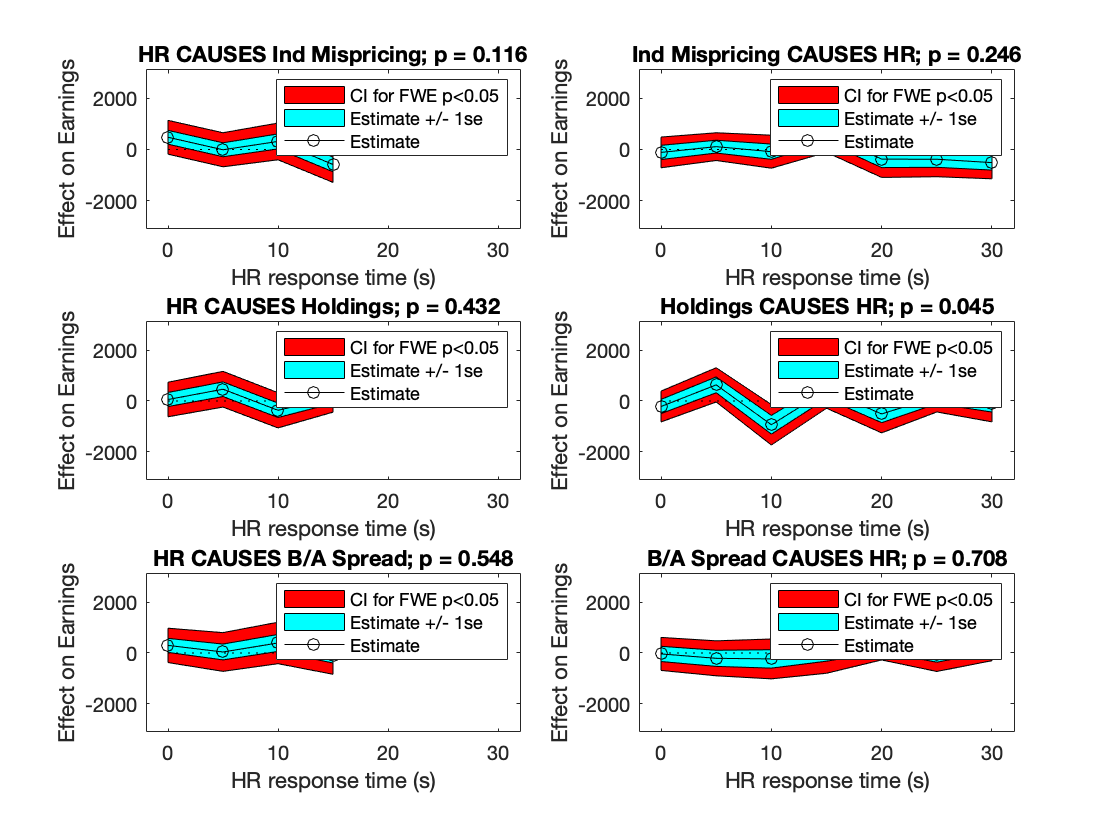

mdl = Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations             123
    Fixed effects coefficients           5
    Random effects coefficients         16
    Covariance parameters                2
    Distribution                    Normal
    Link                            Identity
    FitMethod                       MPL   

Formula:
    Earnings ~ 1 + Granger_0 + Granger_5 + Granger_10 + Granger_15 + (1 | Session)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    2520.2    2539.9    -1253.1          2506.2  

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE        tStat        DF     pValue        Lower      Upper  
    {'(Intercept)'}          24381     845.56       28.834    118    2.9158e-55      22707      26055
    {'Granger_0'  }         477.15     269.27       1.7721    118      0.07896

LRstat =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik     LRStat    deltaDF    pValue 
    mdlR     3     2519.6      2528    -1256.8                                
    mdl      7     2520.2    2539.9    -1253.1    7.3954    4          0.11641


mdl = Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations             123
    Fixed effects coefficients           8
    Random effects coefficients         16
    Covariance parameters                2
    Distribution                    Normal
    Link                            Identity
    FitMethod                       MPL   

Formula:
    Earnings ~ 1 + Granger_0 + Granger_5 + Granger_10 + Granger_15 + Granger_20 + Granger_25 + Granger_30 + (1 | Session)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    2524.5    2552.6    -1252.2          2504.5  

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE        tStat       DF     pValue        Lower      Upper 
    {'(Intercept)'}          23961     664.31       36.07    115    1.5575e-64      22646     25277
    {'Granger_0'  }        -113.69     276.

LRstat =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik     LRStat    deltaDF    pValue 
    mdlR      3    2519.6      2528    -1256.8                                
    mdl      10    2524.5    2552.6    -1252.2    9.0867    7          0.24649


mdl = Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations             123
    Fixed effects coefficients           5
    Random effects coefficients         16
    Covariance parameters                2
    Distribution                    Normal
    Link                            Identity
    FitMethod                       MPL   

Formula:
    Earnings ~ 1 + Granger_0 + Granger_5 + Granger_10 + Granger_15 + (1 | Session)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    2523.7    2543.4    -1254.9          2509.7  

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE        tStat      DF     pValue        Lower      Upper 
    {'(Intercept)'}          24330     764.47     31.826    118    9.5022e-60      22816     25844
    {'Granger_0'  }         58.631      276.5    0.21205    118       0.83244    -48

LRstat =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik     LRStat    deltaDF    pValue 
    mdlR     3     2519.6      2528    -1256.8                                
    mdl      7     2523.7    2543.4    -1254.9    3.8158    4          0.43151


mdl = Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations             123
    Fixed effects coefficients           8
    Random effects coefficients         16
    Covariance parameters                2
    Distribution                    Normal
    Link                            Identity
    FitMethod                       MPL   

Formula:
    Earnings ~ 1 + Granger_0 + Granger_5 + Granger_10 + Granger_15 + Granger_20 + Granger_25 + Granger_30 + (1 | Session)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    2519.2    2547.3    -1249.6          2499.2  

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE        tStat       DF     pValue        Lower      Upper  
    {'(Intercept)'}          24329     741.31      32.818    115    3.1303e-60      22860      25797
    {'Granger_0'  }        -215.99     27

LRstat =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik     LRStat    deltaDF    pValue  
    mdlR      3    2519.6      2528    -1256.8                                 
    mdl      10    2519.2    2547.3    -1249.6    14.382    7          0.044783


mdl = Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations             123
    Fixed effects coefficients           5
    Random effects coefficients         16
    Covariance parameters                2
    Distribution                    Normal
    Link                            Identity
    FitMethod                       MPL   

Formula:
    Earnings ~ 1 + Granger_0 + Granger_5 + Granger_10 + Granger_15 + (1 | Session)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    2524.5    2544.2    -1255.3          2510.5  

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE        tStat       DF     pValue        Lower      Upper 
    {'(Intercept)'}         24726      776.79      31.831    118    9.3406e-60      23188     26264
    {'Granger_0'  }        299.15       275.2       1.087    118       0.27925    

LRstat =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik     LRStat    deltaDF    pValue 
    mdlR     3     2519.6      2528    -1256.8                                
    mdl      7     2524.5    2544.2    -1255.3    3.0578    4          0.54819


mdl = Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations             123
    Fixed effects coefficients           8
    Random effects coefficients         16
    Covariance parameters                2
    Distribution                    Normal
    Link                            Identity
    FitMethod                       MPL   

Formula:
    Earnings ~ 1 + Granger_0 + Granger_5 + Granger_10 + Granger_15 + Granger_20 + Granger_25 + Granger_30 + (1 | Session)

Model fit statistics:
    AIC     BIC       LogLikelihood    Deviance
    2529    2557.1    -1254.5          2509    

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE        tStat       DF     pValue        Lower      Upper 
    {'(Intercept)'}          24523     755.62      32.454    115    9.9793e-60      23026     26020
    {'Granger_0'  }        -35.877     298.64  

LRstat =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik     LRStat    deltaDF    pValue 
    mdlR      3    2519.6      2528    -1256.8                                
    mdl      10      2529    2557.1    -1254.5    4.6072    7          0.70777


earn = [earn_1to12; earn_21to24];
ColumnPicked = [2 4 10 12 14 16]; % Choose columns to work with from dataset; 
% see CograngerHR_aggregate1to24s**.xlsx for meaning of columns (taking
% into account that only p values and test statistics have been copied into this Matlab
% notebook); the columns picked should correspond to test statistic of Granger
% causality tests of heart rate and the variables of interest
% (Has to be even number)
% For Figure 7, un-comment lines 2041 and 2045 (no differentiation w.r.t.
% MMIP
ColumnName = {'HR CAUSES Ind Mispricing'; 'Ind Mispricing CAUSES HR'
    'HR CAUSES Holdings'; 'Holdings CAUSES HR'
    'HR CAUSES B/A Spread'; 'B/A Spread CAUSES HR'}; % Titles for subplots

seconds = [0, 5, 10, 15, 20, 25, 30]; % , 35, 40, 45, 50];
MaxSec = 15;
part = 1:length(earn); 
earnpart = earn(part);

figure('Name','HB corrections at p=0.05: 0.0083, 0.0100, ...')

for j=1:length(ColumnPicked)
    % Initialize vector of slope estimates
    Slopes = [];
    % Initialize matrix of 80 (90)/95% confidence interval (lower end only)
    Confid90 = [];
    Confid95 = [];
    % Regressor names in GLME modeling
    RegN = ['Earnings ~ 1 + '];
    
    for i=1:length(seconds)
        ds_name = ['hr_p_all_' num2str(seconds(i)) 's'];
        hr_p_all = evalin('base',ds_name);
        scr_p = log([hr_p_all(part,ColumnPicked(j))]+0.0001); 
        % Alternatives: 
        % scr_p = log2([hr_p_all(part,ColumnPicked(j))]+0.0001); 
        % = hr_p_all(part,ColumnPicked); 
        % = log([hr_p_all(part,ColumnPicked)]+0.0001); 
        NewVarN = ['Granger_' num2str(seconds(i))];
        if i == 1
            datatable = array2table([earnpart, scr_p],'VariableNames', {'Earnings',NewVarN});
        else
            datatable = addvars(datatable,scr_p,'NewVariableNames',NewVarN);
        end
        % Comment out ':Treatment' if no conditioning in regression in
        % following. Compare:
        % RegN = [RegN NewVarN ':Treatment + ']; 
        % And:
        % RegN = [RegN NewVarN ' + ']; 
        % Differentiate depending on direction of causality
        if mod(ColumnPicked(j),4) == 0
            %RegN = [RegN NewVarN ':Treatment + '];
            RegN = [RegN NewVarN ' + '];
        else
            if i <= find(seconds == MaxSec)
                %RegN = [RegN NewVarN ':Treatment + '];
                RegN = [RegN NewVarN ' + '];
            end
        end
    end

    % Take session information from last dataset
    sessions = hr_p_all(part,end); 
    sessioncat = categorical(sessions);
    treat = sum(sessions == mmip,2);
    ftreat = find(treat ==1);
    treatcat = categorical(treat);
    datatable = addvars(datatable,sessioncat,'NewVariableNames','Session');
    datatable = addvars(datatable,treatcat,'NewVariableNames','Treatment');

    % First specify a restricted model, then the general model, for a LR
    % test
    modelspec = ['Earnings ~ 1 + (1|Session)'];
    mdlR = fitglme(datatable,modelspec,'Link',"identity",'Distribution',"normal");
    % Now specify and estimate the model we're interested in
    modelspec = [RegN '(1|Session)'];
    mdl = fitglme(datatable,modelspec,'Link',"identity",'Distribution',"normal")
    % Cannot use a:b in {} cell call
    % Differentiate depending on direction of causality
    if mod(ColumnPicked(j),4) == 0
        NPar = length(seconds);
    else
        NPar = find(seconds == MaxSec);
    end
    for i=1:NPar
        Slopes = [Slopes mdl.Coefficients{1+i,2}];
        % Use two-sided critical values (POSITIVE) 1.2815 (1.645 for 90)/1.96
        % (for 97.5% CI use 2.169 - this will do FWE for m=4;
        % for 99.29% CI use 2.45 -- this will do FWE for m=7)
        Confid90 = [Confid90 1.*mdl.Coefficients{1+i,3}]; % Notation may confuse: 
        % this is not 90 percent CI but +/- 1se
        if sum(j == [2 4 6 8 10]) > 0
            Confid95 = [Confid95 2.169.*mdl.Coefficients{1+i,3}];
            ConfidText4m = 'CI for FWE p<0.05'; 
        else
            Confid95 = [Confid95 2.45.*mdl.Coefficients{1+i,3}];
            ConfidText7m = 'CI for FWE p<0.05';
        end
    end
    % Report the LR statistic
    LRstat = compare(mdlR,mdl)

    % Slopes
    subplot(length(ColumnPicked)./2,2,j)
    xconf = [seconds(1:NPar) seconds(NPar:-1:1)];
    yconf = [(Slopes+Confid95) (Slopes(end:-1:1)-Confid95(end:-1:1))];
    fill(xconf,yconf,'red');
    hold on;
    yconf = [(Slopes+Confid90) (Slopes(end:-1:1)-Confid90(end:-1:1))];
    fill(xconf,yconf,'cyan');
    plot(seconds(1:NPar), Slopes,'-ok');
    zeroline = zeros(1,length(seconds));
    plot(seconds,zeroline,':k');
    axis([-2 32 -3100 3100])
    formatSpec = '%.3f';
    if j == 1 | j == 4
        % title([ColumnName{j} '; p = ' num2str(LRstat{2,8},formatSpec) ...
        %    '  (FWE p < 0.05)'])
        title([ColumnName{j} '; p = ' num2str(LRstat{2,8},formatSpec)])
    else
        title([ColumnName{j} '; p = ' num2str(LRstat{2,8},formatSpec)])
    end
    if sum(j == [2 4 6 8 10]) > 0
        legend(ConfidText4m,'Estimate +/- 1se','Estimate');
    else
        legend(ConfidText7m,'Estimate +/- 1se','Estimate');
    end
    xlabel('HR response time (s)')
    ylabel('Effect on Earnings')
    hold off
    
end